# **Comprehensive SCME method**

***V1.0.0***

This work implements the comprehensive energy method based on the smooth curvature model (CoSCME) for modeling the nonlinear large deformation behavior of planar compliant mechanisms. The CoSCME extends the original high order SCME method by incorporating both bending deformation and axial deformation and explicitly accounts for the coupling between these two deformation modes.

This code is based on the paper *“Comprehensive SCME: A nonlinear large-deformation modeling approach for planar compliant mechanisms”* (DOI: 10.1016/j.mechmachtheory.2025.106070), published in *Mechanism and Machine Theory*. The code is publicly released for unrestricted use without prior permission from the authors. Proper citation of the above paper is required for any use in scientific publications. For questions or further information, please contact Dr. Tinghao Liu (Antoine.Tinghao@gmail.com) or Prof. Guangbo Hao (G.Hao@ucc.ie).

Acknowledgements are given to Prof. Fulei Ma (Xidian University), Dr. Guillaume Lods (EPFL), and Prof. Simon Henein (EPFL) for their contributions to testing the code and providing valuable suggestions.

This code implements all case studies presented in the manuscript, including:

-  Compresural beams;

-  Tensural beams;

-  Large deformation compliant bistable mechanisms;

-  General lumped-compliance beams;

-  Initially curved beams.

Software Requirements (MATLAB Version):

- Minimum: MATLAB R2020b (64-bit)

- Recommended: MATLAB R2022a or later

Hardware Requirements: 

- Minimum Configuration:

- CPU: Intel i5 / AMD Ryzen 5 (4 cores, ≥ 2.5 GHz)

- RAM: 8 GB

- Storage: 5 GB available disk space

- Recommended Configuration:

- CPU: Intel i7 / AMD Ryzen 7 (8 cores, high single-core frequency ≥ 3.5 GHz)

- RAM: 16–32 GB

- SSD storage recommended

The following MATLAB toolboxes are required for execution:

- Optimization Toolbox

- Symbolic Math Toolbox 

## ** Main Programme **

## **0. Initialization**

clear
clc
warning off

% Define geometric properties
L = 100*10^-3  ;     % Beam Length (m) [Straight beam as example]
W = 10*10^-3   ;     % Beam width (m)
T = 0.6*10^-3  ;     % Beam thickness (m)

% Define Material properties
E = 2800*10^6  ;     % Young's modulus (N/m^2)
I = W*(T^3)/12 ;     % Beam secend area moment of inertia
A = W*T        ;     % Beam section area

%Collect geometric and material properties of slender beam
BeamProperty = [L,W,T,E,I,A];

%Initial guess of solution vector (alpha*6,beta*6)
SolutionVector_InitialGuess = zeros(1,12)  ;

%Initialize matrix of solution vector
SolutionVector = SolutionVector_InitialGuess;

%Constraint conditions in the optimization formulation
A = [];
b = [];
Aeq = [];
beq = [];
lb = [];
ub = [];

%Optimization settings
options = optimset( ...
    'Display','off', ...
    'Algorithm','interior-point', ... % Specify optimization algorithm
    'TolX',1e-10, ...        % Setup step tolerance
    'TolFun',1e-10, ...      % Setup optimality tolerance
    'TolCon',1e-12, ...      % Setup constraint tolerance
    'MaxFunEvals',1e6);      % Setup Max function evaluations


Progress = 0;

## **1. Compresural beams**

This section implements the modeling of compresural beams under large deformation, where the beam undergoes geometric nonlinearity under compressive loading.  

#### **1.1 Fixed-fixed beam**

% Case study indicator for adjusting constraint condition
CaseStudy = 11;
% Set displacement along -x direction (mm)
Delta_x = 40e-3;
% Total number of steps
Nt =41;

% Artificial offset is introduced to trigger buckling
% without affecting the postbuckling response.
Artificial_offset = -0.0001;
Xt   = L-Delta_x*linspace(0,1,Nt)';
Yt   =  0*linspace(0,1,Nt)';
Phit =  Artificial_offset + 0*linspace(0,1,Nt)';

Tip_trajectory = [Xt, Yt, Phit];

% Define objective function
SolutionVectorHistory = SolutionVector_InitialGuess;
SolutionVector_Previous = SolutionVector_InitialGuess;
Energy = @(SolutionVector) StrainEnergy(SolutionVector,SolutionVector_Previous,BeamProperty);

fprintf('Case Study 1.1 -- Step Number:');

Case Study 1.1 -- Step Number:

for i = 1:Nt
% Current step number
i

% Nonlinear constraint function updated iteratively
nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory(i,:),CaseStudy);

% Solve
[x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVector, A, b, Aeq, beq, lb, ub, nonlcon, options);

% Update for next step (same role as P0 = x_min in your old code)
SolutionVector = x_min;
SolutionVector_Previous = x_min;

% Record
SolutionVectorHistory(i,:) = x_min;
StrainEnergyHistory(i)     = fval;
Lam(i,:)                  = lambda.eqnonlin(:).';
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41



fprintf('========================================================\n');

fprintf('Case Study 1.1: Fixed-fixed beam under compresural load');

Case Study 1.1: Fixed-fixed beam under compresural load

fprintf('========================================================\n');

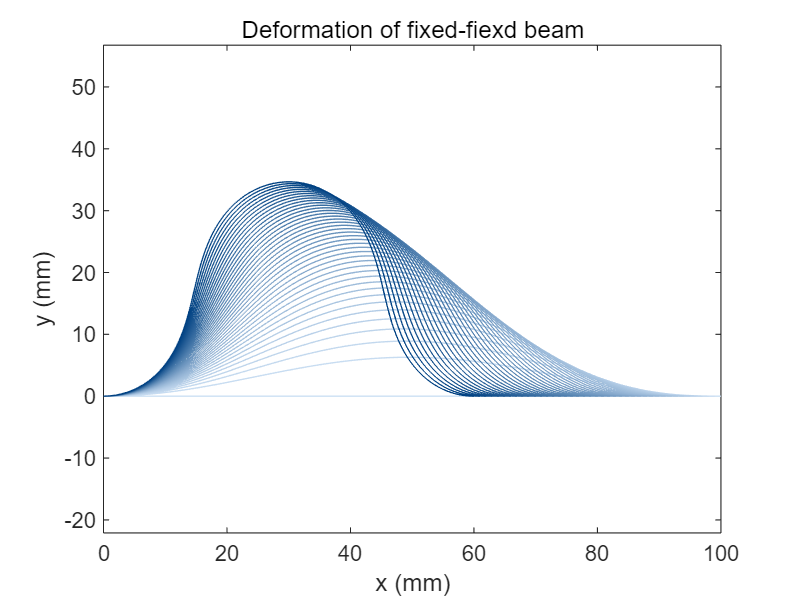


% Plot deformation
for i=1:Nt
PlotDeformation(SolutionVectorHistory(i,:),BeamProperty,i,Nt,CaseStudy);
axis equal
hold on
xlabel('x (mm)');
ylabel('y (mm)' );
title('Deformation of fixed-fiexd beam');
end
hold off

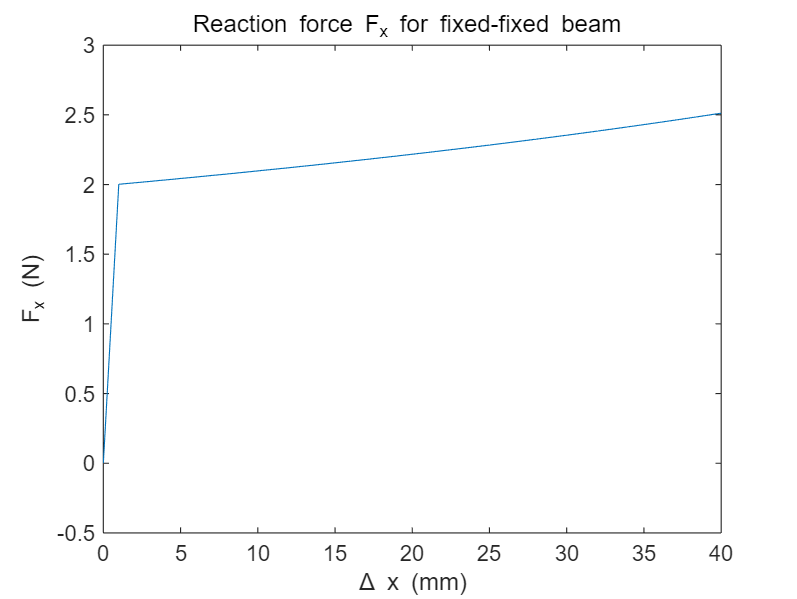


% Plot force-displacement relationship
plot(Delta_x*1000*linspace(0,1,Nt),Lam(:,1))
xlabel('\Delta x (mm)');
ylabel('F_x (N)' );
title('Reaction force F_x for fixed-fixed beam ' );

#### **1.2 Fixed-pined beam**

clear CaseStudy Delta_x Xt Yt Phit Nt Tip_trajectory SolutionVectorHistory SolutionVector_Previous StrainEnergyHistory Lam

% Case study indicator for adjusting constraint condition
CaseStudy = 12;

% Set displacement along -x direction (mm)
Delta_x = 40e-3;
% Total number of steps
Nt =41;

% Artificial offset is introduced to trigger buckling
% without affecting the postbuckling response.
Artificial_offset = -1e-6;
Xt   = L-Delta_x*linspace(0,1,Nt)';
Yt   = Artificial_offset+ 0*linspace(0,1,Nt)';

Tip_trajectory = [Xt, Yt];

% Define objective function
SolutionVectorHistory = SolutionVector_InitialGuess;
SolutionVector_Previous = SolutionVector_InitialGuess;
Energy = @(SolutionVector) StrainEnergy(SolutionVector,SolutionVector_Previous,BeamProperty);
fprintf('Case Study 1.2 -- Step Number:');

Case Study 1.2 -- Step Number:

for i = 1:Nt
% Current step number
i 
% Nonlinear constraint function updated iteratively
nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory(i,:),CaseStudy);

% Solve
[x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVector, A, b, Aeq, beq, lb, ub, nonlcon, options);

% Update for next step (same role as P0 = x_min in your old code)
SolutionVector = x_min;
SolutionVector_Previous = x_min;

% Record
SolutionVectorHistory(i,:) = x_min;
StrainEnergyHistory(i)     = fval;
Lam(i,:)                  = lambda.eqnonlin(:).';
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41


fprintf('========================================================\n');

fprintf('Case Study 1.2: Fixed-pined beam under compresural load');

Case Study 1.2: Fixed-pined beam under compresural load

fprintf('========================================================\n');

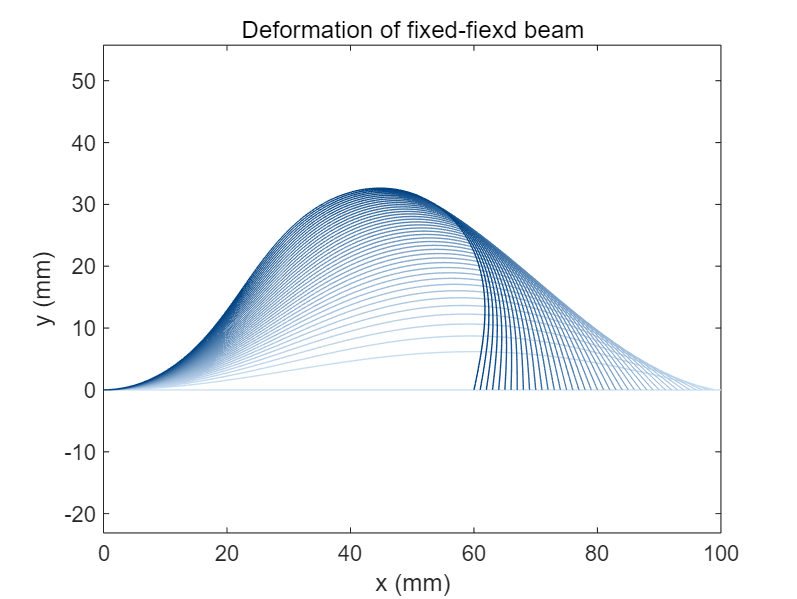


% Plot deformation
for i=1:Nt
PlotDeformation(SolutionVectorHistory(i,:),BeamProperty,i,Nt,CaseStudy);
axis equal
hold on
xlabel('x (mm)');
ylabel('y (mm)' );
title('Deformation of fixed-fiexd beam');
end
hold off

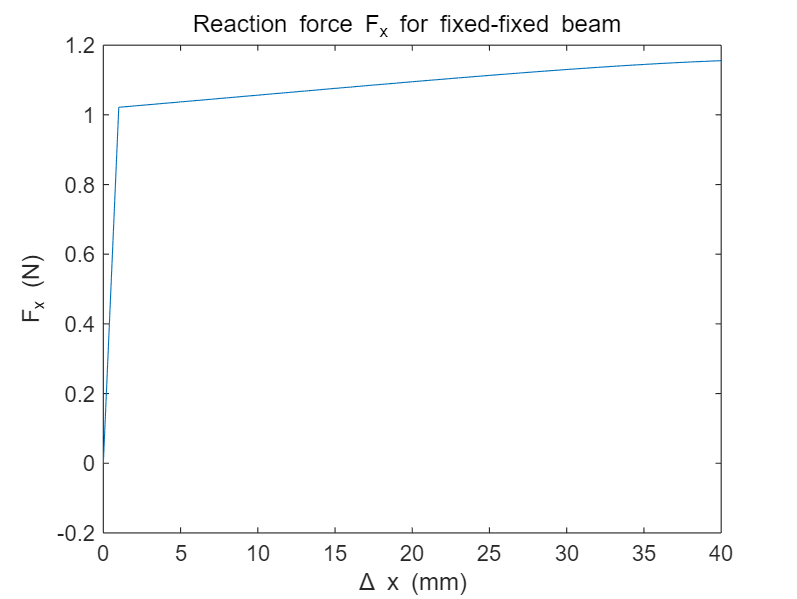


% Plot force-displacement relationship
plot(Delta_x*1000*linspace(0,1,Nt),Lam(:,1))
xlabel('\Delta x (mm)');
ylabel('F_x (N)' );
title('Reaction force F_x for fixed-fixed beam ' );

## **2. Tensural beams**

This section implements the modeling of tensural beams, where the beam undergoes geometric nonlinearity under tensile loading.

#### **2.1 Basic parallelogram mechanisms (BPMs)**

clear CaseStudy Delta_x Delta_y Xt Yt Phit Nt Tip_trajectory SolutionVectorHistory SolutionVector_Previous StrainEnergyHistory Lam

% Case study indicator for adjusting constraint condition
CaseStudy = 21;

% Set displacement along -x direction (mm)
Delta_y = 40e-3;

% Total number of steps
Nt =41;

% Derive tip trajectory points
Yt   = -Delta_y*linspace(0,1,Nt)';
Phit = 0*linspace(0,1,Nt)';

Tip_trajectory = [Yt, Phit];

% Define objective function
SolutionVectorHistory = SolutionVector_InitialGuess;
SolutionVector_Previous = SolutionVector_InitialGuess;
Energy = @(SolutionVector) StrainEnergy(SolutionVector,SolutionVector_Previous,BeamProperty);
fprintf('Case Study 2.1 -- Step Number:');

Case Study 2.1 -- Step Number:

for i = 1:Nt
% Current step number
i 
% Nonlinear constraint function updated iteratively
nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory(i,:),CaseStudy);

% Solve
[x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVector, A, b, Aeq, beq, lb, ub, nonlcon, options);

% Update for next step (same role as P0 = x_min in your old code)
SolutionVector = x_min;
SolutionVector_Previous = x_min;

% Record
SolutionVectorHistory(i,:) = x_min;
StrainEnergyHistory(i)     = fval;
Lam(i,:)                  = lambda.eqnonlin(:).';
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41


fprintf('========================================================\n');

fprintf('Case Study 2.1: Basic parallelogram mechanisms');

Case Study 2.1: Basic parallelogram mechanisms

fprintf('========================================================\n');

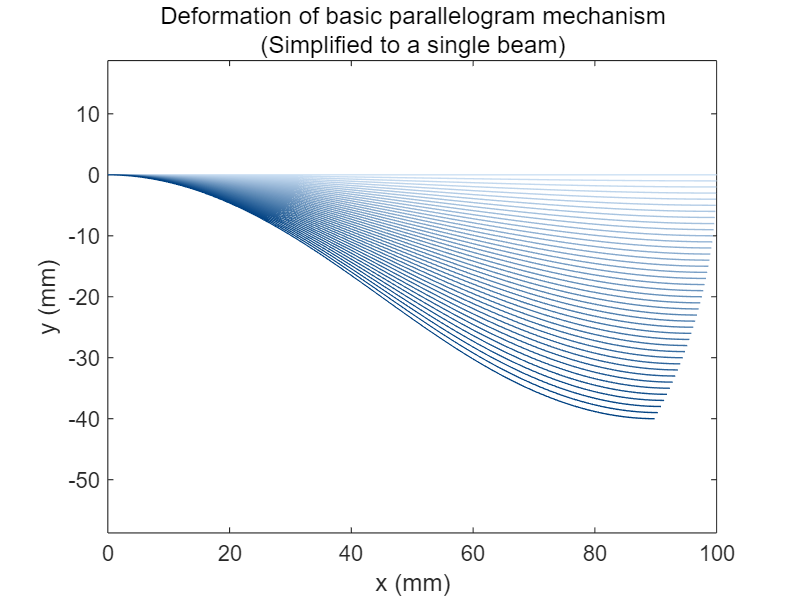


% Plot deformation
for i=1:Nt
[Points,MaxStress(i,:)]=PlotDeformation(SolutionVectorHistory(i,:),BeamProperty,i,Nt,CaseStudy);
axis equal
hold on
xlabel('x (mm)');
ylabel('y (mm)' );
title('Deformation of basic parallelogram mechanism');
subtitle('(Simplified to a single beam)')
X_tip_position(i,:) = Points(end,1);
end
hold off

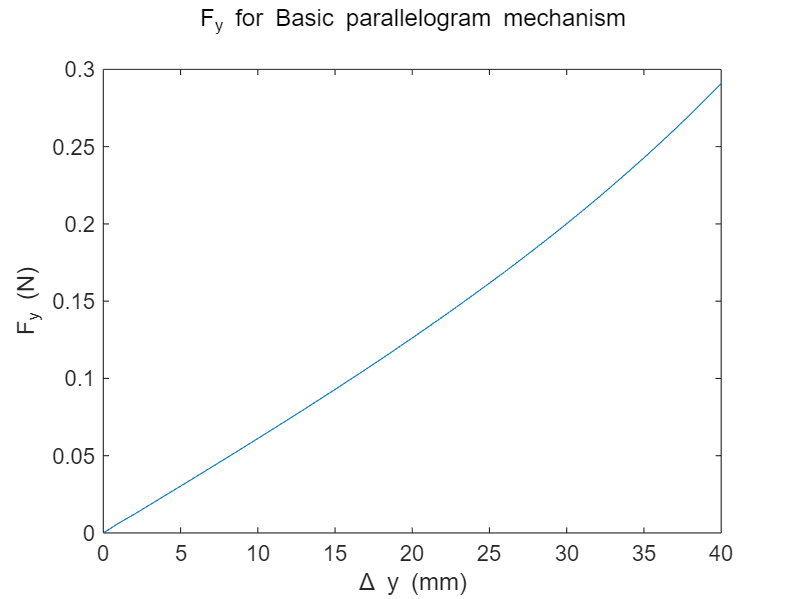


% Plot force-displacement relationship
% Please note: If the force–displacement curve is plotted for the entire mechanism, the result should be multiplied by 2.
plot(Delta_y*1000*linspace(0,1,Nt),Lam(:,1))
xlabel('\Delta y (mm)');
ylabel('F_y (N)' );
title('F_y for Basic parallelogram mechanism');
subtitle(' ')

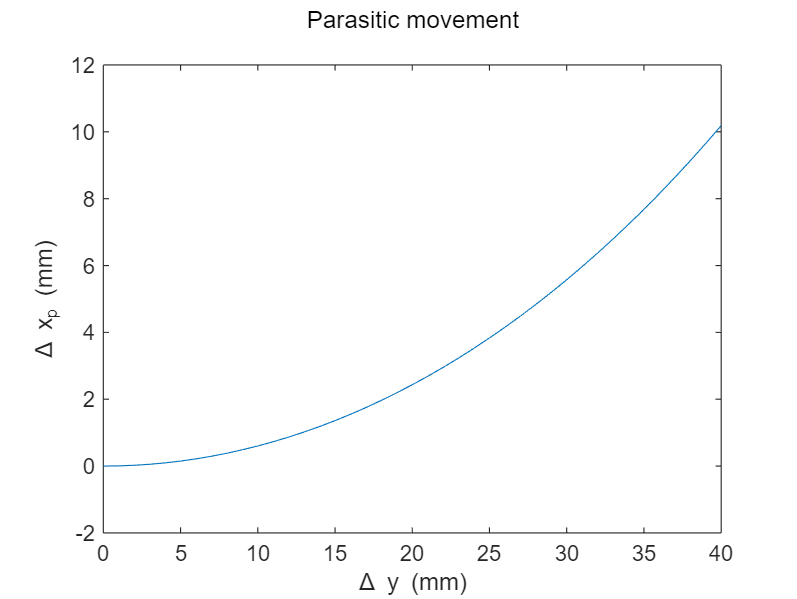


% Plot parasitic movement for center shuttle
plot(Delta_y*1000*linspace(0,1,Nt),1000*L-X_tip_position)
xlabel('\Delta y (mm)');
ylabel('\Delta x_p (mm)' );
title('Parasitic movement');
subtitle(' ')

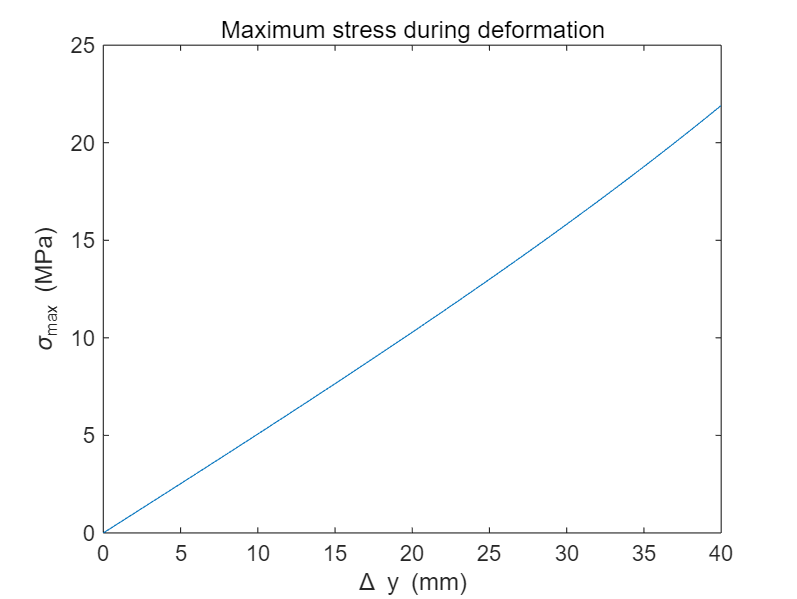


% Plot maximum stress during deformation
plot(Delta_y*1000*linspace(0,1,Nt),MaxStress/1e6)
xlabel('\Delta y (mm)');
ylabel('\sigma_{max} (MPa)' );
title('Maximum stress during deformation');

#### **2.2 Compound basic parallelogram mechanisms (CBPMs)**

clear CaseStudy Delta_x Delta_y Xt Yt Phit Nt Tip_trajectory SolutionVectorHistory SolutionVector_Previous StrainEnergyHistory Lam

% Case study indicator for adjusting constraint condition
CaseStudy = 22;

% Set displacement along -x direction (mm)
Delta_y = 10e-3;

% Total number of steps
Nt =41;

% Derive tip trajectory points
Xt   = L+0*linspace(0,1,Nt)';
Yt   = -Delta_y*linspace(0,1,Nt)';
Phit = 0*linspace(0,1,Nt)';

Tip_trajectory = [Xt,Yt,Phit];

% Define objective function
SolutionVectorHistory = SolutionVector_InitialGuess;
SolutionVector_Previous = SolutionVector_InitialGuess;
Energy = @(SolutionVector) StrainEnergy(SolutionVector,SolutionVector_Previous,BeamProperty);
fprintf('Case Study 2.2 -- Step Number:');

Case Study 2.2 -- Step Number:

for i = 1:Nt
% Current step number
i 
% Nonlinear constraint function updated iteratively
nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory(i,:),CaseStudy);

% Solve
[x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVector, A, b, Aeq, beq, lb, ub, nonlcon, options);

% Update for next step (same role as P0 = x_min in your old code)
SolutionVector = x_min;
SolutionVector_Previous = x_min;

% Record
SolutionVectorHistory(i,:) = x_min;
StrainEnergyHistory(i)     = fval;
Lam(i,:)                  = lambda.eqnonlin(:).';
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41


fprintf('========================================================\n');

fprintf('Case Study 2.2: Compound basic parallelogram mechanisms');

Case Study 2.2: Compound basic parallelogram mechanisms

fprintf('========================================================\n');

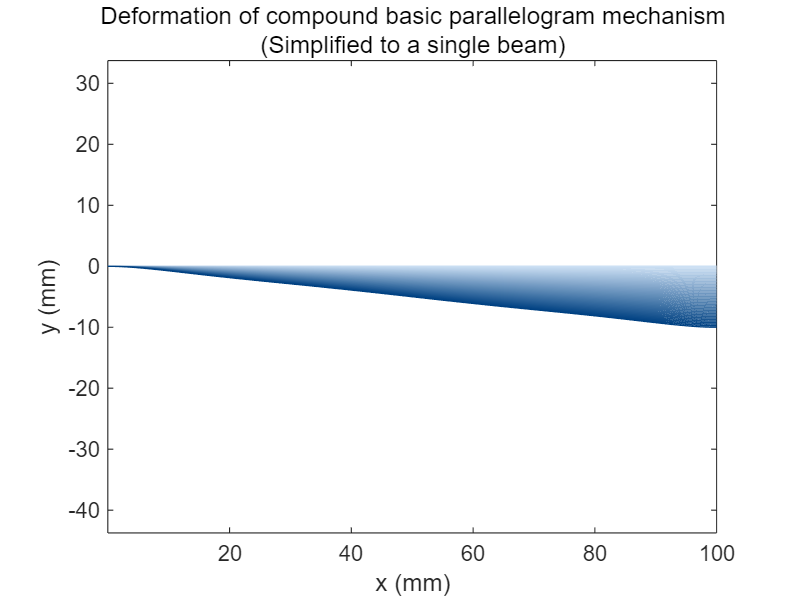


% Plot deformation
for i=1:Nt
[Points,MaxStress(i,:)]=PlotDeformation(SolutionVectorHistory(i,:),BeamProperty,i,Nt,CaseStudy);
axis equal
hold on
xlabel('x (mm)');
ylabel('y (mm)' );
title('Deformation of compound basic parallelogram mechanism');
subtitle('(Simplified to a single beam)')
X_tip_position(i,:) = Points(end,1);
end
hold off

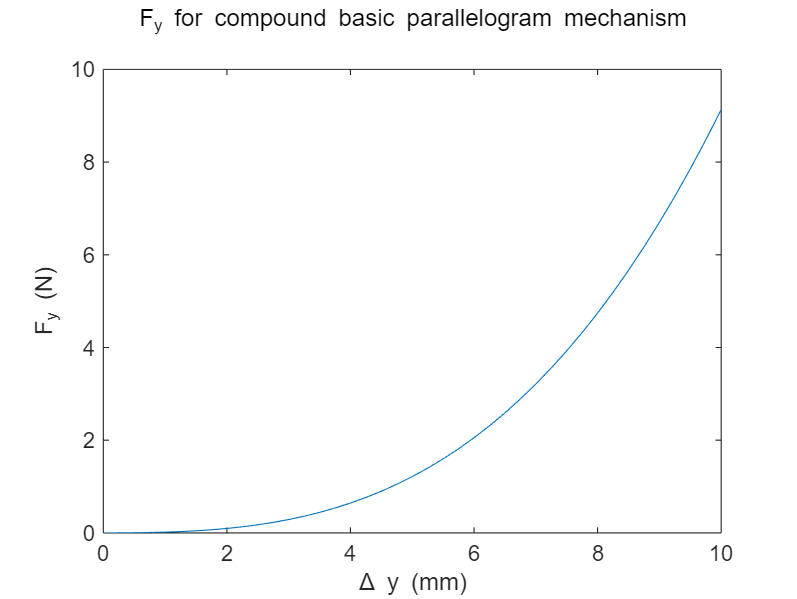



% Plot force-displacement relationship
% Please note: If the force–displacement curve is plotted for the entire mechanism,
% the result should be multiplied by 4.
plot(Delta_y*1000*linspace(0,1,Nt),Lam(:,2))
xlabel('\Delta y (mm)');
ylabel('F_y (N)' );
title('F_y for compound basic parallelogram mechanism');
subtitle(' ')

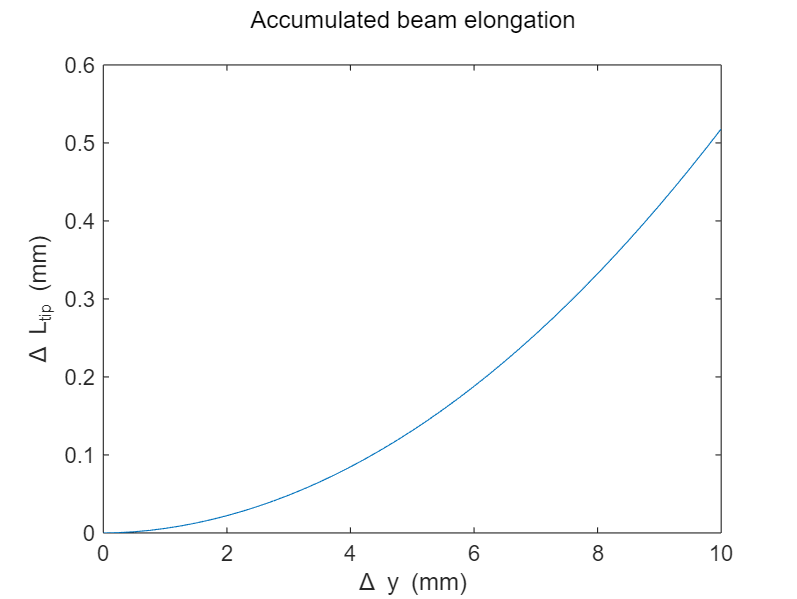



% Plot beam elongation (Axial strain tip = B0*L)
plot(Delta_y*1000*linspace(0,1,Nt),L*1000*SolutionVectorHistory(:,7))
xlabel('\Delta y (mm)');
ylabel('\Delta L_{tip} (mm)' );
title('Accumulated beam elongation');
subtitle(' ')

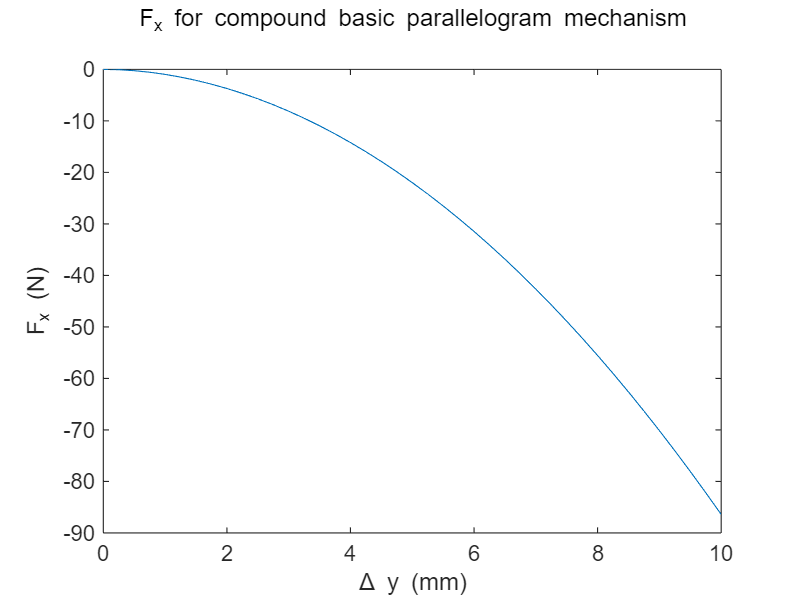




% Plot force-displacement relationship
plot(Delta_y*1000*linspace(0,1,Nt),Lam(:,1))
xlabel('\Delta y (mm)');
ylabel('F_x (N)' );
title('F_x for compound basic parallelogram mechanism');
subtitle(' ')

## **3. Compliant bistable mechansims**

This section implements the modeling of compliant bistable mechanism, including conventional translational bistable mechanism and preloaded rotational bistable mechanism. 

#### **3.1 Translational bistable mechanism**

clear CaseStudy Delta_x Delta_y Xt Yt Phit Nt Tip_trajectory SolutionVectorHistory SolutionVector_Previous StrainEnergyHistory Lam

% Case study indicator for adjusting constraint condition + Inclined angle
% (CaseStudy is 3-1; Inclined angle is 40 degree)
CaseStudy = [31,40];
InclinedAngle = deg2rad(CaseStudy(2));
% Set displacement along -x direction (mm)
Delta_y = 110e-3;

% Total number of steps
Nt =41;

% Derive tip trajectory points
Xt   = L-Delta_y*sin(InclinedAngle)*linspace(0,1,Nt)';
Yt   = -Delta_y*cos(InclinedAngle)*linspace(0,1,Nt)';
Phit = 0*linspace(0,1,Nt)';


Tip_trajectory = [Xt,Yt,Phit];

% Define objective function
SolutionVectorHistory = SolutionVector_InitialGuess;
SolutionVector_Previous = SolutionVector_InitialGuess;
Energy = @(SolutionVector) StrainEnergy(SolutionVector,SolutionVector_Previous,BeamProperty);
fprintf('Case Study 3.1 -- Step Number:');

Case Study 3.1 -- Step Number:

for i = 1:Nt
% Current step number
i 
% Nonlinear constraint function updated iteratively
nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory(i,:),CaseStudy);

% Solve
[x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVector, A, b, Aeq, beq, lb, ub, nonlcon, options);

% Update for next step (same role as P0 = x_min in your old code)
SolutionVector = x_min;
SolutionVector_Previous = x_min;

% Record
SolutionVectorHistory(i,:) = x_min;
StrainEnergyHistory(i)     = fval;
Lam(i,:)                  = lambda.eqnonlin(:).';
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41


fprintf('========================================================\n');

fprintf('Case Study 3.1: Translational bistable mechanism');

Case Study 3.1: Translational bistable mechanism

fprintf('========================================================\n');

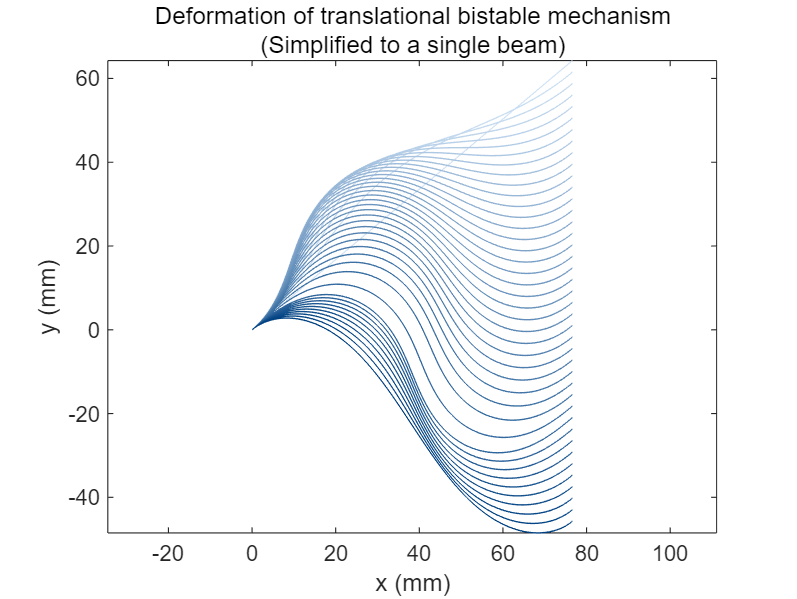


% Plot deformation
for i=1:Nt
[Points,MaxStress(i,:)]=PlotDeformation(SolutionVectorHistory(i,:),BeamProperty,i,Nt,CaseStudy);
axis equal
hold on
xlabel('x (mm)');
ylabel('y (mm)' );
title('Deformation of translational bistable mechanism');
subtitle('(Simplified to a single beam)')
X_tip_position(i,:) = Points(end,1);
end
hold off

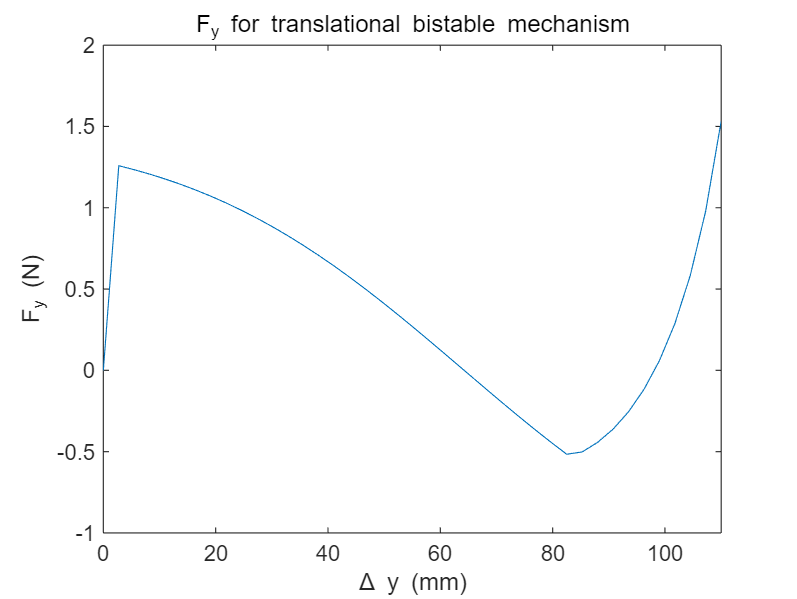



% Plot force-displacement relationship

% Please note: If the force–displacement curve is plotted for the entire mechanism,
% the result should be multiplied by 2.
% Forces in local coordinate system must be transformed into global
% coordinate system using Eq. (22) and (23) in manuscript
plot(Delta_y*1000*linspace(0,1,Nt),Lam(:,1)*sin(InclinedAngle)+Lam(:,2)*cos(InclinedAngle))
xlabel('\Delta y (mm)');
ylabel('F_y (N)' );
xlim([0,Delta_y*1000])
title('F_y for translational bistable mechanism');

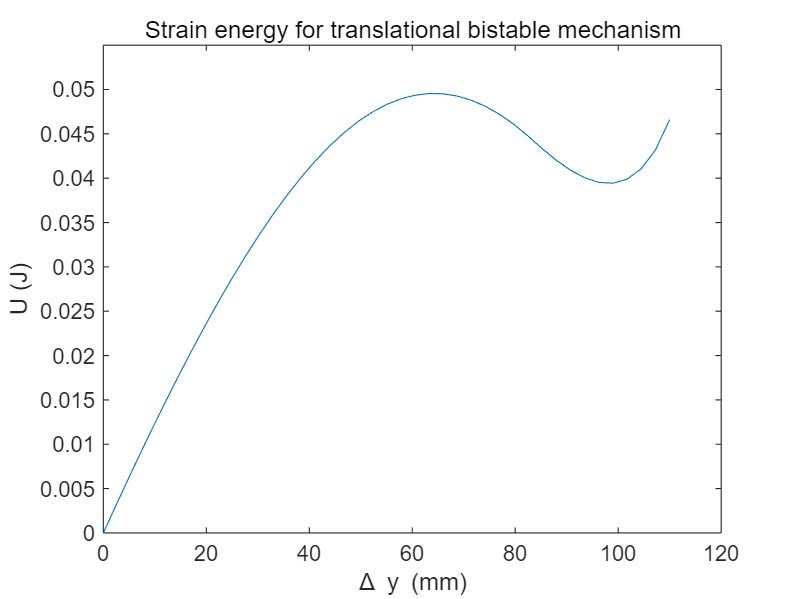




% Plot energy-displacement relationship

% Please note: If the energy–displacement curve is plotted for the entire mechanism,
% the result should be multiplied by 2.
 for i=1:Nt
 Energy_History(i,:) = StrainEnergy_Current(SolutionVectorHistory(i,:),BeamProperty,CaseStudy);
 end

plot(Delta_y*1000*linspace(0,1,Nt),Energy_History)
xlabel('\Delta y (mm)');
ylabel('U (J)' );
ylim([0,0.055])
title('Strain energy for translational bistable mechanism');

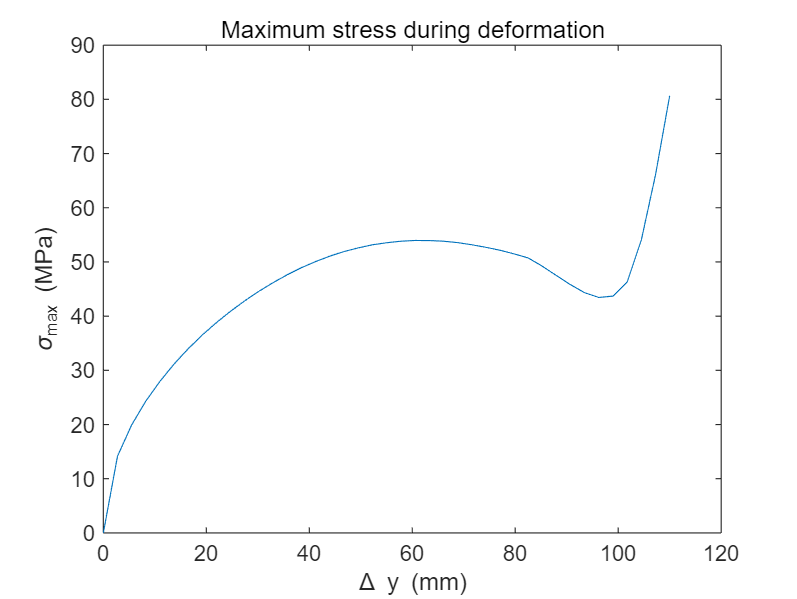


% Plot maximum stress during deformation
plot(Delta_y*1000*linspace(0,1,Nt),MaxStress/1e6)
xlabel('\Delta y (mm)');
ylabel('\sigma_{max} (MPa)' );
title('Maximum stress during deformation');

#### **3.2 Preloaded rotational bistable mechanism**

clear CaseStudy InclinedAngle Delta_x Delta_y Xt Yt Phit Nt Tip_trajectory SolutionVectorHistory SolutionVector_Previous StrainEnergyHistory Lam

% Case study indicator for adjusting constraint condition + Inclined angle
% + Rotational angle + Indicator for left/right beam
% CaseStudy is 3-2;
% Inclined angle is 20 degree;
% Indicator: 1 for left beam and 2 for right beam)
CaseStudy = [32,20,45];

InclinedAngleLeft = deg2rad(CaseStudy(2));
InclinedAngleRight = deg2rad(180-CaseStudy(2));
RotationalAngleLeft = deg2rad(CaseStudy(3));
RotationalAngleRight = deg2rad(CaseStudy(3));

% Set displacement along -y direction (mm)
Delta_y = 25e-3;

% Total number of steps
Nt =51;

%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%  For left beam  %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%

% Derive tip trajectory points for left beam
Xt_PreloadLeft   = L-Delta_y*sin(InclinedAngleLeft)*linspace(0,1,Nt)';
Yt_PreloadLeft   = -Delta_y*cos(InclinedAngleLeft)*linspace(0,1,Nt)';
Phit_PreloadLeft = 0*linspace(0,1,Nt)';

% Preloaded tip trajectory points
Tip_trajectory_preloadLeft = [Xt_PreloadLeft,Yt_PreloadLeft,Phit_PreloadLeft];

% Overall tip trajectory points
Tip_trajectory_Left = [Tip_trajectory_preloadLeft; [Xt_PreloadLeft(end)*ones(Nt,1), Yt_PreloadLeft(end)*ones(Nt,1), Phit_PreloadLeft(end) + RotationalAngleLeft*linspace(0,1,Nt)'] ];

% Define objective function
SolutionVectorHistoryLeft = SolutionVector_InitialGuess;
SolutionVector_PreviousLeft = SolutionVector_InitialGuess;
Energy = @(SolutionVectorLeft) StrainEnergy(SolutionVectorLeft,SolutionVector_PreviousLeft,BeamProperty);
SolutionVectorLeft = [-0.5, zeros(1,11)];

fprintf('Case Study 3.2 (Left beam) -- Step Number:');

Case Study 3.2 (Left beam) -- Step Number:

% Start iteration for left beam
for i = 1:2*Nt
    % Current step number
    i 
    % Nonlinear constraint function updated iteratively
    nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory_Left(i,:),CaseStudy);

    % Solve
    [x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVectorLeft, A, b, Aeq, beq, lb, ub, nonlcon, options);

    % Update for next step (same role as P0 = x_min in your old code)
    SolutionVectorLeft = x_min;
    SolutionVector_PreviousLeft = x_min;

    % Record
    SolutionVectorHistoryLeft(i,:) = x_min;
    StrainEnergyHistoryLeft(i)     = fval;
    LamLeft(i,:)                   = lambda.eqnonlin(:).';
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102



%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%  For right beam  %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%


% Derive tip trajectory points for left beam
Xt_PreloadRight   = L-Delta_y*sin(InclinedAngleRight)*linspace(0,1,Nt)';
Yt_PreloadRight   = -Delta_y*cos(InclinedAngleRight)*linspace(0,1,Nt)';
Phit_PreloadRight = 0*linspace(0,1,Nt)';

% Preloaded tip trajectory points
Tip_trajectory_preloadRight = [Xt_PreloadRight,Yt_PreloadRight,Phit_PreloadRight];

% Overall tip trajectory points
Tip_trajectory_Right = [Tip_trajectory_preloadRight; [Xt_PreloadRight(end)*ones(Nt,1), Yt_PreloadRight(end)*ones(Nt,1), Phit_PreloadRight(end) + RotationalAngleRight*linspace(0,1,Nt)'] ];

% Define objective function
SolutionVectorHistoryRight = SolutionVector_InitialGuess;
SolutionVector_PreviousRight = SolutionVector_InitialGuess;
SolutionVectorRight = [-0.5, zeros(1,11)];
Energy = @(SolutionVectorRight) StrainEnergy(SolutionVectorRight,SolutionVector_PreviousRight,BeamProperty);
fprintf('Case Study 3.2 (Right beam) -- Step Number:');

Case Study 3.2 (Right beam) -- Step Number:

% Start iteration for right beam
for i = 1:2*Nt
    % Current step number
    i 
    % Nonlinear constraint function updated iteratively
    nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory_Right(i,:),CaseStudy);

    % Solve
    [x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVectorRight, A, b, Aeq, beq, lb, ub, nonlcon, options);

    % Update for next step (same role as P0 = x_min in your old code)
    SolutionVectorRight = x_min;
    SolutionVector_PreviousRight = x_min;

    % Record
    SolutionVectorHistoryRight(i,:) = x_min;
    StrainEnergyHistoryRight(i)     = fval;
    LamRight(i,:)                   = lambda.eqnonlin(:).';
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102


%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%  Post-processing  %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%


fprintf('========================================================\n');

fprintf('Case Study 3.2: Rotational bistable mechanism');

Case Study 3.2: Rotational bistable mechanism

fprintf('========================================================\n');

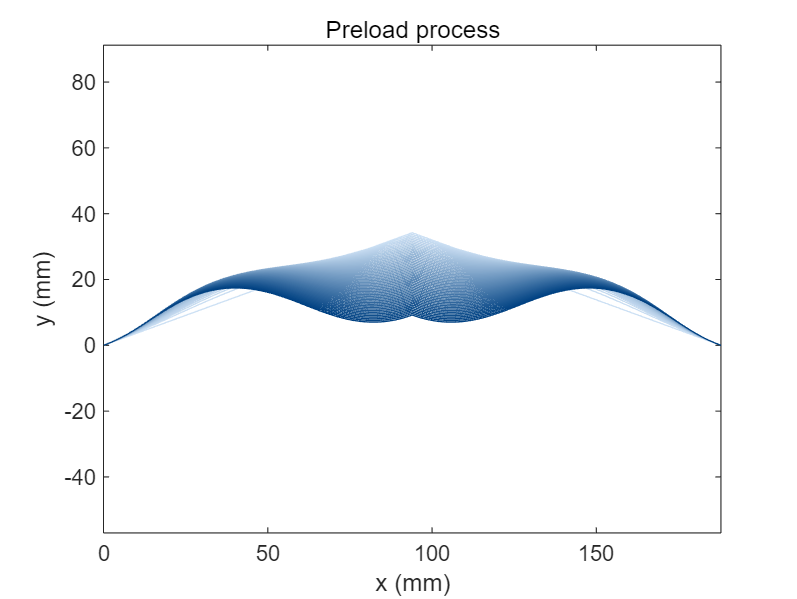


% Plot preload process
for i=1:Nt
    CaseStudy(5) = 1;
    [Points,MaxStress(i,:)]=PlotDeformation(SolutionVectorHistoryLeft(i,:),BeamProperty,i,Nt,CaseStudy);
    hold on
    CaseStudy(5) = 2;
    [Points,MaxStress(i,:)]=PlotDeformation(SolutionVectorHistoryRight(i,:),BeamProperty,i,Nt,CaseStudy);
    axis equal
    xlabel('x (mm)');
    ylabel('y (mm)' );
    title('Preload process');
end
hold off

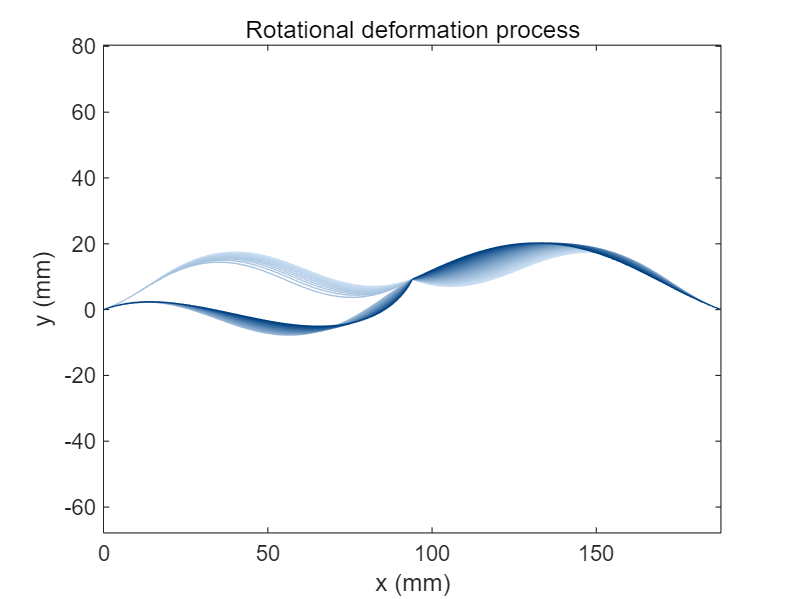



% Plot rotational deformation process
for i=Nt:2*Nt
    CaseStudy(5) = 1;
    [Points,MaxStressLeft(i,:)]=PlotDeformation(SolutionVectorHistoryLeft(i,:),BeamProperty,i,Nt,CaseStudy);
    hold on
    CaseStudy(5) = 2;
    [Points,MaxStressRight(i,:)]=PlotDeformation(SolutionVectorHistoryRight(i,:),BeamProperty,i,Nt,CaseStudy);
    axis equal
    xlabel('x (mm)');
    ylabel('y (mm)' );
    title('Rotational deformation process');
end
hold off

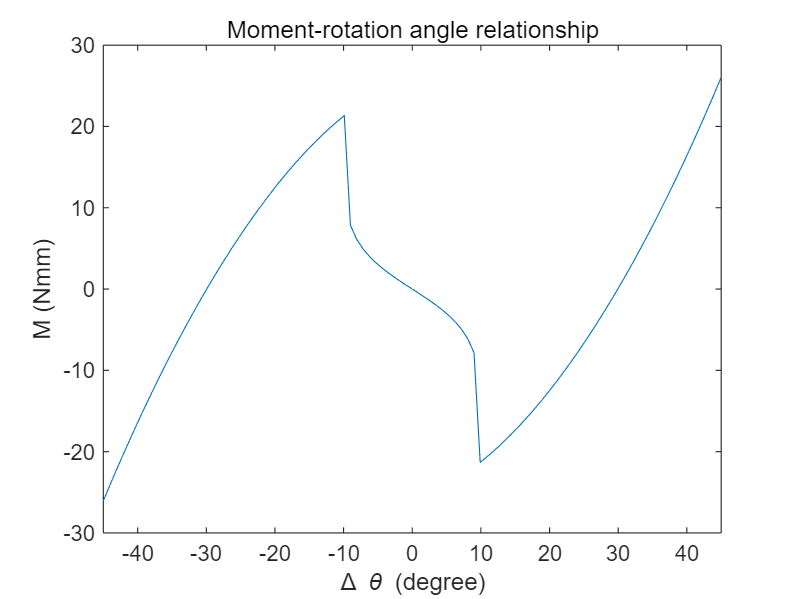




% Plot moment-rotation angle relationship

Angle_total = [linspace(-CaseStudy(3),0,Nt),linspace(0,CaseStudy(3),Nt)];
Moment_total = [flip(1000*(LamLeft(Nt+1:2*Nt,3)+LamRight(Nt+1:2*Nt,3)));-1000*(LamLeft(Nt+1:2*Nt,3)+LamRight(Nt+1:2*Nt,3))];

plot(Angle_total,Moment_total)
xlim([-45,45])
xlabel('\Delta \theta (degree)');
ylabel('M (Nmm)' );
title('Moment-rotation angle relationship');

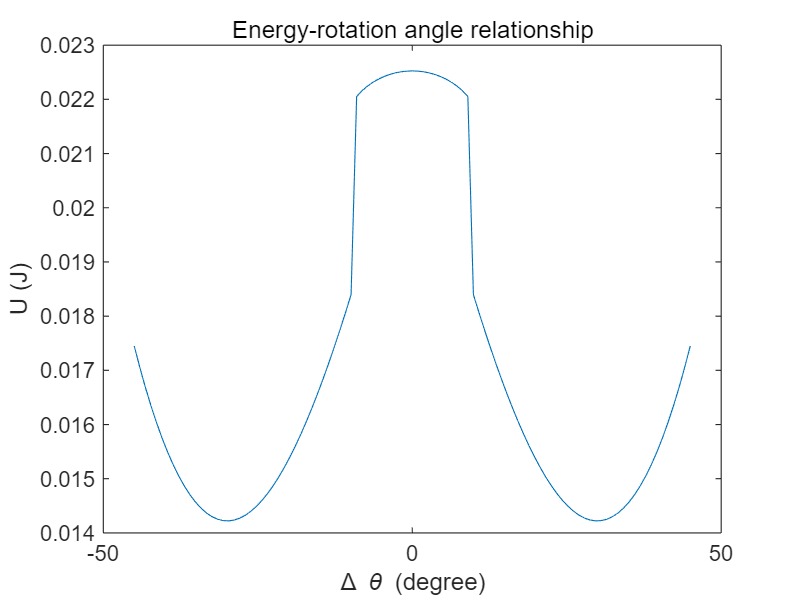






% Plot energy-rotation angle relationship
for i=Nt+1:2*Nt
    Energy_HistoryLeft(i,:)  = StrainEnergy_Current(SolutionVectorHistoryLeft(i,:),BeamProperty,CaseStudy);
    Energy_HistoryRight(i,:) = StrainEnergy_Current(SolutionVectorHistoryRight(i,:),BeamProperty,CaseStudy);
    Energy_History(i-Nt,:) = Energy_HistoryLeft(i,:) + Energy_HistoryRight(i,:);
end

plot(Angle_total,[flip(Energy_History);Energy_History])
xlabel('\Delta \theta (degree)');
ylabel('U (J)' );
title('Energy-rotation angle relationship');

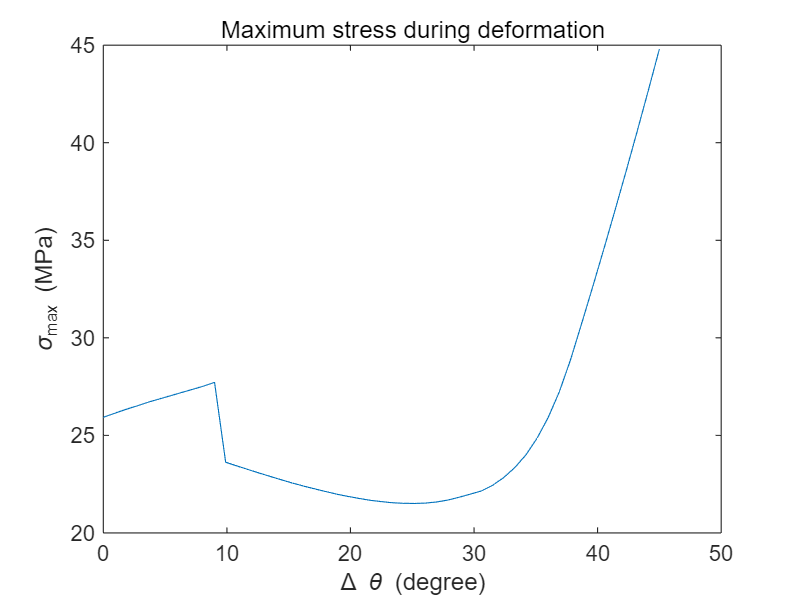


% Plot stress-rotation angle relationship 
plot(linspace(0,CaseStudy(3),Nt), max(MaxStressLeft(Nt+1:2*Nt), MaxStressRight(Nt+1:2*Nt))/1e6)
xlabel('\Delta \theta (degree)');
ylabel('\sigma_{max} (MPa)' );
title('Maximum stress during deformation');

## **4. General lumped-compliance beam**

This section implements the modeling of general lumped-compliance beam, which composed of two serial connected beam with lumped-compliance.  

clear CaseStudy Delta_x Delta_y Xt Yt Phit Nt Tip_trajectory SolutionVectorHistory Initial_SolutionVector SolutionVector_Previous StrainEnergyHistory Lam Energy_History SolutionVector

% Case study indicator for adjusting constraint condition
CaseStudy = 4;

% Set target displacements (mm)
Delta_x = -30e-3;            %Negative direction of x axis
Delta_y = -120e-3;           %Negative direction of y axis
Delta_theta = deg2rad(-45);  %Clockwise direction

% Set frame parameters (mm)
Frame_x = 50*cos(deg2rad(22.5)) /1000;
Frame_y = 50*sin(deg2rad(22.5)) /1000;
Frame_Angle=deg2rad(45);

FrameParameter = [Frame_x,Frame_y,Frame_Angle];


% Total number of steps
Nt =41;

% Derive the tip trajectory points. Please note that the two beams are set to
% have the same length. If further modifications are required to allow
% beams of different lengths, the user can adjust the implementation accordingly.

% Derive tip trajectory points 
Xt   = L + Frame_x + L*cos(Frame_Angle) + Delta_x*linspace(0,1,Nt)';
Yt   = Frame_y + L*sin(Frame_Angle) + Delta_y*linspace(0,1,Nt)';
Phit = Frame_Angle + Delta_theta*linspace(0,1,Nt)';  

Tip_trajectory = [Xt,Yt,Phit];

% Define objective function
SolutionVector = [SolutionVector_InitialGuess,SolutionVector_InitialGuess];
SolutionVectorHistory = [SolutionVector_InitialGuess,SolutionVector_InitialGuess];
SolutionVector_Previous = [SolutionVector_InitialGuess,SolutionVector_InitialGuess];

EnergyGLB = @(SolutionVector) StrainEnergy_GLB(SolutionVector,SolutionVector_Previous,BeamProperty);
fprintf('Case Study 4 -- Step Number:');

Case Study 4 -- Step Number:

for i = 1:Nt
% Current step number
i 
% Nonlinear constraint function updated iteratively
nonlcon = @(SolutionVector_Current) PositionConstraint_GLB(BeamProperty,FrameParameter,SolutionVector_Current,Tip_trajectory(i,:));

% Solve
[x_min, fval, exitflag, output, lambda] = fmincon(EnergyGLB, SolutionVector, A, b, Aeq, beq, lb, ub, nonlcon, options);

% Update for next step (same role as P0 = x_min in your old code)
SolutionVector = x_min;
SolutionVector_Previous = x_min;

% Record
SolutionVectorHistory(i,:) = x_min;
StrainEnergyHistory(i)     = fval;
Lam(i,:)                  = lambda.eqnonlin(:).';
end 

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41


fprintf('========================================================\n');

fprintf('Case Study 4: General lumped-compliance beam');

Case Study 4: General lumped-compliance beam

fprintf('========================================================\n');

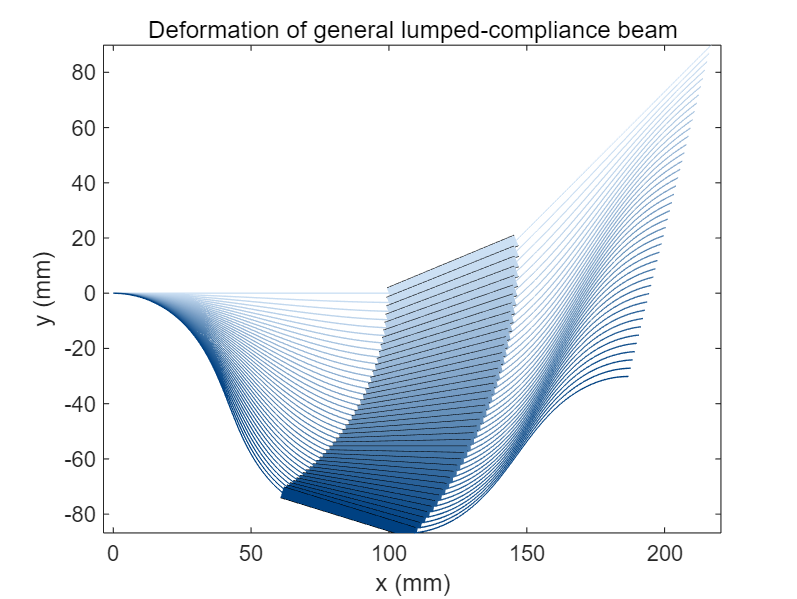


% Plot deformation
for i=1:Nt
PlotDeformation_GLB(SolutionVectorHistory(i,:),FrameParameter,BeamProperty,i,Nt);
axis equal
hold on
xlabel('x (mm)');
ylabel('y (mm)' );
title('Deformation of general lumped-compliance beam');  
end
hold off

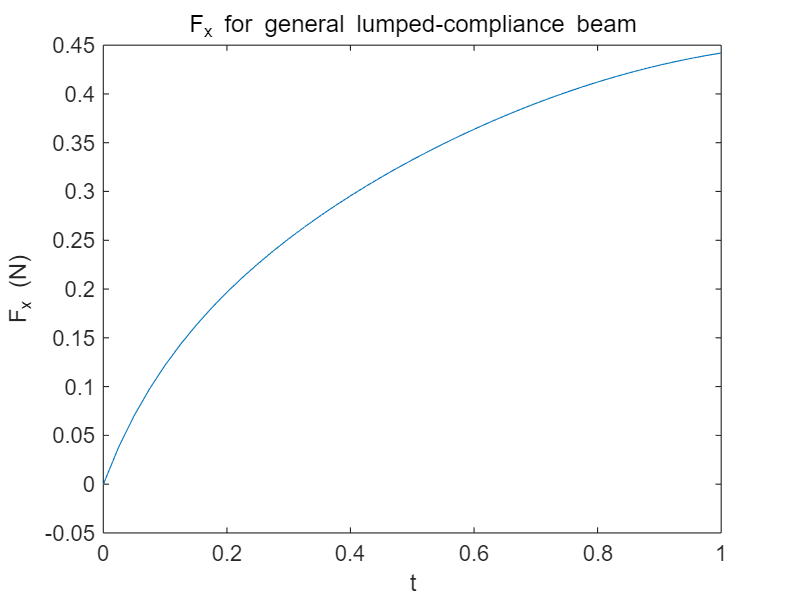


% Plot force(Fx)-scale parameter relationship
% t is normalized scale parameter, range from 0 to 1, representing
% deformation process
plot(linspace(0,1,Nt),Lam(:,1)) 
xlabel('t');
ylabel('F_x (N)' ); 
title('F_x for general lumped-compliance beam');

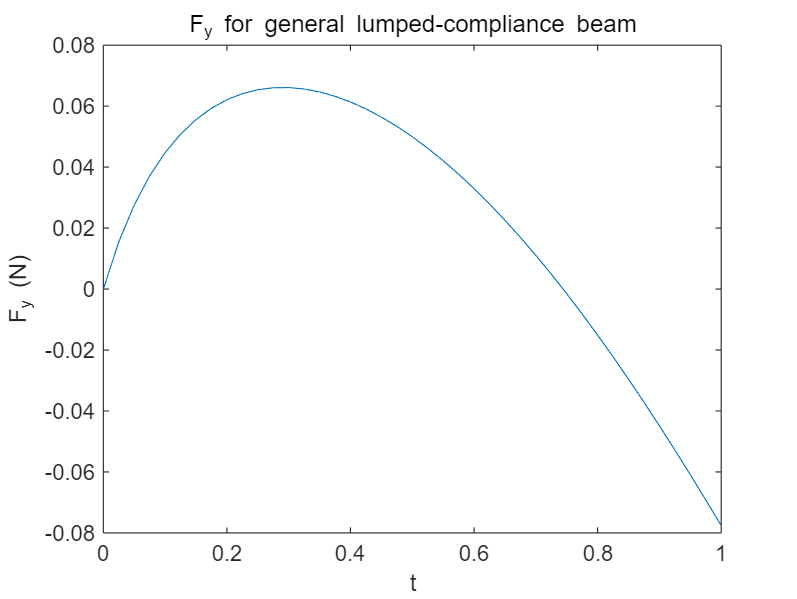


% Plot force(Fy)-scale parameter relationship 
plot(linspace(0,1,Nt),Lam(:,2)) 
xlabel('t');
ylabel('F_y (N)' ); 
title('F_y for general lumped-compliance beam');

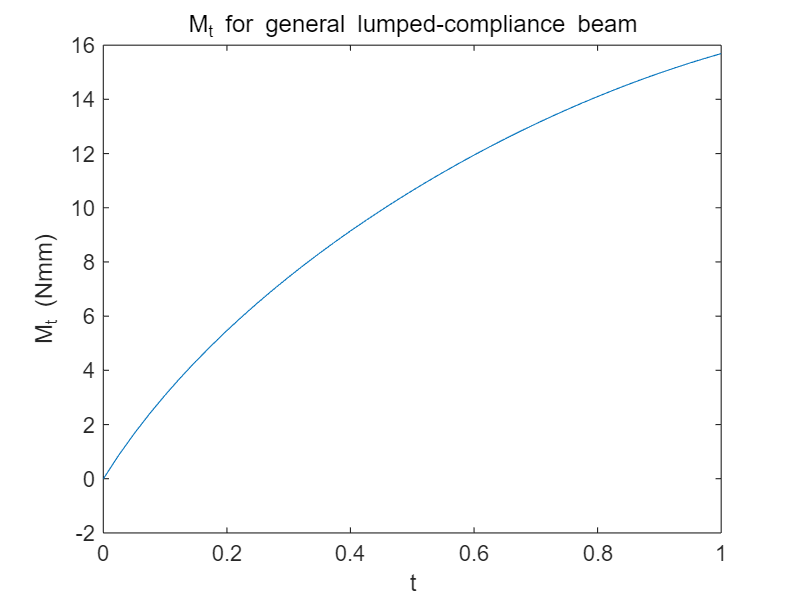


% Plot moment-scale parameter relationship 
plot(linspace(0,1,Nt),Lam(:,3)*1000) 
xlabel('t');
ylabel('M_t (Nmm)' ); 
title('M_t for general lumped-compliance beam');

## **5. Initially curved beam**

This section presents the modeling of an initially curved beam, using a cosine shaped beam as an example.  

clear CaseStudy Delta_x Delta_y Xt Yt Phit Nt Tip_trajectory SolutionVector SolutionVectorHistory SolutionVector  Initial_SolutionVector SolutionVector_Previous StrainEnergyHistory Lam Energy_History SolutionVector

fprintf('========================================================\n');

fprintf('Case Study 5: Initially curved beam (cosine-shaped beam)');

Case Study 5: Initially curved beam (cosine-shaped beam)

fprintf('========================================================\n');




% Case study indicator for adjusting constraint condition + Inclined angle
% (CaseStudy is 5)
CaseStudy = 5;

% Total number of steps
Nt =51; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%  Fitting process  %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%% 

% Parameter definition of cosine-shaped beam
Amp_cos = 25/1000;       % Amplitude of the cosine shaped beam in meters (25 mm -> 0.025 m)
f_cos   = 1000/180;      % Frequency controlling the cosine period along x (1/m)
a_cos   = 0;             % Start position of x coordinate (m)
b_cos   = 90/1000;       % End position of x coordinate (90 mm -> 0.09 m)
SP  = 500;           % Number of sampling points (or discretization points) used in fitting/plotting

Sine_x = linspace(a_cos, b_cos, 51)';                     % Generate 51 evenly spaced x points from a to b (column vector)
Sine_y = -Amp_cos * cos(2 * pi * f_cos .* Sine_x) + Amp_cos;  % Compute y values using cosine function and shift upward by Amp
Sine_Curve_shape = 1000*[Sine_x, Sine_y];         % Combine x and y into a 2 column matrix and convert to mm (multiply by 1000)

% Plot the cosine shaped beam curve in mm
plot(Sine_Curve_shape(:,1), Sine_Curve_shape(:,2), 'LineWidth', 2, 'Color', [150 0 0]/255')  
hold on      

% Fit the beam initial geometry and obtain fitted parameters and beam length
[Initial_SolutionVector_Curved, L] = MultipleLinearRegression(Amp_cos, f_cos, a_cos, b_cos, SP);

Beam length: 105.2437


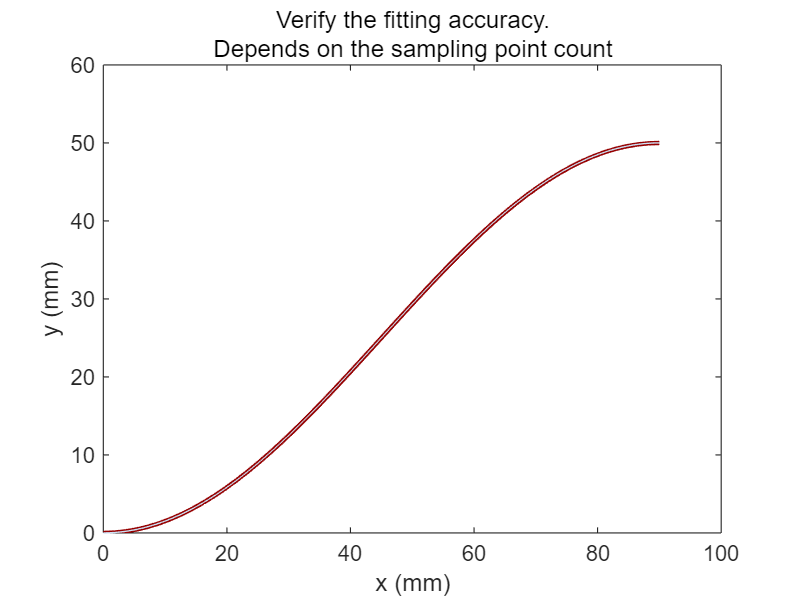


% As no axial stress and axial deformation occurs, thus beta are set as zeros. 
Initial_SolutionVector_Curved = [Initial_SolutionVector_Curved,zeros(1,6)];

% Plot the fitted beam using BeamPlot (append zeros for additional DOFs if required)
BeamProperty(1) = L;

[Initial_Tip_Points,MaxStress] = PlotDeformation([Initial_SolutionVector_Curved,zeros(1,6)],BeamProperty,1,Nt,CaseStudy);
hold off          
title('Verify the fitting accuracy.') 
subtitle('Depends on the sampling point count')
xlabel('x (mm)');
ylabel('y (mm)');



%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Modeling process  %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Set displacement along -x direction (mm)
Delta_y = 100e-3;

% Derive tip trajectory points
Tip_x_CurvedBeam = Initial_Tip_Points(end,1)/1000;
Tip_y_CurvedBeam = Initial_Tip_Points(end,2)/1000;

Xt = Tip_x_CurvedBeam + 0*linspace(0,1,Nt)';
Yt = Tip_y_CurvedBeam - Delta_y*linspace(0,1,Nt)';
Phit =Initial_SolutionVector_Curved(1)+ 0*linspace(0,1,Nt)';

Tip_trajectory = [Xt,Yt,Phit];

% Define initial guess solution
SolutionVector = Initial_SolutionVector_Curved;
SolutionVectorHistory = Initial_SolutionVector_Curved;
SolutionVector_Previous = Initial_SolutionVector_Curved;

% Define objective function
Energy = @(SolutionVector) StrainEnergy(SolutionVector,SolutionVector_Previous,BeamProperty);
fprintf('Case Study 5 -- Step Number:');

Case Study 5 -- Step Number:

for i = 1:Nt
% Current step number
i 
% Nonlinear constraint function updated iteratively
nonlcon = @(SolutionVector_Current) PositionConstraint(SolutionVector_Current, BeamProperty, Tip_trajectory(i,:),CaseStudy);

% Solve
[x_min, fval, exitflag, output, lambda] = fmincon(Energy, SolutionVector, A, b, Aeq, beq, lb, ub, nonlcon, options);

% Update for next step (same role as P0 = x_min in your old code)
SolutionVector = x_min;
SolutionVector_Previous = x_min;

% Record
SolutionVectorHistory(i,:) = x_min; 
Lam(i,:) = lambda.eqnonlin(:).'; 
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

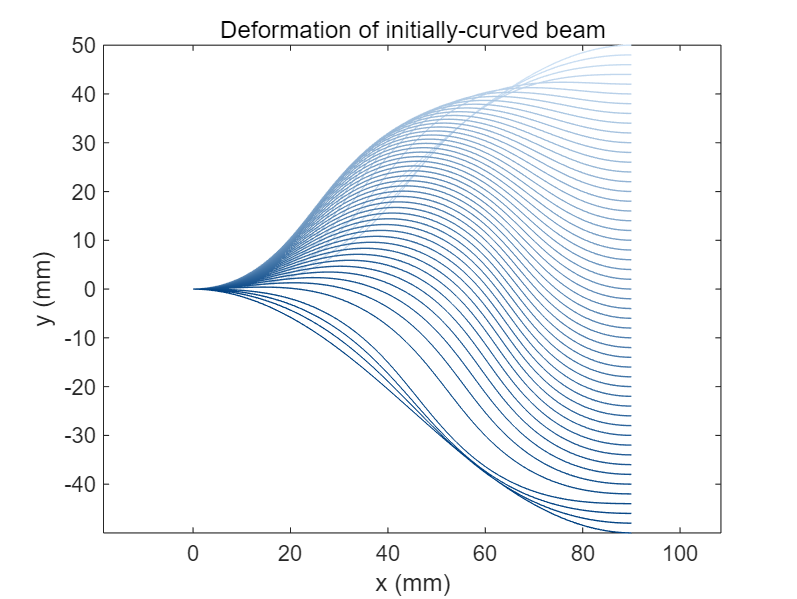


% Plot deformation
for i=1:Nt
[Points,MaxStress(i,:)]=PlotDeformation(SolutionVectorHistory(i,:),BeamProperty,i,Nt,CaseStudy);
axis equal
hold on
xlabel('x (mm)');
ylabel('y (mm)' );
title('Deformation of initially-curved beam'); 
X_tip_position(i,:) = Points(end,1);
end
hold off

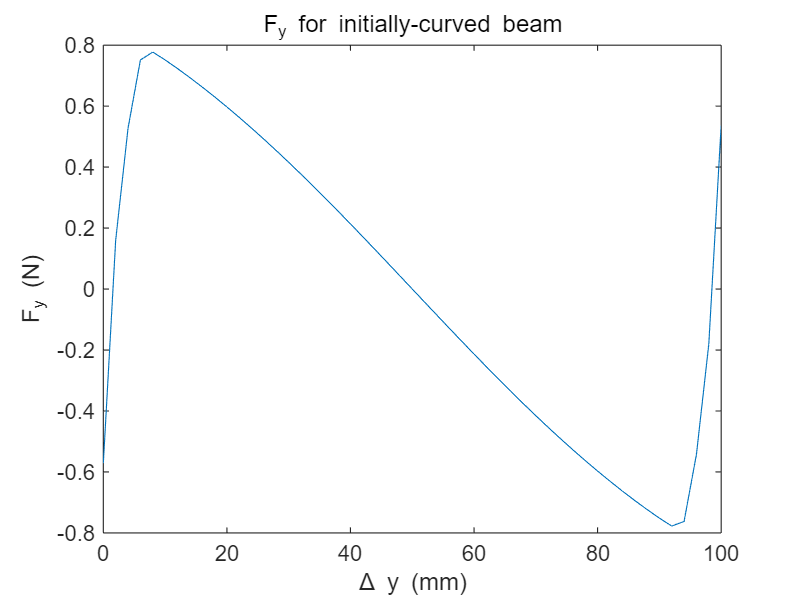


% Plot force-displacement relationship

% Please note: If the force–displacement curve is plotted for the entire mechanism,
% the result should be multiplied by 2. 
plot(Delta_y*1000*linspace(0,1,Nt), Lam(:,2) )
xlabel('\Delta y (mm)');
ylabel('F_y (N)' );
xlim([0,Delta_y*1000])
title('F_y for initially-curved beam');

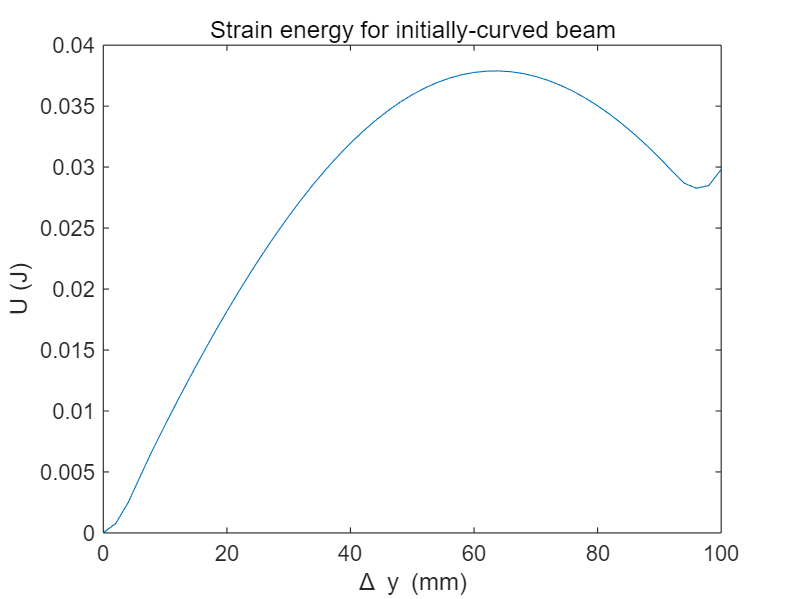


% Plot energy-displacement relationship

% Please note: If the energy–displacement curve is plotted for the entire mechanism,
% the result should be multiplied by 2.
CaseStudy = [CaseStudy, Initial_SolutionVector_Curved];
for i=1:Nt
    Energy_History(i,:) = StrainEnergy_Current(SolutionVectorHistory(i,:),BeamProperty,CaseStudy);
end

plot(Delta_y*1000*linspace(0,1,Nt),Energy_History)
xlabel('\Delta y (mm)');
ylabel('U (J)' ); 
title('Strain energy for initially-curved beam');

## **6. Functions Called in the Main Code **

#### 6.1 Calculate strain energy difference between current step and previous step

Optimization objective: minimize the change in strain energy as the target point moves from the previous step to the current step. In each iteration, the solution obtained at the current step is used as the initial guess for the next trajectory point, and the current step becomes the previous step. This iterative process continues until the termination criterion is satisfied.

function [Energy] = StrainEnergy(SolutionVector,SolutionVector_Previous,BeamProperty)

% Extract the generalized coordinates (alphas) for bending strain energy
Alpha0 = SolutionVector(1);
Alpha1 = SolutionVector(2);
Alpha2 = SolutionVector(3);
Alpha3 = SolutionVector(4);
Alpha4 = SolutionVector(5);
Alpha5 = SolutionVector(6);

% Extract the generalized coordinates (betas) for axial strain energy
Beta0 = SolutionVector(7);
Beta1 = SolutionVector(8);
Beta2 = SolutionVector(9);
Beta3 = SolutionVector(10);
Beta4 = SolutionVector(11);
Beta5 = SolutionVector(12);

% Generalized coordinates (alphas) from the previous step
Alpha0_previous = SolutionVector_Previous(1);
Alpha1_previous = SolutionVector_Previous(2);
Alpha2_previous = SolutionVector_Previous(3);
Alpha3_previous = SolutionVector_Previous(4);
Alpha4_previous = SolutionVector_Previous(5);
Alpha5_previous = SolutionVector_Previous(6);

% Generalized coordinates (betas) from the previous step
Beta0_previous = SolutionVector_Previous(7);
Beta1_previous = SolutionVector_Previous(8);
Beta2_previous = SolutionVector_Previous(9);
Beta3_previous = SolutionVector_Previous(10);
Beta4_previous = SolutionVector_Previous(11);
Beta5_previous = SolutionVector_Previous(12);

% Extract beam properties
L = BeamProperty(1);
W = BeamProperty(2);
T = BeamProperty(3);
E = BeamProperty(4);
I = BeamProperty(5);
A = BeamProperty(6);

% Strain energy in preivous step
U_bending_previous = (E*I/L)*((Alpha0_previous^2)/2 + (Alpha1_previous^2)/6 +(Alpha2_previous^2)/10+(Alpha3_previous^2)/14+(Alpha4_previous^2)/18+(Alpha5_previous^2)/22 );
U_axial_previous = (A*E*L*(3465*Beta0_previous^2 + 1155*Beta1_previous^2 + 693*Beta2_previous^2 + 495*Beta3_previous^2 + 385*Beta4_previous^2 + 315*Beta5_previous^2))/6930;
Energy_previous = U_bending_previous + U_axial_previous;

% Strain energy in current step
U_bending = (E*I/L)*((Alpha0^2)/2 + (Alpha1^2)/6 +(Alpha2^2)/10+(Alpha3^2)/14+(Alpha4^2)/18+(Alpha5^2)/22 );
U_axial = (A*E*L*(3465*Beta0^2 + 1155*Beta1^2 + 693*Beta2^2 + 495*Beta3^2 + 385*Beta4^2 + 315*Beta5^2))/6930;
Energy_current = U_bending + U_axial;

% Strain energy difference between current step and previous step
Energy = Energy_current - Energy_previous;

end

#### 6.2 Calculate strain energy at current step 

function [Energy_current] = StrainEnergy_Current(SolutionVector,BeamProperty,CaseStudy)

% Extract the generalized coordinates (alphas) for bending strain energy
Alpha0 = SolutionVector(1);
Alpha1 = SolutionVector(2);
Alpha2 = SolutionVector(3);
Alpha3 = SolutionVector(4);
Alpha4 = SolutionVector(5);
Alpha5 = SolutionVector(6);

% Extract the generalized coordinates (betas) for axial strain energy
Beta0 = SolutionVector(7);
Beta1 = SolutionVector(8);
Beta2 = SolutionVector(9);
Beta3 = SolutionVector(10);
Beta4 = SolutionVector(11);
Beta5 = SolutionVector(12);


% Extract beam properties
L = BeamProperty(1);
W = BeamProperty(2);
T = BeamProperty(3);
E = BeamProperty(4);
I = BeamProperty(5);
A = BeamProperty(6);

if CaseStudy(1) == 5
% Strain energy in current step for initially-curved beam

%Coordinates used for descirbing initial shape
InitialCurved_SolutionVector = CaseStudy(2:end);

Curved_Alpha0 = InitialCurved_SolutionVector(1);
Curved_Alpha1 = InitialCurved_SolutionVector(2);
Curved_Alpha2 = InitialCurved_SolutionVector(3);
Curved_Alpha3 = InitialCurved_SolutionVector(4);
Curved_Alpha4 = InitialCurved_SolutionVector(5);
Curved_Alpha5 = InitialCurved_SolutionVector(6);
Curved_Beta0  = InitialCurved_SolutionVector(7);
Curved_Beta1  = InitialCurved_SolutionVector(8);
Curved_Beta2  = InitialCurved_SolutionVector(9);
Curved_Beta3  = InitialCurved_SolutionVector(10);
Curved_Beta4  = InitialCurved_SolutionVector(11);
Curved_Beta5  = InitialCurved_SolutionVector(12);

U_bending = (E*I/L)*(((Alpha0 - Curved_Alpha0)^2)/2 + ((Alpha1-Curved_Alpha1)^2)/6 +((Alpha2-Curved_Alpha2)^2)/10+((Alpha3-Curved_Alpha3)^2)/14+((Alpha4-Curved_Alpha4)^2)/18+((Alpha5-Curved_Alpha5)^2)/22 );
U_axial = (A*E*L*(3465*(Beta0-Curved_Beta0)^2 + 1155*(Beta1-Curved_Beta1)^2 + 693*(Beta2-Curved_Beta2)^2 + 495*(Beta3-Curved_Beta3)^2 + 385*(Beta4-Curved_Beta4)^2 + 315*(Beta5-Curved_Beta5)^2))/6930;
Energy_current = U_bending + U_axial; 
else
% Strain energy in current step for initially-straight beam
U_bending = (E*I/L)*((Alpha0^2)/2 + (Alpha1^2)/6 +(Alpha2^2)/10+(Alpha3^2)/14+(Alpha4^2)/18+(Alpha5^2)/22 );
U_axial = (A*E*L*(3465*Beta0^2 + 1155*Beta1^2 + 693*Beta2^2 + 495*Beta3^2 + 385*Beta4^2 + 315*Beta5^2))/6930;
Energy_current = U_bending + U_axial;
end



end

#### 6.3 Nonlinear constraint function with equality constraints

function [c,ceq] = PositionConstraint(SolutionVector,BeamProperty,Target_trajectory,CaseStudy)

% Extract the generalized coordinates (alphas) for curvature
Alpha0 = SolutionVector(1);
Alpha1 = SolutionVector(2);
Alpha2 = SolutionVector(3);
Alpha3 = SolutionVector(4);
Alpha4 = SolutionVector(5);
Alpha5 = SolutionVector(6);

% Extract the generalized coordinates (betas) for axial strain
Beta0 = SolutionVector(7);
Beta1 = SolutionVector(8);
Beta2 = SolutionVector(9);
Beta3 = SolutionVector(10);
Beta4 = SolutionVector(11);
Beta5 = SolutionVector(12);

% Extract beam properties
L = BeamProperty(1);
W = BeamProperty(2);
T = BeamProperty(3);
E = BeamProperty(4);
I = BeamProperty(5);
A = BeamProperty(6);

% Beam tip position derived from CoSCME method
% Expression is derived from function 'Calculate_beam_tip'
x_tip = cos((2*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (63504*Alpha5*Beta5*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^11)/(11*L^11) + (((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((1346138080689145*L)/18014398509481984 + (1346138080689145*Beta0*L)/18014398509481984) + cos((1764*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (63504*Alpha5*Beta5*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^11)/(11*L^11) + (((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((1346138080689145*L)/18014398509481984 + (1346138080689145*Beta0*L)/18014398509481984) + cos((2*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (63504*Alpha5*Beta5*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^11)/(11*L^11) + (((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((332730697076079*L)/2251799813685248 + (332730697076079*Beta0*L)/2251799813685248) + cos((2*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L + (63504*Alpha5*Beta5*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^11)/(11*L^11))*((4850677986991099*L)/36028797018963968 + (4850677986991099*Beta0*L)/36028797018963968) + cos((1764*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (63504*Alpha5*Beta5*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((3946709042355737*L)/36028797018963968 + (3946709042355737*Beta0*L)/36028797018963968) + cos((((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (63504*Alpha5*Beta5*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^11)/(11*L^11) + (((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((332730697076079*L)/2251799813685248 + (332730697076079*Beta0*L)/2251799813685248) + cos((7*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (63504*Alpha5*Beta5*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((4804176662158359*L)/144115188075855872 + (4804176662158359*Beta0*L)/144115188075855872) + cos((7*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (63504*Alpha5*Beta5*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((4804176662158359*L)/144115188075855872 + (4804176662158359*Beta0*L)/144115188075855872) + cos((2*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (63504*Alpha5*Beta5*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((3946709042355737*L)/36028797018963968 + (3946709042355737*Beta0*L)/36028797018963968) + cos((4*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L + (63504*Alpha5*Beta5*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^11)/(11*L^11))*((4850677986991099*L)/36028797018963968 + (4850677986991099*Beta0*L)/36028797018963968);
y_tip = sin((2*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (63504*Alpha5*Beta5*((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((1890847076498483*L)/2251799813685248 + (1890847076498483*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((3946709042355737*L)/36028797018963968 + (3946709042355737*Beta0*L)/36028797018963968) + sin((4*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L + (63504*Alpha5*Beta5*((2551760291865929*L)/9007199254740992 + (2551760291865929*Beta0*L)/9007199254740992)^11)/(11*L^11))*((4850677986991099*L)/36028797018963968 + (4850677986991099*Beta0*L)/36028797018963968) + sin((2*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (63504*Alpha5*Beta5*((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)^11)/(11*L^11) + (((303850285749059*L)/4503599627370496 + (303850285749059*Beta0*L)/4503599627370496)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((1346138080689145*L)/18014398509481984 + (1346138080689145*Beta0*L)/18014398509481984) + sin((1764*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (63504*Alpha5*Beta5*((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)^11)/(11*L^11) + (((4199749341621437*L)/4503599627370496 + (4199749341621437*Beta0*L)/4503599627370496)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((1346138080689145*L)/18014398509481984 + (1346138080689145*Beta0*L)/18014398509481984) + sin((2*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (63504*Alpha5*Beta5*((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)^11)/(11*L^11) + (((5174070044933199*L)/9007199254740992 + (5174070044933199*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((332730697076079*L)/2251799813685248 + (332730697076079*Beta0*L)/2251799813685248) + sin((2*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L + (63504*Alpha5*Beta5*((6455438962875063*L)/9007199254740992 + (6455438962875063*Beta0*L)/9007199254740992)^11)/(11*L^11))*((4850677986991099*L)/36028797018963968 + (4850677986991099*Beta0*L)/36028797018963968) + sin((1764*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (63504*Alpha5*Beta5*((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((360952737186765*L)/2251799813685248 + (360952737186765*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((3946709042355737*L)/36028797018963968 + (3946709042355737*Beta0*L)/36028797018963968) + sin((((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (7*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (63504*Alpha5*Beta5*((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)^11)/(11*L^11) + (((3833129209807793*L)/9007199254740992 + (3833129209807793*Beta0*L)/9007199254740992)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((332730697076079*L)/2251799813685248 + (332730697076079*Beta0*L)/2251799813685248) + sin((7*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (63504*Alpha5*Beta5*((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((29378637111717*L)/2251799813685248 + (29378637111717*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((4804176662158359*L)/144115188075855872 + (4804176662158359*Beta0*L)/144115188075855872) + sin((7*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/L^8 + (2*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(3*L^6) + (2*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(5*L^5) + (4*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(7*L^7) + (140*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(9*L^9) + (((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/L^4 + (1764*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/L^10 + (2*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(3*L^3) + (((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/L^2 + (63504*Alpha5*Beta5*((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)^11)/(11*L^11) + (((2222421176573531*L)/2251799813685248 + (2222421176573531*Beta0*L)/2251799813685248)*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/L)*((4804176662158359*L)/144115188075855872 + (4804176662158359*Beta0*L)/144115188075855872);
phi_tip = Alpha0 + Alpha0*Beta0^2 + 2*Alpha1*Beta0^2 + Alpha1*Beta0^3 + 4*Alpha2*Beta0^2 + 5*Alpha2*Beta0^3 + 7*Alpha3*Beta0^2 + 2*Alpha2*Beta0^4 + 16*Alpha3*Beta0^3 + 11*Alpha4*Beta0^2 + 15*Alpha3*Beta0^4 + 40*Alpha4*Beta0^3 + 16*Alpha5*Beta0^2 + 5*Alpha3*Beta0^5 + 65*Alpha4*Beta0^4 + 85*Alpha5*Beta0^3 + 49*Alpha4*Beta0^5 + 210*Alpha5*Beta0^4 + 14*Alpha4*Beta0^6 + 266*Alpha5*Beta0^5 + 168*Alpha5*Beta0^6 + 42*Alpha5*Beta0^7 + 2*Alpha0*Beta0 + Alpha1*Beta0 + (Alpha1*Beta1)/3 + Alpha2*Beta0 + Alpha3*Beta0 + (Alpha2*Beta2)/5 + Alpha4*Beta0 + Alpha5*Beta0 + (Alpha3*Beta3)/7 + (Alpha4*Beta4)/9 + (Alpha5*Beta5)/11 + Alpha0*Beta0*Beta1 + Alpha0*Beta0*Beta2 + Alpha1*Beta0*Beta1 + Alpha0*Beta0*Beta3 + Alpha1*Beta0*Beta2 + Alpha2*Beta0*Beta1 + Alpha0*Beta0*Beta4 + Alpha1*Beta0*Beta3 + Alpha2*Beta0*Beta2 + Alpha3*Beta0*Beta1 + Alpha0*Beta0*Beta5 + Alpha1*Beta0*Beta4 + Alpha2*Beta0*Beta3 + Alpha3*Beta0*Beta2 + Alpha4*Beta0*Beta1 + Alpha1*Beta0*Beta5 + Alpha2*Beta0*Beta4 + Alpha3*Beta0*Beta3 + Alpha4*Beta0*Beta2 + Alpha5*Beta0*Beta1 + Alpha2*Beta0*Beta5 + Alpha3*Beta0*Beta4 + Alpha4*Beta0*Beta3 + Alpha5*Beta0*Beta2 + Alpha3*Beta0*Beta5 + Alpha4*Beta0*Beta4 + Alpha5*Beta0*Beta3 + Alpha4*Beta0*Beta5 + Alpha5*Beta0*Beta4 + Alpha5*Beta0*Beta5 + Alpha0*Beta0^2*Beta1 + 3*Alpha0*Beta0^2*Beta2 + 2*Alpha1*Beta0^2*Beta1 + 6*Alpha0*Beta0^2*Beta3 + 2*Alpha0*Beta0^3*Beta2 + 4*Alpha1*Beta0^2*Beta2 + (4*Alpha1*Beta0^3*Beta1)/3 + 4*Alpha2*Beta0^2*Beta1 + 10*Alpha0*Beta0^2*Beta4 + 10*Alpha0*Beta0^3*Beta3 + 7*Alpha1*Beta0^2*Beta3 + 6*Alpha1*Beta0^3*Beta2 + 6*Alpha2*Beta0^2*Beta2 + 6*Alpha2*Beta0^3*Beta1 + 7*Alpha3*Beta0^2*Beta1 + 15*Alpha0*Beta0^2*Beta5 + 30*Alpha0*Beta0^3*Beta4 + 5*Alpha0*Beta0^4*Beta3 + 11*Alpha1*Beta0^2*Beta4 + 18*Alpha1*Beta0^3*Beta3 + 3*Alpha1*Beta0^4*Beta2 + 9*Alpha2*Beta0^2*Beta3 + 16*Alpha2*Beta0^3*Beta2 + 3*Alpha2*Beta0^4*Beta1 + 9*Alpha3*Beta0^2*Beta2 + 18*Alpha3*Beta0^3*Beta1 + 11*Alpha4*Beta0^2*Beta1 + 70*Alpha0*Beta0^3*Beta5 + 35*Alpha0*Beta0^4*Beta4 + 16*Alpha1*Beta0^2*Beta5 + (130*Alpha1*Beta0^3*Beta4)/3 + 20*Alpha1*Beta0^4*Beta3 + 13*Alpha2*Beta0^2*Beta4 + 36*Alpha2*Beta0^3*Beta3 + 18*Alpha2*Beta0^4*Beta2 + 12*Alpha3*Beta0^2*Beta3 + 36*Alpha3*Beta0^3*Beta2 + 20*Alpha3*Beta0^4*Beta1 + 13*Alpha4*Beta0^2*Beta2 + (130*Alpha4*Beta0^3*Beta1)/3 + 16*Alpha5*Beta0^2*Beta1 + 140*Alpha0*Beta0^4*Beta5 + 14*Alpha0*Beta0^5*Beta4 + 90*Alpha1*Beta0^3*Beta5 + 80*Alpha1*Beta0^4*Beta4 + 8*Alpha1*Beta0^5*Beta3 + 18*Alpha2*Beta0^2*Beta5 + 72*Alpha2*Beta0^3*Beta4 + 68*Alpha2*Beta0^4*Beta3 + (36*Alpha2*Beta0^5*Beta2)/5 + 16*Alpha3*Beta0^2*Beta4 + 68*Alpha3*Beta0^3*Beta3 + 68*Alpha3*Beta0^4*Beta2 + 8*Alpha3*Beta0^5*Beta1 + 16*Alpha4*Beta0^2*Beta3 + 72*Alpha4*Beta0^3*Beta2 + 80*Alpha4*Beta0^4*Beta1 + 18*Alpha5*Beta0^2*Beta2 + 90*Alpha5*Beta0^3*Beta1 + 126*Alpha0*Beta0^5*Beta5 + 245*Alpha1*Beta0^4*Beta5 + 70*Alpha1*Beta0^5*Beta4 + 132*Alpha2*Beta0^3*Beta5 + 200*Alpha2*Beta0^4*Beta4 + 60*Alpha2*Beta0^5*Beta3 + 21*Alpha3*Beta0^2*Beta5 + 120*Alpha3*Beta0^3*Beta4 + 190*Alpha3*Beta0^4*Beta3 + 60*Alpha3*Beta0^5*Beta2 + 20*Alpha4*Beta0^2*Beta4 + 120*Alpha4*Beta0^3*Beta3 + 200*Alpha4*Beta0^4*Beta2 + 70*Alpha4*Beta0^5*Beta1 + 21*Alpha5*Beta0^2*Beta3 + 132*Alpha5*Beta0^3*Beta2 + 245*Alpha5*Beta0^4*Beta1 + 42*Alpha0*Beta0^6*Beta5 + 350*Alpha1*Beta0^5*Beta5 + (70*Alpha1*Beta0^6*Beta4)/3 + 500*Alpha2*Beta0^4*Beta5 + 290*Alpha2*Beta0^5*Beta4 + 20*Alpha2*Beta0^6*Beta3 + 200*Alpha3*Beta0^3*Beta5 + 460*Alpha3*Beta0^4*Beta4 + 276*Alpha3*Beta0^5*Beta3 + 20*Alpha3*Beta0^6*Beta2 + 25*Alpha4*Beta0^2*Beta5 + (580*Alpha4*Beta0^3*Beta4)/3 + 460*Alpha4*Beta0^4*Beta3 + 290*Alpha4*Beta0^5*Beta2 + (70*Alpha4*Beta0^6*Beta1)/3 + 25*Alpha5*Beta0^2*Beta4 + 200*Alpha5*Beta0^3*Beta3 + 500*Alpha5*Beta0^4*Beta2 + 350*Alpha5*Beta0^5*Beta1 + 252*Alpha1*Beta0^6*Beta5 + 1050*Alpha2*Beta0^5*Beta5 + 210*Alpha2*Beta0^6*Beta4 + 1000*Alpha3*Beta0^4*Beta5 + 970*Alpha3*Beta0^5*Beta4 + 200*Alpha3*Beta0^6*Beta3 + 300*Alpha4*Beta0^3*Beta5 + 970*Alpha4*Beta0^4*Beta4 + 970*Alpha4*Beta0^5*Beta3 + 210*Alpha4*Beta0^6*Beta2 + 30*Alpha5*Beta0^2*Beta5 + 300*Alpha5*Beta0^3*Beta4 + 1000*Alpha5*Beta0^4*Beta3 + 1050*Alpha5*Beta0^5*Beta2 + 252*Alpha5*Beta0^6*Beta1 + 72*Alpha1*Beta0^7*Beta5 + 1232*Alpha2*Beta0^6*Beta5 + 60*Alpha2*Beta0^7*Beta4 + 2850*Alpha3*Beta0^5*Beta5 + 1140*Alpha3*Beta0^6*Beta4 + (400*Alpha3*Beta0^7*Beta3)/7 + 1900*Alpha4*Beta0^4*Beta5 + 2768*Alpha4*Beta0^5*Beta4 + 1140*Alpha4*Beta0^6*Beta3 + 60*Alpha4*Beta0^7*Beta2 + 440*Alpha5*Beta0^3*Beta5 + 1900*Alpha5*Beta0^4*Beta4 + 2850*Alpha5*Beta0^5*Beta3 + 1232*Alpha5*Beta0^6*Beta2 + 72*Alpha5*Beta0^7*Beta1 + 756*Alpha2*Beta0^7*Beta5 + 4802*Alpha3*Beta0^6*Beta5 + 700*Alpha3*Beta0^7*Beta4 + 7000*Alpha4*Beta0^5*Beta5 + (14000*Alpha4*Beta0^6*Beta4)/3 + 700*Alpha4*Beta0^7*Beta3 + 3430*Alpha5*Beta0^4*Beta5 + 7000*Alpha5*Beta0^5*Beta4 + 4802*Alpha5*Beta0^6*Beta3 + 756*Alpha5*Beta0^7*Beta2 + 189*Alpha2*Beta0^8*Beta5 + 4732*Alpha3*Beta0^7*Beta5 + 175*Alpha3*Beta0^8*Beta4 + 15792*Alpha4*Beta0^6*Beta5 + 4600*Alpha4*Beta0^7*Beta4 + 175*Alpha4*Beta0^8*Beta3 + 15792*Alpha5*Beta0^5*Beta5 + 15792*Alpha5*Beta0^6*Beta4 + 4732*Alpha5*Beta0^7*Beta3 + 189*Alpha5*Beta0^8*Beta2 + 2520*Alpha3*Beta0^8*Beta5 + 22120*Alpha4*Beta0^7*Beta5 + 2450*Alpha4*Beta0^8*Beta4 + 45584*Alpha5*Beta0^6*Beta5 + 22120*Alpha5*Beta0^7*Beta4 + 2520*Alpha5*Beta0^8*Beta3 + 560*Alpha3*Beta0^9*Beta5 + 18760*Alpha4*Beta0^8*Beta5 + (4900*Alpha4*Beta0^9*Beta4)/9 + 84760*Alpha5*Beta0^7*Beta5 + 18760*Alpha5*Beta0^8*Beta4 + 560*Alpha5*Beta0^9*Beta3 + 8820*Alpha4*Beta0^9*Beta5 + 101430*Alpha5*Beta0^8*Beta5 + 8820*Alpha5*Beta0^9*Beta4 + 1764*Alpha4*Beta0^10*Beta5 + 75460*Alpha5*Beta0^9*Beta5 + 1764*Alpha5*Beta0^10*Beta4 + 31752*Alpha5*Beta0^10*Beta5 + (63504*Alpha5*Beta0^11*Beta5)/11;


if CaseStudy(1) == 11      % Constraints for case study 1-1
    Position_tip = [x_tip, y_tip, phi_tip];
    c = [];
    ceq = Position_tip - Target_trajectory;

elseif CaseStudy(1) == 12 % Constraints for case study 1-2
    Position_tip = [x_tip, y_tip];
    c = [];
    ceq = Position_tip - Target_trajectory;

elseif CaseStudy(1) == 21 % Constraints for case study 2-1
    Position_tip = [y_tip, phi_tip];
    c = [];
    ceq = Position_tip - Target_trajectory;

elseif CaseStudy(1) == 22 % Constraints for case study 2-2
    Position_tip = [x_tip, y_tip, phi_tip];
    c = [];
    ceq = Position_tip - Target_trajectory;

elseif CaseStudy(1) == 31 % Constraints for case study 3-1
    Position_tip = [x_tip, y_tip, phi_tip];
    c = [];
    ceq = Position_tip - Target_trajectory;

elseif CaseStudy(1) == 32 % Constraints for case study 3-2
    Position_tip = [x_tip, y_tip, phi_tip];
    c = [];
    ceq = Position_tip - Target_trajectory;

elseif CaseStudy(1) == 5  % Constraints for case study 5
    Position_tip = [x_tip, y_tip, phi_tip];
    c = [];
    ceq = Position_tip - Target_trajectory;

else
    error('Unsupported CaseStudy value: %d', CaseStudy(1));
end



end

#### 6.4 Formulate beam tip position and orientation 

function Calculate_beam_tip

% Define symbols used in the derivation
syms s L E I A real
syms Alpha0 Alpha1 Alpha2 Alpha3 Alpha4 Alpha5 real
syms Beta0 Beta1 Beta2 Beta3 Beta4 Beta5 real
syms Xt Yt Pt real

% Compute the weights and sampling points for Gauss quadrature
[Sample_points,Weight]=Gauss_Quadrature(20,-1,1);
Weight=Weight';

% Formulate the axial strain
Axial_Strain = ( Beta0 + Beta1*( 2*(s/L)-1 ) + Beta2*( 6*(s/L)^2-6*(s/L)+1  ) + Beta3*( 20*(s/L)^3 -30*(s/L)^2 + 12*(s/L) - 1 ) + Beta4*( 70*(s/L)^4 - 140*(s/L)^3 + 90*(s/L)^2 -20*(s/L) +1) + Beta5*( 252*(s/L)^5 - 630*(s/L)^4 + 560*(s/L)^3 - 210*(s/L)^2 + 30*(s/L) - 1) );

% Formulate the beam curvature
Curvature = Alpha0/L + (Alpha1/L)*(2*(s/L)-1)+ (Alpha2/L)*(6*(s/L)^2-6*(s/L)+1)+ (Alpha3/L)*(20*(s/L)^3 - 30*(s/L)^2+12*(s/L)-1)+ (Alpha4/L)*( 70*(s/L)^4-140*(s/L)^3+90*(s/L)^2-20*(s/L)+1 )+ (Alpha5/L)*(  252*(s/L)^5 - 630*(s/L)^4 + 560*(s/L)^3 - 210*(s/L)^2 + 30*(s/L) - 1);

% Integrate the axial strain to obtain the accumulated axial deformation at point s and at the beam tip
Axial_Deformation = int(@(s) Axial_Strain,0,s);
Axial_Strain_tip = int(@(s) Axial_Strain,0,L);

% Derive the beam tip deflection angle (orientation)
Phi_tip = int(@(s) Curvature*(1+Axial_Strain), 0, (L+Axial_Strain_tip)  );
Phi_s = int(@(s) Curvature*(1+Axial_Strain), 0,s);

% Derive the beam tip position
Tip_sample_points = ( (L+Axial_Strain_tip)/2 ) * Sample_points + (L+Axial_Strain_tip)/2 ;

x_tip = ((L+Axial_Strain_tip)/2 ) * Weight* subs( cos(Phi_s )    ,s , Tip_sample_points) ;
y_tip = ((L+Axial_Strain_tip)/2 ) * Weight* subs( sin(Phi_s )    ,s , Tip_sample_points) ;

% Record the beam tip expressions in a diary file, since long expressions may not be fully displayed in the output
diary off
delete('diary')

diary on
x_tip
y_tip
Phi_tip
diary off

end

#### 6.5 Plot beam deformation shape

function [Points,MaxStress]=PlotDeformation(SolutionVector,BeamProperty,i,Nt,CaseStudy)

% Extract beam properties
L = BeamProperty(1);
W = BeamProperty(2);
T = BeamProperty(3);
E = BeamProperty(4);
I = BeamProperty(5);
A = BeamProperty(6);

% Define start point of beam
X_0 = 0;
Y_0 = 0;
Phi_0 = 0;

if CaseStudy(1) == 31
    Phi_0 = deg2rad(CaseStudy(2));
end

if CaseStudy(1) == 32 && CaseStudy(5) == 1
    Phi_0 = deg2rad(CaseStudy(2));
end

if CaseStudy(1) == 32 && CaseStudy(5) == 2
    X_0   = 2*(L*cos(deg2rad(CaseStudy(2))));
    Phi_0 = deg2rad(180-CaseStudy(2));
end


% Extract generalized coordinates
Alpha0 = SolutionVector(1);
Alpha1 = SolutionVector(2);
Alpha2 = SolutionVector(3);
Alpha3 = SolutionVector(4);
Alpha4 = SolutionVector(5);
Alpha5 = SolutionVector(6);

Beta0 = SolutionVector(7);
Beta1 = SolutionVector(8);
Beta2 = SolutionVector(9);
Beta3 = SolutionVector(10);
Beta4 = SolutionVector(11);
Beta5 = SolutionVector(12);


% Number of points describe beam deformation
N = 100;

% Discrete points
Discrete_points = linspace(0,L+Beta0*L,N);

for n=1:N
    s = Discrete_points(n);

    Fx = X_0 +(3946709042355737*s*cos( Phi_0 +   (1143797890700486842603737892337112435336398784894141963043071019732620689951475760600936128645632372700026000665252075834087*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (45702340166401949184545987276401880778269191145865845411000340750590275250128613115773600569*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (24170299509907836552060013968269398447812051723745612112945117296039362172643*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (86416136292780318689467907264477737445993543155039484493622656761268950089117348911405623565675757976436827*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (10813734488680734710319004015788354652124747684454176879196387339426816522706132416031187866419951281532235752612465016417152577988075950105*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (12782789158532582179029276932345822023919986919024595553061521*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (257633689873805092684108874083729165476053614504382450260863827615767460429642635921799802150308207933550146575248851132638722773627414204855409205884003009*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (6760350594932333033057837177007143741334444587*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(17126972312471518572699431633393941636592959488*L^3) + (3575302666702860022219901301289*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (4384313183748610648125182162189917040365761215389581412624120943713453236876534835515155435719457864207208450298685236666010911620352390563520468333273692287275744403418123*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (1890847076498483*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/36028797018963968 + (1346138080689145*s*cos( Phi_0 +   (677462102289701063457757335342521191035949137820037422552420094747752998410622175066934551217855296493344829100120900670604647*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (5487066506098362553706096920939492375963613141317136420593498912020386821871452909768010405209*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (1306522380209462411655836302023560322749985255614890715759968987704082831370957*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (23044303946419636764456505781685217959085583853867283414095343190446198717108931869934064244045143799450865333*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(65759192317667330380905456710101436766519111369432956379804147202901852703209036416983571954773523684894179328*L^7) + (14225855090323233244021602551073338632675064201315137331596677133153707513627719536053234124871945677932274493929625530865950782299130835088695*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (311095323537818793619870182717366382941151163978262425512410961*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (752787321924795784242011129173850239911206634009643378493506010147662457533721092630435177767417338236788133470092577572771477894881808377535508541719105269409*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (74074735950243943840923252135750394038496700453*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(137015778499772148581595453067151533092743675904*L^3) + (17637894532449693543832217944969*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(20282409603651670423947251286016*L^2) + (28453662536711632572644493678310914806221727381128756351429495719882482518312367028073678161116177067883580345275466278525430834655446978235042277994056954655553337476972486597*Alpha5*Beta5*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (4199749341621437*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*cos( Phi_0 +   (12583951636349986032345653950907220266165157808131818899562938070483715624516305729359973678035689978545433805977198948784327*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (276082736109331493366128008544820390347894301331284977141232281565980998546453606346086487921*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (108193052846453276558119921471935846840725983149309053684437258929847469500649*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (704496963273491986923832687346619226128084129395923205131337503878331736895517391638021128018119271409943609*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (160556140501995875961285941966776739402229194401997506485729002157160700466064342146091768901678226075433234564467418395454091351405102473915*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (42399379436749148912057887220906860885630626818730368993707681*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (5162229877747825268977798706721159411311198134155097617853881611035748257886351988119747913338975926889595052453187836294515143833766341061168169046436749641*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (16615737603529116075884387710472593493261160089*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(1096126227998177188652763624537212264741949407232*L^3) + (6511480587143691155800511033041*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (118554958975687286299130137389685970864194786412228070830211155343480512719584555426025326320181478653223444931841183100766599335250484922693730708151660318081018103397933401*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (2551760291865929*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/36028797018963968 + (1346138080689145*s*cos( Phi_0 +   (508598684887288517852342651714166214889531819546017136513153654627356157290475344999994276028782630850854465187366247*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (786969488371516278219129225706003320488983776088659160267622932270336013178308685239641*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (2589990943834264469495491559108394151135349968927509967261512503446869299*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (34160129131067997858443045647020164831376742995296138492624692310540380096211210503338705229229321117*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(9394170331095332911557922387157348109502730195633279482829163886128836100458433773854795993539074812127739904*L^7) + (772689278672991156648246762674815386409585588222818463808628472333600502853642685937838786100324914974629052116070036945568843057865*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (8523904914057779404341468286830069149583668160158273601361*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (2958251412312285303608874980600298524995690302648869941237387542992302690347059491215549255994521775793080080333177801631524896008758887295439367841*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (28052976461892885533322587938744190254012379*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(137015778499772148581595453067151533092743675904*L^3) + (92324996149784806824719385481*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(20282409603651670423947251286016*L^2) + (8089789832537807188422866777586574157986492215597079520862959942162974807510428326218299059663113591434905732617629676881319219942486417323843490296079819085504571*Alpha5*Beta5*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (303850285749059*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*cos( Phi_0 +   (21110779680008052127448697549901930691626192814938952297801878810212180012078778288685497973864125023748059610683452852768872647*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (24123116835138761802635782413992714724947062889572782999391981397849923221784745480189648417403*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (11210601001978198746589480759184864456513562124949764459477051509041346356811543*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (66739417852946631687548320461404082979761467181500913686736191672509955491099097363268977261535496872327394881*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (75710749823886185764658998854773612383253980785604366376615888801565175452350931586694299639159182381025478954644756267532069094423533566167645*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (1736613275479770964010290016294189854967932305870040493786252961*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (55423810498069575820528187790892178769734674233195807487728067451545947895961425691067628499438927969322612393844730911754226028558047265648437389850849156014409*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (89671840312587841603901340447264108603025958349*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(365375409332725729550921208179070754913983135744*L^3) + (41672692203405469013574947253969*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (3220065231842180622820707360997352434476683325703170204028687137377767905622471154929824936975501266552531334784218462678050696148664781596793196917527862203757574963116053044903*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (6455438962875063*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/36028797018963968 + (332730697076079*s*cos( Phi_0 +   (326231364081645879202023437877539616395281322282217081562964909688344268332446659539956423161269953329961975393323653921731207*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (3171909254351988197524184615734673442669269577350195475173003974840867118293506315858194550049*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (827498652076755646581478423028990370487511619648868716599003998681331141422193*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (1736905430530894631350567019503381632924331886844322339634531759673150753981017980918527397029067547344104551*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (6252434854083988463246833106646170938064097427794511608940275754677158075423558473330787763281939972889279010748790677134471918854611399480755*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (215880709149966126512355674623227928609225878436553458894660801*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (301976522462281744044771630756617506220859896778433781630273002443391636974598826559210339569714793534335282608206744710098465565120328205961293879178761798809*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (56319705737441386222676295105880313192636106257*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(1096126227998177188652763624537212264741949407232*L^3) + (14692879539081715567904003530849*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (10417635260337161474053649086094203887537278405767259474139015996669203749587724323730706074340038182551131845404414494827142348980131922961638438967720082250104479576436866833*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (3833129209807793*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/2251799813685248 + (332730697076079*s*cos( Phi_0 +   (3595476628817844376172440238065902671632620981878095639123061956193809511614106233868166470134340301126492050311189415826780807*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (6395471498763871071085260522385790236954091814188507603211922925558349901270814459787768000267*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (3708186075888217657731997401846446373205799904616877572453521126498881282265999*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (99271852514934527836666160275433408131565175967061078657261849098734190381331415592157867372588262035487492399*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (10335137734679894952191041093420422538242652834892339874345181260795795748190513330510950389814916605290787892772337382943087621173878627950885*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (716686485433169861859768962943859953040008118664714202721707201*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (6064033992274364921647260001373067281906046763837570673008398945848751263260777408011755095113872123263695704573511998907749347560317627035235877434496437388441*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (46171677822246078271532209467006408518372026533*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(365375409332725729550921208179070754913983135744*L^3) + (26771000829875035918852372373601*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (282381629677951224849983461604700789099551323178783020514209201145381702585206694793623536684849965283474804283905558175118990982869870305059074016255848070520239297522737774831*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (5174070044933199*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/2251799813685248 + (4804176662158359*s*cos( Phi_0 +   (3884643762833458146468430153996583846806988174606444625035226773987885287698023786362862275184866367386011687*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (214322918274693775433578556025334982089052139299020601908166192458338463297216323*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (21885588238116324630822533710274031697129870891859415373784708598357*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (18889545722149224526549759555696724357034338005745995695150619461840797577644818704200600869773*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (63403077453655003106807936223962970883023595699328695778899563211517529874736326179266780224861212054316662330774270353655*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (744949064685773202185043808593553626483210926430471921*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (211229726885013644269419221738913465272200727903971345336725237545411096379974135881191978525077526733903174612657687822477916726506857009*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (8452276187999967294837024714723036746271*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(5708990770823839524233143877797980545530986496*L^3) + (863104318541955391938688089*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (55850773440257171941063201318230791990852582784368943590675342786115032812619690955514063223752550876933007128019120965983602598392347877121349497270077*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (29378637111717*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*cos( Phi_0 +   (2016976118741561058769478747268648584995144482640974336767380808052282707348920023432969602572308194492963111377734375*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (737192286463830135937912097641200684904952885729589066546371442450877246538865856921875*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (1225410770744298966112807899774041174652937820647963414264139458251245625*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(28948022309329048855892746252171976963317496166410141009864396001978282409984*L^5) + (798274720896267769353866007142340352296028524629250823475423834754445577915696490644897374569666953125*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (404462806055613335906793809461684266266002047609070463612993003885612754961804042383475312368186361685655834575726288339831630859375*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (16974670704744428787618380786376081657741135821978249300625*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (16555487916543908648905361353194860466325833505151809603535946699028411962057014114510112998627144817354153318837593551445789061128732176500087890625*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (15675801802606782298875520738169497766082375*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(5708990770823839524233143877797980545530986496*L^3) + (130286878482617844886491165225*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (53781738110450433974103167999002665535045596472357742143399763035543304613408546792962714479172037766571508965086903459325499255373640842044433228251203749658203125*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (360952737186765*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/36028797018963968 + (4804176662158359*s*cos( Phi_0 +   (4165901269390790270689769000987237745816534103352399231832895535409805697394466506136944173440461126748701852908652763138087*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (120491996303875105993201731103886680132027564905492170502545689276433515326054067695585844681*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (54216544358907889154532124800631721510826916740855468755327460678282252596651*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (267783964193351661550693832660522595871499767604482139754871931795957493933145295046074618444418409941738611*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (46291936003043232189453420445406879884771911269062236320306826075614812146270158299469122283575626560143080694499684084147746444128310875985*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (24395260867023186965082917909238257959896072109267156578977521*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (1296290253859649244114502669650847944565850378395530840448006556089897097988738725388102443218140160428108053305178653681236920624442481483618854354519368241*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (10976884635627501482701333546132067376345680291*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(17126972312471518572699431633393941636592959488*L^3) + (4939155886082477855313849807961*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (25928126200472065718749583331301306460880664318997736392498648661246042465167232528063122983583064560095269368688531632920713342239210457292556038903125543939679072823660739*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (2222421176573531*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/144115188075855872;
    Fy = Y_0 +(4804176662158359*s*sin( Phi_0 +   (4165901269390790270689769000987237745816534103352399231832895535409805697394466506136944173440461126748701852908652763138087*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (120491996303875105993201731103886680132027564905492170502545689276433515326054067695585844681*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (54216544358907889154532124800631721510826916740855468755327460678282252596651*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (267783964193351661550693832660522595871499767604482139754871931795957493933145295046074618444418409941738611*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (46291936003043232189453420445406879884771911269062236320306826075614812146270158299469122283575626560143080694499684084147746444128310875985*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (24395260867023186965082917909238257959896072109267156578977521*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (1296290253859649244114502669650847944565850378395530840448006556089897097988738725388102443218140160428108053305178653681236920624442481483618854354519368241*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (10976884635627501482701333546132067376345680291*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(17126972312471518572699431633393941636592959488*L^3) + (4939155886082477855313849807961*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (25928126200472065718749583331301306460880664318997736392498648661246042465167232528063122983583064560095269368688531632920713342239210457292556038903125543939679072823660739*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (2222421176573531*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*sin( Phi_0 +   (1143797890700486842603737892337112435336398784894141963043071019732620689951475760600936128645632372700026000665252075834087*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (45702340166401949184545987276401880778269191145865845411000340750590275250128613115773600569*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (24170299509907836552060013968269398447812051723745612112945117296039362172643*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (86416136292780318689467907264477737445993543155039484493622656761268950089117348911405623565675757976436827*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (10813734488680734710319004015788354652124747684454176879196387339426816522706132416031187866419951281532235752612465016417152577988075950105*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (12782789158532582179029276932345822023919986919024595553061521*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (257633689873805092684108874083729165476053614504382450260863827615767460429642635921799802150308207933550146575248851132638722773627414204855409205884003009*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (6760350594932333033057837177007143741334444587*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(17126972312471518572699431633393941636592959488*L^3) + (3575302666702860022219901301289*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (4384313183748610648125182162189917040365761215389581412624120943713453236876534835515155435719457864207208450298685236666010911620352390563520468333273692287275744403418123*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (1890847076498483*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/36028797018963968 + (1346138080689145*s*sin( Phi_0 +   (677462102289701063457757335342521191035949137820037422552420094747752998410622175066934551217855296493344829100120900670604647*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (5487066506098362553706096920939492375963613141317136420593498912020386821871452909768010405209*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (1306522380209462411655836302023560322749985255614890715759968987704082831370957*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (23044303946419636764456505781685217959085583853867283414095343190446198717108931869934064244045143799450865333*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(65759192317667330380905456710101436766519111369432956379804147202901852703209036416983571954773523684894179328*L^7) + (14225855090323233244021602551073338632675064201315137331596677133153707513627719536053234124871945677932274493929625530865950782299130835088695*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (311095323537818793619870182717366382941151163978262425512410961*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (752787321924795784242011129173850239911206634009643378493506010147662457533721092630435177767417338236788133470092577572771477894881808377535508541719105269409*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (74074735950243943840923252135750394038496700453*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(137015778499772148581595453067151533092743675904*L^3) + (17637894532449693543832217944969*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(20282409603651670423947251286016*L^2) + (28453662536711632572644493678310914806221727381128756351429495719882482518312367028073678161116177067883580345275466278525430834655446978235042277994056954655553337476972486597*Alpha5*Beta5*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (4199749341621437*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*sin( Phi_0 +   (12583951636349986032345653950907220266165157808131818899562938070483715624516305729359973678035689978545433805977198948784327*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (276082736109331493366128008544820390347894301331284977141232281565980998546453606346086487921*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (108193052846453276558119921471935846840725983149309053684437258929847469500649*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (704496963273491986923832687346619226128084129395923205131337503878331736895517391638021128018119271409943609*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (160556140501995875961285941966776739402229194401997506485729002157160700466064342146091768901678226075433234564467418395454091351405102473915*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (42399379436749148912057887220906860885630626818730368993707681*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (5162229877747825268977798706721159411311198134155097617853881611035748257886351988119747913338975926889595052453187836294515143833766341061168169046436749641*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (16615737603529116075884387710472593493261160089*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(1096126227998177188652763624537212264741949407232*L^3) + (6511480587143691155800511033041*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (118554958975687286299130137389685970864194786412228070830211155343480512719584555426025326320181478653223444931841183100766599335250484922693730708151660318081018103397933401*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (2551760291865929*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/36028797018963968 + (1346138080689145*s*sin( Phi_0 +   (508598684887288517852342651714166214889531819546017136513153654627356157290475344999994276028782630850854465187366247*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (786969488371516278219129225706003320488983776088659160267622932270336013178308685239641*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (2589990943834264469495491559108394151135349968927509967261512503446869299*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (34160129131067997858443045647020164831376742995296138492624692310540380096211210503338705229229321117*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(9394170331095332911557922387157348109502730195633279482829163886128836100458433773854795993539074812127739904*L^7) + (772689278672991156648246762674815386409585588222818463808628472333600502853642685937838786100324914974629052116070036945568843057865*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (8523904914057779404341468286830069149583668160158273601361*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (2958251412312285303608874980600298524995690302648869941237387542992302690347059491215549255994521775793080080333177801631524896008758887295439367841*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (28052976461892885533322587938744190254012379*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(137015778499772148581595453067151533092743675904*L^3) + (92324996149784806824719385481*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(20282409603651670423947251286016*L^2) + (8089789832537807188422866777586574157986492215597079520862959942162974807510428326218299059663113591434905732617629676881319219942486417323843490296079819085504571*Alpha5*Beta5*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (303850285749059*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*sin( Phi_0 +   (21110779680008052127448697549901930691626192814938952297801878810212180012078778288685497973864125023748059610683452852768872647*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (24123116835138761802635782413992714724947062889572782999391981397849923221784745480189648417403*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (11210601001978198746589480759184864456513562124949764459477051509041346356811543*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (66739417852946631687548320461404082979761467181500913686736191672509955491099097363268977261535496872327394881*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (75710749823886185764658998854773612383253980785604366376615888801565175452350931586694299639159182381025478954644756267532069094423533566167645*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (1736613275479770964010290016294189854967932305870040493786252961*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (55423810498069575820528187790892178769734674233195807487728067451545947895961425691067628499438927969322612393844730911754226028558047265648437389850849156014409*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (89671840312587841603901340447264108603025958349*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(365375409332725729550921208179070754913983135744*L^3) + (41672692203405469013574947253969*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (3220065231842180622820707360997352434476683325703170204028687137377767905622471154929824936975501266552531334784218462678050696148664781596793196917527862203757574963116053044903*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (6455438962875063*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/36028797018963968 + (332730697076079*s*sin( Phi_0 +   (326231364081645879202023437877539616395281322282217081562964909688344268332446659539956423161269953329961975393323653921731207*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (3171909254351988197524184615734673442669269577350195475173003974840867118293506315858194550049*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (827498652076755646581478423028990370487511619648868716599003998681331141422193*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (1736905430530894631350567019503381632924331886844322339634531759673150753981017980918527397029067547344104551*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (6252434854083988463246833106646170938064097427794511608940275754677158075423558473330787763281939972889279010748790677134471918854611399480755*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (215880709149966126512355674623227928609225878436553458894660801*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (301976522462281744044771630756617506220859896778433781630273002443391636974598826559210339569714793534335282608206744710098465565120328205961293879178761798809*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (56319705737441386222676295105880313192636106257*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(1096126227998177188652763624537212264741949407232*L^3) + (14692879539081715567904003530849*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (10417635260337161474053649086094203887537278405767259474139015996669203749587724323730706074340038182551131845404414494827142348980131922961638438967720082250104479576436866833*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (3833129209807793*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/2251799813685248 + (332730697076079*s*sin( Phi_0 +   (3595476628817844376172440238065902671632620981878095639123061956193809511614106233868166470134340301126492050311189415826780807*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (6395471498763871071085260522385790236954091814188507603211922925558349901270814459787768000267*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (3708186075888217657731997401846446373205799904616877572453521126498881282265999*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (99271852514934527836666160275433408131565175967061078657261849098734190381331415592157867372588262035487492399*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (10335137734679894952191041093420422538242652834892339874345181260795795748190513330510950389814916605290787892772337382943087621173878627950885*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (716686485433169861859768962943859953040008118664714202721707201*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (6064033992274364921647260001373067281906046763837570673008398945848751263260777408011755095113872123263695704573511998907749347560317627035235877434496437388441*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (46171677822246078271532209467006408518372026533*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(365375409332725729550921208179070754913983135744*L^3) + (26771000829875035918852372373601*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(81129638414606681695789005144064*L^2) + (282381629677951224849983461604700789099551323178783020514209201145381702585206694793623536684849965283474804283905558175118990982869870305059074016255848070520239297522737774831*Alpha5*Beta5*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (5174070044933199*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(9007199254740992*L)))/2251799813685248 + (4804176662158359*s*sin( Phi_0 +   (3884643762833458146468430153996583846806988174606444625035226773987885287698023786362862275184866367386011687*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (214322918274693775433578556025334982089052139299020601908166192458338463297216323*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (21885588238116324630822533710274031697129870891859415373784708598357*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (18889545722149224526549759555696724357034338005745995695150619461840797577644818704200600869773*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (63403077453655003106807936223962970883023595699328695778899563211517529874736326179266780224861212054316662330774270353655*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (744949064685773202185043808593553626483210926430471921*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (211229726885013644269419221738913465272200727903971345336725237545411096379974135881191978525077526733903174612657687822477916726506857009*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (8452276187999967294837024714723036746271*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(5708990770823839524233143877797980545530986496*L^3) + (863104318541955391938688089*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (55850773440257171941063201318230791990852582784368943590675342786115032812619690955514063223752550876933007128019120965983602598392347877121349497270077*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (29378637111717*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*sin( Phi_0 +   (2016976118741561058769478747268648584995144482640974336767380808052282707348920023432969602572308194492963111377734375*s^8*(27*Alpha2*Beta5 + 25*Alpha3*Beta4 + 25*Alpha4*Beta3 + 27*Alpha5*Beta2 - 360*Alpha3*Beta5 - 350*Alpha4*Beta4 - 360*Alpha5*Beta3 + 2680*Alpha4*Beta5 + 2680*Alpha5*Beta4 - 14490*Alpha5*Beta5))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (737192286463830135937912097641200684904952885729589066546371442450877246538865856921875*s^6*(63*Alpha5 + 63*Alpha0*Beta5 + 35*Alpha1*Beta4 + 30*Alpha2*Beta3 + 30*Alpha3*Beta2 + 35*Alpha4*Beta1 + 63*Alpha5*Beta0 - 378*Alpha1*Beta5 - 315*Alpha2*Beta4 - 300*Alpha3*Beta3 - 315*Alpha4*Beta2 - 378*Alpha5*Beta1 + 1848*Alpha2*Beta5 + 1710*Alpha3*Beta4 + 1710*Alpha4*Beta3 + 1848*Alpha5*Beta2 - 7203*Alpha3*Beta5 - 7000*Alpha4*Beta4 - 7203*Alpha5*Beta3 + 23688*Alpha4*Beta5 + 23688*Alpha5*Beta4 - 68376*Alpha5*Beta5))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (1225410770744298966112807899774041174652937820647963414264139458251245625*s^5*(35*Alpha4 - 315*Alpha5 + 35*Alpha0*Beta4 + 20*Alpha1*Beta3 + 18*Alpha2*Beta2 + 20*Alpha3*Beta1 + 35*Alpha4*Beta0 - 315*Alpha0*Beta5 - 175*Alpha1*Beta4 - 150*Alpha2*Beta3 - 150*Alpha3*Beta2 - 175*Alpha4*Beta1 - 315*Alpha5*Beta0 + 875*Alpha1*Beta5 + 725*Alpha2*Beta4 + 690*Alpha3*Beta3 + 725*Alpha4*Beta2 + 875*Alpha5*Beta1 - 2625*Alpha2*Beta5 - 2425*Alpha3*Beta4 - 2425*Alpha4*Beta3 - 2625*Alpha5*Beta2 + 7125*Alpha3*Beta5 + 6920*Alpha4*Beta4 + 7125*Alpha5*Beta3 - 17500*Alpha4*Beta5 - 17500*Alpha5*Beta4 + 39480*Alpha5*Beta5))/(28948022309329048855892746252171976963317496166410141009864396001978282409984*L^5) + (798274720896267769353866007142340352296028524629250823475423834754445577915696490644897374569666953125*s^7*(126*Alpha1*Beta5 + 105*Alpha2*Beta4 + 100*Alpha3*Beta3 + 105*Alpha4*Beta2 + 126*Alpha5*Beta1 - 1323*Alpha2*Beta5 - 1225*Alpha3*Beta4 - 1225*Alpha4*Beta3 - 1323*Alpha5*Beta2 + 8281*Alpha3*Beta5 + 8050*Alpha4*Beta4 + 8281*Alpha5*Beta3 - 38710*Alpha4*Beta5 - 38710*Alpha5*Beta4 + 148330*Alpha5*Beta5))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (404462806055613335906793809461684266266002047609070463612993003885612754961804042383475312368186361685655834575726288339831630859375*s^9*(36*Alpha3*Beta5 + 35*Alpha4*Beta4 + 36*Alpha5*Beta3 - 567*Alpha4*Beta5 - 567*Alpha5*Beta4 + 4851*Alpha5*Beta5))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (16974670704744428787618380786376081657741135821978249300625*s^4*(5*Alpha3 - 35*Alpha4 + 140*Alpha5 + 5*Alpha0*Beta3 + 3*Alpha1*Beta2 + 3*Alpha2*Beta1 + 5*Alpha3*Beta0 - 35*Alpha0*Beta4 - 20*Alpha1*Beta3 - 18*Alpha2*Beta2 - 20*Alpha3*Beta1 - 35*Alpha4*Beta0 + 140*Alpha0*Beta5 + 80*Alpha1*Beta4 + 68*Alpha2*Beta3 + 68*Alpha3*Beta2 + 80*Alpha4*Beta1 + 140*Alpha5*Beta0 - 245*Alpha1*Beta5 - 200*Alpha2*Beta4 - 190*Alpha3*Beta3 - 200*Alpha4*Beta2 - 245*Alpha5*Beta1 + 500*Alpha2*Beta5 + 460*Alpha3*Beta4 + 460*Alpha4*Beta3 + 500*Alpha5*Beta2 - 1000*Alpha3*Beta5 - 970*Alpha4*Beta4 - 1000*Alpha5*Beta3 + 1900*Alpha4*Beta5 + 1900*Alpha5*Beta4 - 3430*Alpha5*Beta5))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (16555487916543908648905361353194860466325833505151809603535946699028411962057014114510112998627144817354153318837593551445789061128732176500087890625*s^10*(Alpha4*Beta5 + Alpha5*Beta4 - 18*Alpha5*Beta5))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (15675801802606782298875520738169497766082375*s^3*(3*Alpha2 - 15*Alpha3 + 45*Alpha4 - 105*Alpha5 + 3*Alpha0*Beta2 + 2*Alpha1*Beta1 + 3*Alpha2*Beta0 - 15*Alpha0*Beta3 - 9*Alpha1*Beta2 - 9*Alpha2*Beta1 - 15*Alpha3*Beta0 + 45*Alpha0*Beta4 + 27*Alpha1*Beta3 + 24*Alpha2*Beta2 + 27*Alpha3*Beta1 + 45*Alpha4*Beta0 - 105*Alpha0*Beta5 - 65*Alpha1*Beta4 - 54*Alpha2*Beta3 - 54*Alpha3*Beta2 - 65*Alpha4*Beta1 - 105*Alpha5*Beta0 + 135*Alpha1*Beta5 + 108*Alpha2*Beta4 + 102*Alpha3*Beta3 + 108*Alpha4*Beta2 + 135*Alpha5*Beta1 - 198*Alpha2*Beta5 - 180*Alpha3*Beta4 - 180*Alpha4*Beta3 - 198*Alpha5*Beta2 + 300*Alpha3*Beta5 + 290*Alpha4*Beta4 + 300*Alpha5*Beta3 - 450*Alpha4*Beta5 - 450*Alpha5*Beta4 + 660*Alpha5*Beta5))/(5708990770823839524233143877797980545530986496*L^3) + (130286878482617844886491165225*s^2*(Alpha1 - 3*Alpha2 + 6*Alpha3 - 10*Alpha4 + 15*Alpha5 + Alpha0*Beta1 + Alpha1*Beta0 - 3*Alpha0*Beta2 - 2*Alpha1*Beta1 - 3*Alpha2*Beta0 + 6*Alpha0*Beta3 + 4*Alpha1*Beta2 + 4*Alpha2*Beta1 + 6*Alpha3*Beta0 - 10*Alpha0*Beta4 - 7*Alpha1*Beta3 - 6*Alpha2*Beta2 - 7*Alpha3*Beta1 - 10*Alpha4*Beta0 + 15*Alpha0*Beta5 + 11*Alpha1*Beta4 + 9*Alpha2*Beta3 + 9*Alpha3*Beta2 + 11*Alpha4*Beta1 + 15*Alpha5*Beta0 - 16*Alpha1*Beta5 - 13*Alpha2*Beta4 - 12*Alpha3*Beta3 - 13*Alpha4*Beta2 - 16*Alpha5*Beta1 + 18*Alpha2*Beta5 + 16*Alpha3*Beta4 + 16*Alpha4*Beta3 + 18*Alpha5*Beta2 - 21*Alpha3*Beta5 - 20*Alpha4*Beta4 - 21*Alpha5*Beta3 + 25*Alpha4*Beta5 + 25*Alpha5*Beta4 - 30*Alpha5*Beta5))/(5070602400912917605986812821504*L^2) + (53781738110450433974103167999002665535045596472357742143399763035543304613408546792962714479172037766571508965086903459325499255373640842044433228251203749658203125*Alpha5*Beta5*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (360952737186765*s*(Alpha0 - Alpha1 + Alpha2 - Alpha3 + Alpha4 - Alpha5)*(Beta0 - Beta1 + Beta2 - Beta3 + Beta4 - Beta5 + 1))/(2251799813685248*L)))/36028797018963968;

    BendingStress(n,:) = (E*T/2)*(Alpha0/L + (Alpha1/L)*(2*(s/L)-1)+ (Alpha2/L)*(6*(s/L)^2-6*(s/L)+1)+ (Alpha3/L)*(20*(s/L)^3 - 30*(s/L)^2+12*(s/L)-1)+ (Alpha4/L)*( 70*(s/L)^4-140*(s/L)^3+90*(s/L)^2-20*(s/L)+1 )+ (Alpha5/L)*(  252*(s/L)^5 - 630*(s/L)^4 + 560*(s/L)^3 - 210*(s/L)^2 + 30*(s/L) - 1));
    AxialStress(n,:) = E*( Beta0 + Beta1*( 2*(s/L)-1 ) + Beta2*( 6*(s/L)^2-6*(s/L)+1  ) + Beta3*( 20*(s/L)^3 -30*(s/L)^2 + 12*(s/L) - 1 ) + Beta4*( 70*(s/L)^4 - 140*(s/L)^3 + 90*(s/L)^2 -20*(s/L) +1) + Beta5*( 252*(s/L)^5 - 630*(s/L)^4 + 560*(s/L)^3 - 210*(s/L)^2 + 30*(s/L) - 1) );

    Shape(n,:) =  [Fx;Fy];

end

MaxBendingStress = max(abs(BendingStress));
MaxAxialStress = max(abs(AxialStress));
MaxStress = MaxBendingStress +  MaxAxialStress;




C_start = [204, 224, 244]/255; % light blue
C_end   = [0, 65, 130]/255;    % dark blue

t = mod(i-1, Nt) / (Nt-1); % t: 0 -> 1

ColorCode = (1-t)*C_start + t*C_end;  % from light blue to dark blue

plot(1000*Shape(:,1), 1000*Shape(:,2) , 'LineWidth', 0.05,'Color',ColorCode)
Points=[1000*Shape(:,1), 1000*Shape(:,2)];
end

#### 6.6 Calculate strain energy difference for general lumped-compliance beam

This function is designed to evaluate the strain energy difference in a general lumped compliance beam consisting of two beams connected in series, with the total strain energy obtained by summing the contributions from each beam.

function [Energy] = StrainEnergy_GLB( SolutionVector,SolutionVector_Previous,BeamProperty)
 
Alpha0_A = SolutionVector(1);
Alpha1_A = SolutionVector(2);
Alpha2_A = SolutionVector(3);
Alpha3_A = SolutionVector(4);
Alpha4_A = SolutionVector(5);
Alpha5_A = SolutionVector(6);

Beta0_A = SolutionVector(7);
Beta1_A = SolutionVector(8);
Beta2_A = SolutionVector(9);
Beta3_A = SolutionVector(10);
Beta4_A = SolutionVector(11);
Beta5_A = SolutionVector(12);

Alpha0_B = SolutionVector(13);
Alpha1_B = SolutionVector(14);
Alpha2_B = SolutionVector(15);
Alpha3_B = SolutionVector(16);
Alpha4_B = SolutionVector(17);
Alpha5_B = SolutionVector(18);

Beta0_B = SolutionVector(19);
Beta1_B = SolutionVector(20);
Beta2_B = SolutionVector(21);
Beta3_B = SolutionVector(22);
Beta4_B = SolutionVector(23);
Beta5_B = SolutionVector(24);

Alpha0_A_previous = SolutionVector_Previous(1);
Alpha1_A_previous = SolutionVector_Previous(2);
Alpha2_A_previous = SolutionVector_Previous(3);
Alpha3_A_previous = SolutionVector_Previous(4);
Alpha4_A_previous = SolutionVector_Previous(5);
Alpha5_A_previous = SolutionVector_Previous(6);

Beta0_A_previous = SolutionVector_Previous(7);
Beta1_A_previous = SolutionVector_Previous(8);
Beta2_A_previous = SolutionVector_Previous(9);
Beta3_A_previous = SolutionVector_Previous(10);
Beta4_A_previous = SolutionVector_Previous(11);
Beta5_A_previous = SolutionVector_Previous(12);

Alpha0_B_initial = SolutionVector_Previous(13);
Alpha1_B_initial = SolutionVector_Previous(14);
Alpha2_B_initial = SolutionVector_Previous(15);
Alpha3_B_initial = SolutionVector_Previous(16);
Alpha4_B_initial = SolutionVector_Previous(17);
Alpha5_B_initial = SolutionVector_Previous(18);

Beta0_B_initial = SolutionVector_Previous(19);
Beta1_B_initial = SolutionVector_Previous(20);
Beta2_B_initial = SolutionVector_Previous(21);
Beta3_B_initial = SolutionVector_Previous(22);
Beta4_B_initial = SolutionVector_Previous(23);
Beta5_B_initial = SolutionVector_Previous(24);

L = BeamProperty(1);
W = BeamProperty(2);
T = BeamProperty(3);
E = BeamProperty(4);
I = BeamProperty(5);
A = BeamProperty(6);

U_bending_initial = (E*I/L)*((Alpha0_A_previous^2)/2 + (Alpha1_A_previous^2)/6 +(Alpha2_A_previous^2)/10+(Alpha3_A_previous^2)/14+(Alpha4_A_previous^2)/18+(Alpha5_A_previous^2)/22 ) + (E*I/L)*((Alpha0_B_initial^2)/2 + (Alpha1_B_initial^2)/6 +(Alpha2_B_initial^2)/10+(Alpha3_B_initial^2)/14+(Alpha4_B_initial^2)/18+(Alpha5_B_initial^2)/22 );
U_axial_initial = (A*E*L*(3465*Beta0_A_previous^2 + 1155*Beta1_A_previous^2 + 693*Beta2_A_previous^2 + 495*Beta3_A_previous^2 + 385*Beta4_A_previous^2 + 315*Beta5_A_previous^2))/6930 + (A*E*L*(3465*Beta0_B_initial^2 + 1155*Beta1_B_initial^2 + 693*Beta2_B_initial^2 + 495*Beta3_B_initial^2 + 385*Beta4_B_initial^2 + 315*Beta5_B_initial^2))/6930;
Energy_initial = U_bending_initial + U_axial_initial;

U_bending = (E*I/L)*((Alpha0_A^2)/2 + (Alpha1_A^2)/6 +(Alpha2_A^2)/10+(Alpha3_A^2)/14+(Alpha4_A^2)/18+(Alpha5_A^2)/22 ) + (E*I/L)*((Alpha0_B^2)/2 + (Alpha1_B^2)/6 +(Alpha2_B^2)/10+(Alpha3_B^2)/14+(Alpha4_B^2)/18+(Alpha5_B^2)/22 ) ;
U_axial = (A*E*L*(3465*Beta0_A^2 + 1155*Beta1_A^2 + 693*Beta2_A^2 + 495*Beta3_A^2 + 385*Beta4_A^2 + 315*Beta5_A^2))/6930 + (A*E*L*(3465*Beta0_B^2 + 1155*Beta1_B^2 + 693*Beta2_B^2 + 495*Beta3_B^2 + 385*Beta4_B^2 + 315*Beta5_B^2))/6930;
Energy_calculate = U_bending + U_axial;

Energy = Energy_calculate - Energy_initial;

end


#### 6.7 Formulate beam tip position and orientation for general lumped-compliance beam

function Calculate_beam_tip_GLB

syms s L Frame_x Frame_y Frame_Angle
syms Alpha0_A Alpha1_A Alpha2_A Alpha3_A Alpha4_A Alpha5_A Beta0_A  Beta1_A  Beta2_A  Beta3_A  Beta4_A  Beta5_A  
syms Alpha0_B Alpha1_B Alpha2_B Alpha3_B Alpha4_B Alpha5_B Beta0_B Beta1_B Beta2_B Beta3_B Beta4_B Beta5_B  

% position and orientation of frame B in Coordinate system A
x_tip_A = cos((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A *L)/72057594037927936) + cos((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A *L)/144115188075855872) + cos((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A *L)/288230376151711744) + cos((1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A *L)/288230376151711744) + cos((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A *L)/288230376151711744) + cos((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (63504*Alpha5_A*Beta5_A *((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A *L)/72057594037927936) + cos((((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (63504*Alpha5_A*Beta5_A *((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A *L)/72057594037927936) + cos((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A *L)/72057594037927936) + cos((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A *L)/36028797018963968) + cos((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A *L)/288230376151711744) + cos((1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A *L)/144115188075855872) + cos((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L + (63504*Alpha5_A*Beta5_A *((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A *L)/144115188075855872) + cos((7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (63504*Alpha5_A*Beta5_A *((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A *L)/144115188075855872) + cos((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A *L)/144115188075855872) + cos((7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (63504*Alpha5_A*Beta5_A *((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A *L)/72057594037927936) + cos((140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L + (63504*Alpha5_A*Beta5_A *((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A *L)/144115188075855872) + cos((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (63504*Alpha5_A*Beta5_A *((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A *L)/144115188075855872) + cos((1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A *L)/36028797018963968) + cos((2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A *L)/144115188075855872) + cos((7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (63504*Alpha5_A*Beta5_A *((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A *L)/72057594037927936);
y_tip_A = sin((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A *L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A *L)/72057594037927936) + sin((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A *L)/144115188075855872) + sin((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A *L)/288230376151711744) + sin((1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A *L)/288230376151711744) + sin((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A *L)/288230376151711744) + sin((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (63504*Alpha5_A*Beta5_A *((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A *L)/72057594037927936) + sin((((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (63504*Alpha5_A*Beta5_A *((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A *L)/72057594037927936) + sin((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A *L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A *L)/72057594037927936) + sin((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A *L)/36028797018963968) + sin((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A *L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A *L)/288230376151711744) + sin((1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A *L)/144115188075855872) + sin((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L + (63504*Alpha5_A*Beta5_A *((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A *L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A *L)/144115188075855872) + sin((7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (63504*Alpha5_A*Beta5_A *((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A *L)/144115188075855872) + sin((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A *L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A *L)/144115188075855872) + sin((7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (63504*Alpha5_A*Beta5_A *((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A *L)/72057594037927936) + sin((140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L + (63504*Alpha5_A*Beta5_A *((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A *L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A *L)/144115188075855872) + sin((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (63504*Alpha5_A*Beta5_A *((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A *L)/144115188075855872) + sin((1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (63504*Alpha5_A*Beta5_A *((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A *L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A *L)/36028797018963968) + sin((2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (63504*Alpha5_A*Beta5_A *((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A *L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A *L)/144115188075855872) + sin((7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A  + 25*Alpha3_A*Beta4_A  + 25*Alpha4_A*Beta3_A  + 27*Alpha5_A*Beta2_A  - 360*Alpha3_A*Beta5_A  - 350*Alpha4_A*Beta4_A  - 360*Alpha5_A*Beta3_A  + 2680*Alpha4_A*Beta5_A  + 2680*Alpha5_A*Beta4_A  - 14490*Alpha5_A*Beta5_A ))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A  + 35*Alpha1_A*Beta4_A  + 30*Alpha2_A*Beta3_A  + 30*Alpha3_A*Beta2_A  + 35*Alpha4_A*Beta1_A  + 63*Alpha5_A*Beta0_A  - 378*Alpha1_A*Beta5_A  - 315*Alpha2_A*Beta4_A  - 300*Alpha3_A*Beta3_A  - 315*Alpha4_A*Beta2_A  - 378*Alpha5_A*Beta1_A  + 1848*Alpha2_A*Beta5_A  + 1710*Alpha3_A*Beta4_A  + 1710*Alpha4_A*Beta3_A  + 1848*Alpha5_A*Beta2_A  - 7203*Alpha3_A*Beta5_A  - 7000*Alpha4_A*Beta4_A  - 7203*Alpha5_A*Beta3_A  + 23688*Alpha4_A*Beta5_A  + 23688*Alpha5_A*Beta4_A  - 68376*Alpha5_A*Beta5_A ))/(3*L^6) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A  + 20*Alpha1_A*Beta3_A  + 18*Alpha2_A*Beta2_A  + 20*Alpha3_A*Beta1_A  + 35*Alpha4_A*Beta0_A  - 315*Alpha0_A*Beta5_A  - 175*Alpha1_A*Beta4_A  - 150*Alpha2_A*Beta3_A  - 150*Alpha3_A*Beta2_A  - 175*Alpha4_A*Beta1_A  - 315*Alpha5_A*Beta0_A  + 875*Alpha1_A*Beta5_A  + 725*Alpha2_A*Beta4_A  + 690*Alpha3_A*Beta3_A  + 725*Alpha4_A*Beta2_A  + 875*Alpha5_A*Beta1_A  - 2625*Alpha2_A*Beta5_A  - 2425*Alpha3_A*Beta4_A  - 2425*Alpha4_A*Beta3_A  - 2625*Alpha5_A*Beta2_A  + 7125*Alpha3_A*Beta5_A  + 6920*Alpha4_A*Beta4_A  + 7125*Alpha5_A*Beta3_A  - 17500*Alpha4_A*Beta5_A  - 17500*Alpha5_A*Beta4_A  + 39480*Alpha5_A*Beta5_A ))/(5*L^5) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A  + 105*Alpha2_A*Beta4_A  + 100*Alpha3_A*Beta3_A  + 105*Alpha4_A*Beta2_A  + 126*Alpha5_A*Beta1_A  - 1323*Alpha2_A*Beta5_A  - 1225*Alpha3_A*Beta4_A  - 1225*Alpha4_A*Beta3_A  - 1323*Alpha5_A*Beta2_A  + 8281*Alpha3_A*Beta5_A  + 8050*Alpha4_A*Beta4_A  + 8281*Alpha5_A*Beta3_A  - 38710*Alpha4_A*Beta5_A  - 38710*Alpha5_A*Beta4_A  + 148330*Alpha5_A*Beta5_A ))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A  + 35*Alpha4_A*Beta4_A  + 36*Alpha5_A*Beta3_A  - 567*Alpha4_A*Beta5_A  - 567*Alpha5_A*Beta4_A  + 4851*Alpha5_A*Beta5_A ))/(9*L^9) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A  + 3*Alpha1_A*Beta2_A  + 3*Alpha2_A*Beta1_A  + 5*Alpha3_A*Beta0_A  - 35*Alpha0_A*Beta4_A  - 20*Alpha1_A*Beta3_A  - 18*Alpha2_A*Beta2_A  - 20*Alpha3_A*Beta1_A  - 35*Alpha4_A*Beta0_A  + 140*Alpha0_A*Beta5_A  + 80*Alpha1_A*Beta4_A  + 68*Alpha2_A*Beta3_A  + 68*Alpha3_A*Beta2_A  + 80*Alpha4_A*Beta1_A  + 140*Alpha5_A*Beta0_A  - 245*Alpha1_A*Beta5_A  - 200*Alpha2_A*Beta4_A  - 190*Alpha3_A*Beta3_A  - 200*Alpha4_A*Beta2_A  - 245*Alpha5_A*Beta1_A  + 500*Alpha2_A*Beta5_A  + 460*Alpha3_A*Beta4_A  + 460*Alpha4_A*Beta3_A  + 500*Alpha5_A*Beta2_A  - 1000*Alpha3_A*Beta5_A  - 970*Alpha4_A*Beta4_A  - 1000*Alpha5_A*Beta3_A  + 1900*Alpha4_A*Beta5_A  + 1900*Alpha5_A*Beta4_A  - 3430*Alpha5_A*Beta5_A ))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^10*(Alpha4_A*Beta5_A  + Alpha5_A*Beta4_A  - 18*Alpha5_A*Beta5_A ))/L^10 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A  + 2*Alpha1_A*Beta1_A  + 3*Alpha2_A*Beta0_A  - 15*Alpha0_A*Beta3_A  - 9*Alpha1_A*Beta2_A  - 9*Alpha2_A*Beta1_A  - 15*Alpha3_A*Beta0_A  + 45*Alpha0_A*Beta4_A  + 27*Alpha1_A*Beta3_A  + 24*Alpha2_A*Beta2_A  + 27*Alpha3_A*Beta1_A  + 45*Alpha4_A*Beta0_A  - 105*Alpha0_A*Beta5_A  - 65*Alpha1_A*Beta4_A  - 54*Alpha2_A*Beta3_A  - 54*Alpha3_A*Beta2_A  - 65*Alpha4_A*Beta1_A  - 105*Alpha5_A*Beta0_A  + 135*Alpha1_A*Beta5_A  + 108*Alpha2_A*Beta4_A  + 102*Alpha3_A*Beta3_A  + 108*Alpha4_A*Beta2_A  + 135*Alpha5_A*Beta1_A  - 198*Alpha2_A*Beta5_A  - 180*Alpha3_A*Beta4_A  - 180*Alpha4_A*Beta3_A  - 198*Alpha5_A*Beta2_A  + 300*Alpha3_A*Beta5_A  + 290*Alpha4_A*Beta4_A  + 300*Alpha5_A*Beta3_A  - 450*Alpha4_A*Beta5_A  - 450*Alpha5_A*Beta4_A  + 660*Alpha5_A*Beta5_A ))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A  + Alpha1_A*Beta0_A  - 3*Alpha0_A*Beta2_A  - 2*Alpha1_A*Beta1_A  - 3*Alpha2_A*Beta0_A  + 6*Alpha0_A*Beta3_A  + 4*Alpha1_A*Beta2_A  + 4*Alpha2_A*Beta1_A  + 6*Alpha3_A*Beta0_A  - 10*Alpha0_A*Beta4_A  - 7*Alpha1_A*Beta3_A  - 6*Alpha2_A*Beta2_A  - 7*Alpha3_A*Beta1_A  - 10*Alpha4_A*Beta0_A  + 15*Alpha0_A*Beta5_A  + 11*Alpha1_A*Beta4_A  + 9*Alpha2_A*Beta3_A  + 9*Alpha3_A*Beta2_A  + 11*Alpha4_A*Beta1_A  + 15*Alpha5_A*Beta0_A  - 16*Alpha1_A*Beta5_A  - 13*Alpha2_A*Beta4_A  - 12*Alpha3_A*Beta3_A  - 13*Alpha4_A*Beta2_A  - 16*Alpha5_A*Beta1_A  + 18*Alpha2_A*Beta5_A  + 16*Alpha3_A*Beta4_A  + 16*Alpha4_A*Beta3_A  + 18*Alpha5_A*Beta2_A  - 21*Alpha3_A*Beta5_A  - 20*Alpha4_A*Beta4_A  - 21*Alpha5_A*Beta3_A  + 25*Alpha4_A*Beta5_A  + 25*Alpha5_A*Beta4_A  - 30*Alpha5_A*Beta5_A ))/L^2 + (63504*Alpha5_A*Beta5_A *((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A *L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A  - Beta1_A  + Beta2_A  - Beta3_A  + Beta4_A  - Beta5_A  + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A *L)/72057594037927936);
phi_tip_A = Alpha0_A + Alpha0_A*Beta0_A ^2 + 2*Alpha1_A*Beta0_A ^2 + Alpha1_A*Beta0_A ^3 + 4*Alpha2_A*Beta0_A ^2 + 5*Alpha2_A*Beta0_A ^3 + 7*Alpha3_A*Beta0_A ^2 + 2*Alpha2_A*Beta0_A ^4 + 16*Alpha3_A*Beta0_A ^3 + 11*Alpha4_A*Beta0_A ^2 + 15*Alpha3_A*Beta0_A ^4 + 40*Alpha4_A*Beta0_A ^3 + 16*Alpha5_A*Beta0_A ^2 + 5*Alpha3_A*Beta0_A ^5 + 65*Alpha4_A*Beta0_A ^4 + 85*Alpha5_A*Beta0_A ^3 + 49*Alpha4_A*Beta0_A ^5 + 210*Alpha5_A*Beta0_A ^4 + 14*Alpha4_A*Beta0_A ^6 + 266*Alpha5_A*Beta0_A ^5 + 168*Alpha5_A*Beta0_A ^6 + 42*Alpha5_A*Beta0_A ^7 + 2*Alpha0_A*Beta0_A  + Alpha1_A*Beta0_A  + (Alpha1_A*Beta1_A )/3 + Alpha2_A*Beta0_A  + Alpha3_A*Beta0_A  + (Alpha2_A*Beta2_A )/5 + Alpha4_A*Beta0_A  + Alpha5_A*Beta0_A  + (Alpha3_A*Beta3_A )/7 + (Alpha4_A*Beta4_A )/9 + (Alpha5_A*Beta5_A )/11 + Alpha0_A*Beta0_A *Beta1_A  + Alpha0_A*Beta0_A *Beta2_A  + Alpha1_A*Beta0_A *Beta1_A  + Alpha0_A*Beta0_A *Beta3_A  + Alpha1_A*Beta0_A *Beta2_A  + Alpha2_A*Beta0_A *Beta1_A  + Alpha0_A*Beta0_A *Beta4_A  + Alpha1_A*Beta0_A *Beta3_A  + Alpha2_A*Beta0_A *Beta2_A  + Alpha3_A*Beta0_A *Beta1_A  + Alpha0_A*Beta0_A *Beta5_A  + Alpha1_A*Beta0_A *Beta4_A  + Alpha2_A*Beta0_A *Beta3_A  + Alpha3_A*Beta0_A *Beta2_A  + Alpha4_A*Beta0_A *Beta1_A  + Alpha1_A*Beta0_A *Beta5_A  + Alpha2_A*Beta0_A *Beta4_A  + Alpha3_A*Beta0_A *Beta3_A  + Alpha4_A*Beta0_A *Beta2_A  + Alpha5_A*Beta0_A *Beta1_A  + Alpha2_A*Beta0_A *Beta5_A  + Alpha3_A*Beta0_A *Beta4_A  + Alpha4_A*Beta0_A *Beta3_A  + Alpha5_A*Beta0_A *Beta2_A  + Alpha3_A*Beta0_A *Beta5_A  + Alpha4_A*Beta0_A *Beta4_A  + Alpha5_A*Beta0_A *Beta3_A  + Alpha4_A*Beta0_A *Beta5_A  + Alpha5_A*Beta0_A *Beta4_A  + Alpha5_A*Beta0_A *Beta5_A  + Alpha0_A*Beta0_A ^2*Beta1_A  + 3*Alpha0_A*Beta0_A ^2*Beta2_A  + 2*Alpha1_A*Beta0_A ^2*Beta1_A  + 6*Alpha0_A*Beta0_A ^2*Beta3_A  + 2*Alpha0_A*Beta0_A ^3*Beta2_A  + 4*Alpha1_A*Beta0_A ^2*Beta2_A  + (4*Alpha1_A*Beta0_A ^3*Beta1_A )/3 + 4*Alpha2_A*Beta0_A ^2*Beta1_A  + 10*Alpha0_A*Beta0_A ^2*Beta4_A  + 10*Alpha0_A*Beta0_A ^3*Beta3_A  + 7*Alpha1_A*Beta0_A ^2*Beta3_A  + 6*Alpha1_A*Beta0_A ^3*Beta2_A  + 6*Alpha2_A*Beta0_A ^2*Beta2_A  + 6*Alpha2_A*Beta0_A ^3*Beta1_A  + 7*Alpha3_A*Beta0_A ^2*Beta1_A  + 15*Alpha0_A*Beta0_A ^2*Beta5_A  + 30*Alpha0_A*Beta0_A ^3*Beta4_A  + 5*Alpha0_A*Beta0_A ^4*Beta3_A  + 11*Alpha1_A*Beta0_A ^2*Beta4_A  + 18*Alpha1_A*Beta0_A ^3*Beta3_A  + 3*Alpha1_A*Beta0_A ^4*Beta2_A  + 9*Alpha2_A*Beta0_A ^2*Beta3_A  + 16*Alpha2_A*Beta0_A ^3*Beta2_A  + 3*Alpha2_A*Beta0_A ^4*Beta1_A  + 9*Alpha3_A*Beta0_A ^2*Beta2_A  + 18*Alpha3_A*Beta0_A ^3*Beta1_A  + 11*Alpha4_A*Beta0_A ^2*Beta1_A  + 70*Alpha0_A*Beta0_A ^3*Beta5_A  + 35*Alpha0_A*Beta0_A ^4*Beta4_A  + 16*Alpha1_A*Beta0_A ^2*Beta5_A  + (130*Alpha1_A*Beta0_A ^3*Beta4_A )/3 + 20*Alpha1_A*Beta0_A ^4*Beta3_A  + 13*Alpha2_A*Beta0_A ^2*Beta4_A  + 36*Alpha2_A*Beta0_A ^3*Beta3_A  + 18*Alpha2_A*Beta0_A ^4*Beta2_A  + 12*Alpha3_A*Beta0_A ^2*Beta3_A  + 36*Alpha3_A*Beta0_A ^3*Beta2_A  + 20*Alpha3_A*Beta0_A ^4*Beta1_A  + 13*Alpha4_A*Beta0_A ^2*Beta2_A  + (130*Alpha4_A*Beta0_A ^3*Beta1_A )/3 + 16*Alpha5_A*Beta0_A ^2*Beta1_A  + 140*Alpha0_A*Beta0_A ^4*Beta5_A  + 14*Alpha0_A*Beta0_A ^5*Beta4_A  + 90*Alpha1_A*Beta0_A ^3*Beta5_A  + 80*Alpha1_A*Beta0_A ^4*Beta4_A  + 8*Alpha1_A*Beta0_A ^5*Beta3_A  + 18*Alpha2_A*Beta0_A ^2*Beta5_A  + 72*Alpha2_A*Beta0_A ^3*Beta4_A  + 68*Alpha2_A*Beta0_A ^4*Beta3_A  + (36*Alpha2_A*Beta0_A ^5*Beta2_A )/5 + 16*Alpha3_A*Beta0_A ^2*Beta4_A  + 68*Alpha3_A*Beta0_A ^3*Beta3_A  + 68*Alpha3_A*Beta0_A ^4*Beta2_A  + 8*Alpha3_A*Beta0_A ^5*Beta1_A  + 16*Alpha4_A*Beta0_A ^2*Beta3_A  + 72*Alpha4_A*Beta0_A ^3*Beta2_A  + 80*Alpha4_A*Beta0_A ^4*Beta1_A  + 18*Alpha5_A*Beta0_A ^2*Beta2_A  + 90*Alpha5_A*Beta0_A ^3*Beta1_A  + 126*Alpha0_A*Beta0_A ^5*Beta5_A  + 245*Alpha1_A*Beta0_A ^4*Beta5_A  + 70*Alpha1_A*Beta0_A ^5*Beta4_A  + 132*Alpha2_A*Beta0_A ^3*Beta5_A  + 200*Alpha2_A*Beta0_A ^4*Beta4_A  + 60*Alpha2_A*Beta0_A ^5*Beta3_A  + 21*Alpha3_A*Beta0_A ^2*Beta5_A  + 120*Alpha3_A*Beta0_A ^3*Beta4_A  + 190*Alpha3_A*Beta0_A ^4*Beta3_A  + 60*Alpha3_A*Beta0_A ^5*Beta2_A  + 20*Alpha4_A*Beta0_A ^2*Beta4_A  + 120*Alpha4_A*Beta0_A ^3*Beta3_A  + 200*Alpha4_A*Beta0_A ^4*Beta2_A  + 70*Alpha4_A*Beta0_A ^5*Beta1_A  + 21*Alpha5_A*Beta0_A ^2*Beta3_A  + 132*Alpha5_A*Beta0_A ^3*Beta2_A  + 245*Alpha5_A*Beta0_A ^4*Beta1_A  + 42*Alpha0_A*Beta0_A ^6*Beta5_A  + 350*Alpha1_A*Beta0_A ^5*Beta5_A  + (70*Alpha1_A*Beta0_A ^6*Beta4_A )/3 + 500*Alpha2_A*Beta0_A ^4*Beta5_A  + 290*Alpha2_A*Beta0_A ^5*Beta4_A  + 20*Alpha2_A*Beta0_A ^6*Beta3_A  + 200*Alpha3_A*Beta0_A ^3*Beta5_A  + 460*Alpha3_A*Beta0_A ^4*Beta4_A  + 276*Alpha3_A*Beta0_A ^5*Beta3_A  + 20*Alpha3_A*Beta0_A ^6*Beta2_A  + 25*Alpha4_A*Beta0_A ^2*Beta5_A  + (580*Alpha4_A*Beta0_A ^3*Beta4_A )/3 + 460*Alpha4_A*Beta0_A ^4*Beta3_A  + 290*Alpha4_A*Beta0_A ^5*Beta2_A  + (70*Alpha4_A*Beta0_A ^6*Beta1_A )/3 + 25*Alpha5_A*Beta0_A ^2*Beta4_A  + 200*Alpha5_A*Beta0_A ^3*Beta3_A  + 500*Alpha5_A*Beta0_A ^4*Beta2_A  + 350*Alpha5_A*Beta0_A ^5*Beta1_A  + 252*Alpha1_A*Beta0_A ^6*Beta5_A  + 1050*Alpha2_A*Beta0_A ^5*Beta5_A  + 210*Alpha2_A*Beta0_A ^6*Beta4_A  + 1000*Alpha3_A*Beta0_A ^4*Beta5_A  + 970*Alpha3_A*Beta0_A ^5*Beta4_A  + 200*Alpha3_A*Beta0_A ^6*Beta3_A  + 300*Alpha4_A*Beta0_A ^3*Beta5_A  + 970*Alpha4_A*Beta0_A ^4*Beta4_A  + 970*Alpha4_A*Beta0_A ^5*Beta3_A  + 210*Alpha4_A*Beta0_A ^6*Beta2_A  + 30*Alpha5_A*Beta0_A ^2*Beta5_A  + 300*Alpha5_A*Beta0_A ^3*Beta4_A  + 1000*Alpha5_A*Beta0_A ^4*Beta3_A  + 1050*Alpha5_A*Beta0_A ^5*Beta2_A  + 252*Alpha5_A*Beta0_A ^6*Beta1_A  + 72*Alpha1_A*Beta0_A ^7*Beta5_A  + 1232*Alpha2_A*Beta0_A ^6*Beta5_A  + 60*Alpha2_A*Beta0_A ^7*Beta4_A  + 2850*Alpha3_A*Beta0_A ^5*Beta5_A  + 1140*Alpha3_A*Beta0_A ^6*Beta4_A  + (400*Alpha3_A*Beta0_A ^7*Beta3_A )/7 + 1900*Alpha4_A*Beta0_A ^4*Beta5_A  + 2768*Alpha4_A*Beta0_A ^5*Beta4_A  + 1140*Alpha4_A*Beta0_A ^6*Beta3_A  + 60*Alpha4_A*Beta0_A ^7*Beta2_A  + 440*Alpha5_A*Beta0_A ^3*Beta5_A  + 1900*Alpha5_A*Beta0_A ^4*Beta4_A  + 2850*Alpha5_A*Beta0_A ^5*Beta3_A  + 1232*Alpha5_A*Beta0_A ^6*Beta2_A  + 72*Alpha5_A*Beta0_A ^7*Beta1_A  + 756*Alpha2_A*Beta0_A ^7*Beta5_A  + 4802*Alpha3_A*Beta0_A ^6*Beta5_A  + 700*Alpha3_A*Beta0_A ^7*Beta4_A  + 7000*Alpha4_A*Beta0_A ^5*Beta5_A  + (14000*Alpha4_A*Beta0_A ^6*Beta4_A )/3 + 700*Alpha4_A*Beta0_A ^7*Beta3_A  + 3430*Alpha5_A*Beta0_A ^4*Beta5_A  + 7000*Alpha5_A*Beta0_A ^5*Beta4_A  + 4802*Alpha5_A*Beta0_A ^6*Beta3_A  + 756*Alpha5_A*Beta0_A ^7*Beta2_A  + 189*Alpha2_A*Beta0_A ^8*Beta5_A  + 4732*Alpha3_A*Beta0_A ^7*Beta5_A  + 175*Alpha3_A*Beta0_A ^8*Beta4_A  + 15792*Alpha4_A*Beta0_A ^6*Beta5_A  + 4600*Alpha4_A*Beta0_A ^7*Beta4_A  + 175*Alpha4_A*Beta0_A ^8*Beta3_A  + 15792*Alpha5_A*Beta0_A ^5*Beta5_A  + 15792*Alpha5_A*Beta0_A ^6*Beta4_A  + 4732*Alpha5_A*Beta0_A ^7*Beta3_A  + 189*Alpha5_A*Beta0_A ^8*Beta2_A  + 2520*Alpha3_A*Beta0_A ^8*Beta5_A  + 22120*Alpha4_A*Beta0_A ^7*Beta5_A  + 2450*Alpha4_A*Beta0_A ^8*Beta4_A  + 45584*Alpha5_A*Beta0_A ^6*Beta5_A  + 22120*Alpha5_A*Beta0_A ^7*Beta4_A  + 2520*Alpha5_A*Beta0_A ^8*Beta3_A  + 560*Alpha3_A*Beta0_A ^9*Beta5_A  + 18760*Alpha4_A*Beta0_A ^8*Beta5_A  + (4900*Alpha4_A*Beta0_A ^9*Beta4_A )/9 + 84760*Alpha5_A*Beta0_A ^7*Beta5_A  + 18760*Alpha5_A*Beta0_A ^8*Beta4_A  + 560*Alpha5_A*Beta0_A ^9*Beta3_A  + 8820*Alpha4_A*Beta0_A ^9*Beta5_A  + 101430*Alpha5_A*Beta0_A ^8*Beta5_A  + 8820*Alpha5_A*Beta0_A ^9*Beta4_A  + 1764*Alpha4_A*Beta0_A ^10*Beta5_A  + 75460*Alpha5_A*Beta0_A ^9*Beta5_A  + 1764*Alpha5_A*Beta0_A ^10*Beta4_A  + 31752*Alpha5_A*Beta0_A ^10*Beta5_A  + (63504*Alpha5_A*Beta0_A ^11*Beta5_A )/11;

FrameAngle = atan2(Frame_y, Frame_x) + phi_tip_A ;
FrameLength = sqrt(Frame_x^2+Frame_y^2);

%Transformation matrix from Coordinate R_B to R_A
TrMatrix = [ cos(phi_tip_A+Frame_Angle) ,  -sin(phi_tip_A+Frame_Angle) , x_tip_A+FrameLength*cos(FrameAngle);
             sin(phi_tip_A+Frame_Angle) ,   cos(phi_tip_A+Frame_Angle) , y_tip_A+FrameLength*sin(FrameAngle);
                              0 ,                     0,       1];

% Position and orientation of beam tip  
Tip_x =   cos((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + cos((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + cos((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + cos((1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + cos((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + cos((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + cos((((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (63504*Alpha5_B*Beta5_B*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + cos((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + cos((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + cos((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + cos((1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + cos((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + cos((7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + cos((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + cos((7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + cos((140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + cos((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + cos((1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + cos((2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + cos((7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936);
Tip_y =  sin((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + sin((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + sin((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + sin((1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + sin((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + sin((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + sin((((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (63504*Alpha5_B*Beta5_B*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + sin((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + sin((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + sin((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + sin((1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + sin((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + sin((7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + sin((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + sin((7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + sin((140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + sin((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + sin((1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + sin((2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + sin((7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936);
Tip_phi =   phi_tip_A + Frame_Angle +   Alpha0_B  + Alpha0_B*Beta0_B^2 + 2*Alpha1_B*Beta0_B^2 + Alpha1_B*Beta0_B^3 + 4*Alpha2_B*Beta0_B^2 + 5*Alpha2_B*Beta0_B^3 + 7*Alpha3_B*Beta0_B^2 + 2*Alpha2_B*Beta0_B^4 + 16*Alpha3_B*Beta0_B^3 + 11*Alpha4_B*Beta0_B^2 + 15*Alpha3_B*Beta0_B^4 + 40*Alpha4_B*Beta0_B^3 + 16*Alpha5_B*Beta0_B^2 + 5*Alpha3_B*Beta0_B^5 + 65*Alpha4_B*Beta0_B^4 + 85*Alpha5_B*Beta0_B^3 + 49*Alpha4_B*Beta0_B^5 + 210*Alpha5_B*Beta0_B^4 + 14*Alpha4_B*Beta0_B^6 + 266*Alpha5_B*Beta0_B^5 + 168*Alpha5_B*Beta0_B^6 + 42*Alpha5_B*Beta0_B^7 + 2*Alpha0_B*Beta0_B + Alpha1_B*Beta0_B + (Alpha1_B*Beta1_B)/3 + Alpha2_B*Beta0_B + Alpha3_B*Beta0_B + (Alpha2_B*Beta2_B)/5 + Alpha4_B*Beta0_B + Alpha5_B*Beta0_B + (Alpha3_B*Beta3_B)/7 + (Alpha4_B*Beta4_B)/9 + (Alpha5_B*Beta5_B)/11 + Alpha0_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta2_B + Alpha1_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta3_B + Alpha1_B*Beta0_B*Beta2_B + Alpha2_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta4_B + Alpha1_B*Beta0_B*Beta3_B + Alpha2_B*Beta0_B*Beta2_B + Alpha3_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta5_B + Alpha1_B*Beta0_B*Beta4_B + Alpha2_B*Beta0_B*Beta3_B + Alpha3_B*Beta0_B*Beta2_B + Alpha4_B*Beta0_B*Beta1_B + Alpha1_B*Beta0_B*Beta5_B + Alpha2_B*Beta0_B*Beta4_B + Alpha3_B*Beta0_B*Beta3_B + Alpha4_B*Beta0_B*Beta2_B + Alpha5_B*Beta0_B*Beta1_B + Alpha2_B*Beta0_B*Beta5_B + Alpha3_B*Beta0_B*Beta4_B + Alpha4_B*Beta0_B*Beta3_B + Alpha5_B*Beta0_B*Beta2_B + Alpha3_B*Beta0_B*Beta5_B + Alpha4_B*Beta0_B*Beta4_B + Alpha5_B*Beta0_B*Beta3_B + Alpha4_B*Beta0_B*Beta5_B + Alpha5_B*Beta0_B*Beta4_B + Alpha5_B*Beta0_B*Beta5_B + Alpha0_B*Beta0_B^2*Beta1_B + 3*Alpha0_B*Beta0_B^2*Beta2_B + 2*Alpha1_B*Beta0_B^2*Beta1_B + 6*Alpha0_B*Beta0_B^2*Beta3_B + 2*Alpha0_B*Beta0_B^3*Beta2_B + 4*Alpha1_B*Beta0_B^2*Beta2_B + (4*Alpha1_B*Beta0_B^3*Beta1_B)/3 + 4*Alpha2_B*Beta0_B^2*Beta1_B + 10*Alpha0_B*Beta0_B^2*Beta4_B + 10*Alpha0_B*Beta0_B^3*Beta3_B + 7*Alpha1_B*Beta0_B^2*Beta3_B + 6*Alpha1_B*Beta0_B^3*Beta2_B + 6*Alpha2_B*Beta0_B^2*Beta2_B + 6*Alpha2_B*Beta0_B^3*Beta1_B + 7*Alpha3_B*Beta0_B^2*Beta1_B + 15*Alpha0_B*Beta0_B^2*Beta5_B + 30*Alpha0_B*Beta0_B^3*Beta4_B + 5*Alpha0_B*Beta0_B^4*Beta3_B + 11*Alpha1_B*Beta0_B^2*Beta4_B + 18*Alpha1_B*Beta0_B^3*Beta3_B + 3*Alpha1_B*Beta0_B^4*Beta2_B + 9*Alpha2_B*Beta0_B^2*Beta3_B + 16*Alpha2_B*Beta0_B^3*Beta2_B + 3*Alpha2_B*Beta0_B^4*Beta1_B + 9*Alpha3_B*Beta0_B^2*Beta2_B + 18*Alpha3_B*Beta0_B^3*Beta1_B + 11*Alpha4_B*Beta0_B^2*Beta1_B + 70*Alpha0_B*Beta0_B^3*Beta5_B + 35*Alpha0_B*Beta0_B^4*Beta4_B + 16*Alpha1_B*Beta0_B^2*Beta5_B + (130*Alpha1_B*Beta0_B^3*Beta4_B)/3 + 20*Alpha1_B*Beta0_B^4*Beta3_B + 13*Alpha2_B*Beta0_B^2*Beta4_B + 36*Alpha2_B*Beta0_B^3*Beta3_B + 18*Alpha2_B*Beta0_B^4*Beta2_B + 12*Alpha3_B*Beta0_B^2*Beta3_B + 36*Alpha3_B*Beta0_B^3*Beta2_B + 20*Alpha3_B*Beta0_B^4*Beta1_B + 13*Alpha4_B*Beta0_B^2*Beta2_B + (130*Alpha4_B*Beta0_B^3*Beta1_B)/3 + 16*Alpha5_B*Beta0_B^2*Beta1_B + 140*Alpha0_B*Beta0_B^4*Beta5_B + 14*Alpha0_B*Beta0_B^5*Beta4_B + 90*Alpha1_B*Beta0_B^3*Beta5_B + 80*Alpha1_B*Beta0_B^4*Beta4_B + 8*Alpha1_B*Beta0_B^5*Beta3_B + 18*Alpha2_B*Beta0_B^2*Beta5_B + 72*Alpha2_B*Beta0_B^3*Beta4_B + 68*Alpha2_B*Beta0_B^4*Beta3_B + (36*Alpha2_B*Beta0_B^5*Beta2_B)/5 + 16*Alpha3_B*Beta0_B^2*Beta4_B + 68*Alpha3_B*Beta0_B^3*Beta3_B + 68*Alpha3_B*Beta0_B^4*Beta2_B + 8*Alpha3_B*Beta0_B^5*Beta1_B + 16*Alpha4_B*Beta0_B^2*Beta3_B + 72*Alpha4_B*Beta0_B^3*Beta2_B + 80*Alpha4_B*Beta0_B^4*Beta1_B + 18*Alpha5_B*Beta0_B^2*Beta2_B + 90*Alpha5_B*Beta0_B^3*Beta1_B + 126*Alpha0_B*Beta0_B^5*Beta5_B + 245*Alpha1_B*Beta0_B^4*Beta5_B + 70*Alpha1_B*Beta0_B^5*Beta4_B + 132*Alpha2_B*Beta0_B^3*Beta5_B + 200*Alpha2_B*Beta0_B^4*Beta4_B + 60*Alpha2_B*Beta0_B^5*Beta3_B + 21*Alpha3_B*Beta0_B^2*Beta5_B + 120*Alpha3_B*Beta0_B^3*Beta4_B + 190*Alpha3_B*Beta0_B^4*Beta3_B + 60*Alpha3_B*Beta0_B^5*Beta2_B + 20*Alpha4_B*Beta0_B^2*Beta4_B + 120*Alpha4_B*Beta0_B^3*Beta3_B + 200*Alpha4_B*Beta0_B^4*Beta2_B + 70*Alpha4_B*Beta0_B^5*Beta1_B + 21*Alpha5_B*Beta0_B^2*Beta3_B + 132*Alpha5_B*Beta0_B^3*Beta2_B + 245*Alpha5_B*Beta0_B^4*Beta1_B + 42*Alpha0_B*Beta0_B^6*Beta5_B + 350*Alpha1_B*Beta0_B^5*Beta5_B + (70*Alpha1_B*Beta0_B^6*Beta4_B)/3 + 500*Alpha2_B*Beta0_B^4*Beta5_B + 290*Alpha2_B*Beta0_B^5*Beta4_B + 20*Alpha2_B*Beta0_B^6*Beta3_B + 200*Alpha3_B*Beta0_B^3*Beta5_B + 460*Alpha3_B*Beta0_B^4*Beta4_B + 276*Alpha3_B*Beta0_B^5*Beta3_B + 20*Alpha3_B*Beta0_B^6*Beta2_B + 25*Alpha4_B*Beta0_B^2*Beta5_B + (580*Alpha4_B*Beta0_B^3*Beta4_B)/3 + 460*Alpha4_B*Beta0_B^4*Beta3_B + 290*Alpha4_B*Beta0_B^5*Beta2_B + (70*Alpha4_B*Beta0_B^6*Beta1_B)/3 + 25*Alpha5_B*Beta0_B^2*Beta4_B + 200*Alpha5_B*Beta0_B^3*Beta3_B + 500*Alpha5_B*Beta0_B^4*Beta2_B + 350*Alpha5_B*Beta0_B^5*Beta1_B + 252*Alpha1_B*Beta0_B^6*Beta5_B + 1050*Alpha2_B*Beta0_B^5*Beta5_B + 210*Alpha2_B*Beta0_B^6*Beta4_B + 1000*Alpha3_B*Beta0_B^4*Beta5_B + 970*Alpha3_B*Beta0_B^5*Beta4_B + 200*Alpha3_B*Beta0_B^6*Beta3_B + 300*Alpha4_B*Beta0_B^3*Beta5_B + 970*Alpha4_B*Beta0_B^4*Beta4_B + 970*Alpha4_B*Beta0_B^5*Beta3_B + 210*Alpha4_B*Beta0_B^6*Beta2_B + 30*Alpha5_B*Beta0_B^2*Beta5_B + 300*Alpha5_B*Beta0_B^3*Beta4_B + 1000*Alpha5_B*Beta0_B^4*Beta3_B + 1050*Alpha5_B*Beta0_B^5*Beta2_B + 252*Alpha5_B*Beta0_B^6*Beta1_B + 72*Alpha1_B*Beta0_B^7*Beta5_B + 1232*Alpha2_B*Beta0_B^6*Beta5_B + 60*Alpha2_B*Beta0_B^7*Beta4_B + 2850*Alpha3_B*Beta0_B^5*Beta5_B + 1140*Alpha3_B*Beta0_B^6*Beta4_B + (400*Alpha3_B*Beta0_B^7*Beta3_B)/7 + 1900*Alpha4_B*Beta0_B^4*Beta5_B + 2768*Alpha4_B*Beta0_B^5*Beta4_B + 1140*Alpha4_B*Beta0_B^6*Beta3_B + 60*Alpha4_B*Beta0_B^7*Beta2_B + 440*Alpha5_B*Beta0_B^3*Beta5_B + 1900*Alpha5_B*Beta0_B^4*Beta4_B + 2850*Alpha5_B*Beta0_B^5*Beta3_B + 1232*Alpha5_B*Beta0_B^6*Beta2_B + 72*Alpha5_B*Beta0_B^7*Beta1_B + 756*Alpha2_B*Beta0_B^7*Beta5_B + 4802*Alpha3_B*Beta0_B^6*Beta5_B + 700*Alpha3_B*Beta0_B^7*Beta4_B + 7000*Alpha4_B*Beta0_B^5*Beta5_B + (14000*Alpha4_B*Beta0_B^6*Beta4_B)/3 + 700*Alpha4_B*Beta0_B^7*Beta3_B + 3430*Alpha5_B*Beta0_B^4*Beta5_B + 7000*Alpha5_B*Beta0_B^5*Beta4_B + 4802*Alpha5_B*Beta0_B^6*Beta3_B + 756*Alpha5_B*Beta0_B^7*Beta2_B + 189*Alpha2_B*Beta0_B^8*Beta5_B + 4732*Alpha3_B*Beta0_B^7*Beta5_B + 175*Alpha3_B*Beta0_B^8*Beta4_B + 15792*Alpha4_B*Beta0_B^6*Beta5_B + 4600*Alpha4_B*Beta0_B^7*Beta4_B + 175*Alpha4_B*Beta0_B^8*Beta3_B + 15792*Alpha5_B*Beta0_B^5*Beta5_B + 15792*Alpha5_B*Beta0_B^6*Beta4_B + 4732*Alpha5_B*Beta0_B^7*Beta3_B + 189*Alpha5_B*Beta0_B^8*Beta2_B + 2520*Alpha3_B*Beta0_B^8*Beta5_B + 22120*Alpha4_B*Beta0_B^7*Beta5_B + 2450*Alpha4_B*Beta0_B^8*Beta4_B + 45584*Alpha5_B*Beta0_B^6*Beta5_B + 22120*Alpha5_B*Beta0_B^7*Beta4_B + 2520*Alpha5_B*Beta0_B^8*Beta3_B + 560*Alpha3_B*Beta0_B^9*Beta5_B + 18760*Alpha4_B*Beta0_B^8*Beta5_B + (4900*Alpha4_B*Beta0_B^9*Beta4_B)/9 + 84760*Alpha5_B*Beta0_B^7*Beta5_B + 18760*Alpha5_B*Beta0_B^8*Beta4_B + 560*Alpha5_B*Beta0_B^9*Beta3_B + 8820*Alpha4_B*Beta0_B^9*Beta5_B + 101430*Alpha5_B*Beta0_B^8*Beta5_B + 8820*Alpha5_B*Beta0_B^9*Beta4_B + 1764*Alpha4_B*Beta0_B^10*Beta5_B + 75460*Alpha5_B*Beta0_B^9*Beta5_B + 1764*Alpha5_B*Beta0_B^10*Beta4_B + 31752*Alpha5_B*Beta0_B^10*Beta5_B + (63504*Alpha5_B*Beta0_B^11*Beta5_B)/11;

Tip_Coordinates = [Tip_x;Tip_y; 1];

diary on
BeamTip_FrameA = [TrMatrix*Tip_Coordinates;Tip_phi]
diary off

end

#### 6.8 Nonlinear constraint function for general lumped-compliance beam

function [c,ceq] = PositionConstraint_GLB(BeamProperty,FrameParameter,SolutionVector,Target_trajectory)

% Beam properties 
L = BeamProperty(1);
W = BeamProperty(2);
T = BeamProperty(3);
E = BeamProperty(4);
I = BeamProperty(5);
A = BeamProperty(6);

% Frame parameters
Frame_x = FrameParameter(1);
Frame_y = FrameParameter(2);
Frame_Angle = FrameParameter(3);

% Generalized coordinates alpha for beam A
Alpha0_A = SolutionVector(1);
Alpha1_A = SolutionVector(2);
Alpha2_A = SolutionVector(3);
Alpha3_A = SolutionVector(4);
Alpha4_A = SolutionVector(5);
Alpha5_A = SolutionVector(6);

% Generalized coordinates beta for beam A
Beta0_A = SolutionVector(7);
Beta1_A = SolutionVector(8);
Beta2_A = SolutionVector(9);
Beta3_A = SolutionVector(10);
Beta4_A = SolutionVector(11);
Beta5_A = SolutionVector(12);

% Generalized coordinates alpha for beam B
Alpha0_B = SolutionVector(13);
Alpha1_B = SolutionVector(14);
Alpha2_B = SolutionVector(15);
Alpha3_B = SolutionVector(16);
Alpha4_B = SolutionVector(17);
Alpha5_B = SolutionVector(18);

% Generalized coordinates beta for beam B
Beta0_B = SolutionVector(19);
Beta1_B = SolutionVector(20);
Beta2_B = SolutionVector(21);
Beta3_B = SolutionVector(22);
Beta4_B = SolutionVector(23);
Beta5_B = SolutionVector(24);
 
% Derived beam tip position
% Expression of tip position and orientation are calculated from function
% 'Calculate_beam_tip_GLB'
x_tip  = cos((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A*L)/72057594037927936) + cos((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A*L)/144115188075855872) + cos((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A*L)/288230376151711744) + cos((1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A*L)/288230376151711744) + cos((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A*L)/288230376151711744) + cos((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (63504*Alpha5_A*Beta5_A*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A*L)/72057594037927936) + cos((((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (63504*Alpha5_A*Beta5_A*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A*L)/72057594037927936) - sin(Alpha0_A + Frame_Angle +   Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11)*(sin((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + sin((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + sin((((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + sin((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + sin((2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + sin((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + sin((2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + sin((4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + sin((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + sin((((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + sin((7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + sin((2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + sin((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + sin((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + sin((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + sin((((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + sin((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + sin((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + sin((2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + sin((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936)) + cos((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A*L)/72057594037927936) + cos((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A*L)/36028797018963968) + cos((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A*L)/288230376151711744) + cos((1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A*L)/144115188075855872) + cos((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L + (63504*Alpha5_A*Beta5_A*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A*L)/144115188075855872) + cos((7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (63504*Alpha5_A*Beta5_A*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A*L)/144115188075855872) + cos((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A*L)/144115188075855872) + cos((7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (63504*Alpha5_A*Beta5_A*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A*L)/72057594037927936) + cos((140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L + (63504*Alpha5_A*Beta5_A*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A*L)/144115188075855872) + cos((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (63504*Alpha5_A*Beta5_A*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A*L)/144115188075855872) + cos((1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A*L)/36028797018963968) + cos((2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A*L)/144115188075855872) + cos((7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (63504*Alpha5_A*Beta5_A*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A*L)/72057594037927936) + cos(Alpha0_A +   atan2(Frame_y, Frame_x) + Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11)*(Frame_x^2 + Frame_y^2)^(1/2) + cos(Alpha0_A + Frame_Angle +   Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11)*(cos((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + cos((((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + cos((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + cos((2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + cos((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + cos((2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + cos((4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + cos((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + cos((((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + cos((7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + cos((2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + cos((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + cos((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + cos((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + cos((((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + cos((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + cos((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + cos((2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + cos((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + cos((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968));
y_tip  = sin(Alpha0_A +   atan2(Frame_y, Frame_x) + Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11)*(Frame_x^2 + Frame_y^2)^(1/2) + sin(Alpha0_A + Frame_Angle +   Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11)*(cos((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + cos((((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + cos((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + cos((2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + cos((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + cos((2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + cos((4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + cos((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + cos((((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + cos((7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + cos((2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + cos((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + cos((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + cos((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + cos((((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + cos((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + cos((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + cos((2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + cos((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + cos((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968)) + sin((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_A*L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A*L)/72057594037927936) + sin((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A*L)/144115188075855872) + sin((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A*L)/288230376151711744) + sin((1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_A*L)/288230376151711744) + sin((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A*L)/288230376151711744) + sin((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (63504*Alpha5_A*Beta5_A*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A*L)/72057594037927936) + cos(Alpha0_A + Frame_Angle +   Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11)*(sin((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + sin((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + sin((((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + sin((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + sin((2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + sin((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + sin((2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + sin((4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L + (63504*Alpha5_B*Beta5_B*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_B*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_B*L)/144115188075855872) + sin((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_B*L)/144115188075855872) + sin((((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_B*L)/36028797018963968) + sin((7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (63504*Alpha5_B*Beta5_B*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_B*L)/4503599627370496)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_B*L)/144115188075855872) + sin((2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + sin((2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((434717919131089*L)/1125899906842624 + (434717919131089*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936) + sin((2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((8611938258517705*L)/9007199254740992 + (8611938258517705*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_B*L)/144115188075855872) + sin((2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((10141000930379*L)/562949953421312 + (10141000930379*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + sin((((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (63504*Alpha5_B*Beta5_B*((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((552808952490933*L)/562949953421312 + (552808952490933*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5851282691831439*L)/288230376151711744 + (5851282691831439*Beta0_B*L)/288230376151711744) + sin((2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (63504*Alpha5_B*Beta5_B*((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)^11)/(11*L^11) + (((561015826036967*L)/562949953421312 + (561015826036967*Beta0_B*L)/562949953421312)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_B*L)/288230376151711744) + sin((2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)^11)/(11*L^11) + (((550714796937217*L)/2251799813685248 + (550714796937217*Beta0_B*L)/2251799813685248)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_B*L)/72057594037927936) + sin((2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (63504*Alpha5_B*Beta5_B*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_B*L)/9007199254740992)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_B*L)/72057594037927936) + sin((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(3*L^6) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(9*L^9) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(5*L^5) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/L^4 + (63504*Alpha5_B*Beta5_B*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_B*L)/1125899906842624)*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_B*L)/72057594037927936)) + sin((((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (63504*Alpha5_A*Beta5_A*((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((2820577025485647*L)/9007199254740992 + (2820577025485647*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A*L)/72057594037927936) + sin((1764*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)^11)/(11*L^11) + (((691181987711535*L)/1125899906842624 + (691181987711535*Beta0_A*L)/1125899906842624)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5374523250334101*L)/72057594037927936 + (5374523250334101*Beta0_A*L)/72057594037927936) + sin((2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((4158954815309717*L)/9007199254740992 + (4158954815309717*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A*L)/36028797018963968) + sin((1764*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)^11)/(11*L^11) + (((1934127384345*L)/562949953421312 + (1934127384345*Beta0_A*L)/562949953421312)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2538445951628311*L)/288230376151711744 + (2538445951628311*Beta0_A*L)/288230376151711744) + sin((1764*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((395260996223287*L)/9007199254740992 + (395260996223287*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4515997016384627*L)/144115188075855872 + (4515997016384627*Beta0_A*L)/144115188075855872) + sin((2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L + (63504*Alpha5_A*Beta5_A*((181138186437923*L)/2251799813685248 + (181138186437923*Beta0_A*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A*L)/144115188075855872) + sin((7*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (63504*Alpha5_A*Beta5_A*((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((7864779723199143*L)/9007199254740992 + (7864779723199143*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A*L)/144115188075855872) + sin((1764*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)^11)/(11*L^11) + (((3684065373439031*L)/4503599627370496 + (3684065373439031*Beta0_A*L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A*L)/144115188075855872) + sin((7*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (63504*Alpha5_A*Beta5_A*((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((6186622229255345*L)/9007199254740992 + (6186622229255345*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((5119551879816505*L)/72057594037927936 + (5119551879816505*Beta0_A*L)/72057594037927936) + sin((140*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L + (63504*Alpha5_A*Beta5_A*((2070661627247325*L)/2251799813685248 + (2070661627247325*Beta0_A*L)/2251799813685248)^11)/(11*L^11))*((6000721637335627*L)/144115188075855872 + (6000721637335627*Beta0_A*L)/144115188075855872) + sin((2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (63504*Alpha5_A*Beta5_A*((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((1142419531541849*L)/9007199254740992 + (1142419531541849*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((7344839194028069*L)/144115188075855872 + (7344839194028069*Beta0_A*L)/144115188075855872) + sin((1764*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (63504*Alpha5_A*Beta5_A*((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)^11)/(11*L^11) + (((4848244439431275*L)/9007199254740992 + (4848244439431275*Beta0_A*L)/9007199254740992)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((2751760389446075*L)/36028797018963968 + (2751760389446075*Beta0_A*L)/36028797018963968) + sin((2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (7*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (63504*Alpha5_A*Beta5_A*((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)^11)/(11*L^11) + (((819534253931465*L)/4503599627370496 + (819534253931465*Beta0_A*L)/4503599627370496)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((8516813601585985*L)/144115188075855872 + (8516813601585985*Beta0_A*L)/144115188075855872) + sin((7*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/L^8 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(3*L^6) + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(5*L^5) + (4*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(7*L^7) + (140*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(9*L^9) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/L^4 + (1764*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/L^10 + (2*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(3*L^3) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/L^2 + (63504*Alpha5_A*Beta5_A*((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)^11)/(11*L^11) + (((1701085016748031*L)/2251799813685248 + (1701085016748031*Beta0_A*L)/2251799813685248)*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/L)*((4744583224389117*L)/72057594037927936 + (4744583224389117*Beta0_A*L)/72057594037927936);
phi_tip= Alpha0_A + Alpha0_B + Frame_Angle +   Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + Alpha0_B*Beta0_B^2 + 2*Alpha1_B*Beta0_B^2 + Alpha1_B*Beta0_B^3 + 4*Alpha2_B*Beta0_B^2 + 5*Alpha2_B*Beta0_B^3 + 7*Alpha3_B*Beta0_B^2 + 2*Alpha2_B*Beta0_B^4 + 16*Alpha3_B*Beta0_B^3 + 11*Alpha4_B*Beta0_B^2 + 15*Alpha3_B*Beta0_B^4 + 40*Alpha4_B*Beta0_B^3 + 16*Alpha5_B*Beta0_B^2 + 5*Alpha3_B*Beta0_B^5 + 65*Alpha4_B*Beta0_B^4 + 85*Alpha5_B*Beta0_B^3 + 49*Alpha4_B*Beta0_B^5 + 210*Alpha5_B*Beta0_B^4 + 14*Alpha4_B*Beta0_B^6 + 266*Alpha5_B*Beta0_B^5 + 168*Alpha5_B*Beta0_B^6 + 42*Alpha5_B*Beta0_B^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + 2*Alpha0_B*Beta0_B + Alpha1_B*Beta0_B + (Alpha1_B*Beta1_B)/3 + Alpha2_B*Beta0_B + Alpha3_B*Beta0_B + (Alpha2_B*Beta2_B)/5 + Alpha4_B*Beta0_B + Alpha5_B*Beta0_B + (Alpha3_B*Beta3_B)/7 + (Alpha4_B*Beta4_B)/9 + (Alpha5_B*Beta5_B)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta2_B + Alpha1_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta3_B + Alpha1_B*Beta0_B*Beta2_B + Alpha2_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta4_B + Alpha1_B*Beta0_B*Beta3_B + Alpha2_B*Beta0_B*Beta2_B + Alpha3_B*Beta0_B*Beta1_B + Alpha0_B*Beta0_B*Beta5_B + Alpha1_B*Beta0_B*Beta4_B + Alpha2_B*Beta0_B*Beta3_B + Alpha3_B*Beta0_B*Beta2_B + Alpha4_B*Beta0_B*Beta1_B + Alpha1_B*Beta0_B*Beta5_B + Alpha2_B*Beta0_B*Beta4_B + Alpha3_B*Beta0_B*Beta3_B + Alpha4_B*Beta0_B*Beta2_B + Alpha5_B*Beta0_B*Beta1_B + Alpha2_B*Beta0_B*Beta5_B + Alpha3_B*Beta0_B*Beta4_B + Alpha4_B*Beta0_B*Beta3_B + Alpha5_B*Beta0_B*Beta2_B + Alpha3_B*Beta0_B*Beta5_B + Alpha4_B*Beta0_B*Beta4_B + Alpha5_B*Beta0_B*Beta3_B + Alpha4_B*Beta0_B*Beta5_B + Alpha5_B*Beta0_B*Beta4_B + Alpha5_B*Beta0_B*Beta5_B + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11 + Alpha0_B*Beta0_B^2*Beta1_B + 3*Alpha0_B*Beta0_B^2*Beta2_B + 2*Alpha1_B*Beta0_B^2*Beta1_B + 6*Alpha0_B*Beta0_B^2*Beta3_B + 2*Alpha0_B*Beta0_B^3*Beta2_B + 4*Alpha1_B*Beta0_B^2*Beta2_B + (4*Alpha1_B*Beta0_B^3*Beta1_B)/3 + 4*Alpha2_B*Beta0_B^2*Beta1_B + 10*Alpha0_B*Beta0_B^2*Beta4_B + 10*Alpha0_B*Beta0_B^3*Beta3_B + 7*Alpha1_B*Beta0_B^2*Beta3_B + 6*Alpha1_B*Beta0_B^3*Beta2_B + 6*Alpha2_B*Beta0_B^2*Beta2_B + 6*Alpha2_B*Beta0_B^3*Beta1_B + 7*Alpha3_B*Beta0_B^2*Beta1_B + 15*Alpha0_B*Beta0_B^2*Beta5_B + 30*Alpha0_B*Beta0_B^3*Beta4_B + 5*Alpha0_B*Beta0_B^4*Beta3_B + 11*Alpha1_B*Beta0_B^2*Beta4_B + 18*Alpha1_B*Beta0_B^3*Beta3_B + 3*Alpha1_B*Beta0_B^4*Beta2_B + 9*Alpha2_B*Beta0_B^2*Beta3_B + 16*Alpha2_B*Beta0_B^3*Beta2_B + 3*Alpha2_B*Beta0_B^4*Beta1_B + 9*Alpha3_B*Beta0_B^2*Beta2_B + 18*Alpha3_B*Beta0_B^3*Beta1_B + 11*Alpha4_B*Beta0_B^2*Beta1_B + 70*Alpha0_B*Beta0_B^3*Beta5_B + 35*Alpha0_B*Beta0_B^4*Beta4_B + 16*Alpha1_B*Beta0_B^2*Beta5_B + (130*Alpha1_B*Beta0_B^3*Beta4_B)/3 + 20*Alpha1_B*Beta0_B^4*Beta3_B + 13*Alpha2_B*Beta0_B^2*Beta4_B + 36*Alpha2_B*Beta0_B^3*Beta3_B + 18*Alpha2_B*Beta0_B^4*Beta2_B + 12*Alpha3_B*Beta0_B^2*Beta3_B + 36*Alpha3_B*Beta0_B^3*Beta2_B + 20*Alpha3_B*Beta0_B^4*Beta1_B + 13*Alpha4_B*Beta0_B^2*Beta2_B + (130*Alpha4_B*Beta0_B^3*Beta1_B)/3 + 16*Alpha5_B*Beta0_B^2*Beta1_B + 140*Alpha0_B*Beta0_B^4*Beta5_B + 14*Alpha0_B*Beta0_B^5*Beta4_B + 90*Alpha1_B*Beta0_B^3*Beta5_B + 80*Alpha1_B*Beta0_B^4*Beta4_B + 8*Alpha1_B*Beta0_B^5*Beta3_B + 18*Alpha2_B*Beta0_B^2*Beta5_B + 72*Alpha2_B*Beta0_B^3*Beta4_B + 68*Alpha2_B*Beta0_B^4*Beta3_B + (36*Alpha2_B*Beta0_B^5*Beta2_B)/5 + 16*Alpha3_B*Beta0_B^2*Beta4_B + 68*Alpha3_B*Beta0_B^3*Beta3_B + 68*Alpha3_B*Beta0_B^4*Beta2_B + 8*Alpha3_B*Beta0_B^5*Beta1_B + 16*Alpha4_B*Beta0_B^2*Beta3_B + 72*Alpha4_B*Beta0_B^3*Beta2_B + 80*Alpha4_B*Beta0_B^4*Beta1_B + 18*Alpha5_B*Beta0_B^2*Beta2_B + 90*Alpha5_B*Beta0_B^3*Beta1_B + 126*Alpha0_B*Beta0_B^5*Beta5_B + 245*Alpha1_B*Beta0_B^4*Beta5_B + 70*Alpha1_B*Beta0_B^5*Beta4_B + 132*Alpha2_B*Beta0_B^3*Beta5_B + 200*Alpha2_B*Beta0_B^4*Beta4_B + 60*Alpha2_B*Beta0_B^5*Beta3_B + 21*Alpha3_B*Beta0_B^2*Beta5_B + 120*Alpha3_B*Beta0_B^3*Beta4_B + 190*Alpha3_B*Beta0_B^4*Beta3_B + 60*Alpha3_B*Beta0_B^5*Beta2_B + 20*Alpha4_B*Beta0_B^2*Beta4_B + 120*Alpha4_B*Beta0_B^3*Beta3_B + 200*Alpha4_B*Beta0_B^4*Beta2_B + 70*Alpha4_B*Beta0_B^5*Beta1_B + 21*Alpha5_B*Beta0_B^2*Beta3_B + 132*Alpha5_B*Beta0_B^3*Beta2_B + 245*Alpha5_B*Beta0_B^4*Beta1_B + 42*Alpha0_B*Beta0_B^6*Beta5_B + 350*Alpha1_B*Beta0_B^5*Beta5_B + (70*Alpha1_B*Beta0_B^6*Beta4_B)/3 + 500*Alpha2_B*Beta0_B^4*Beta5_B + 290*Alpha2_B*Beta0_B^5*Beta4_B + 20*Alpha2_B*Beta0_B^6*Beta3_B + 200*Alpha3_B*Beta0_B^3*Beta5_B + 460*Alpha3_B*Beta0_B^4*Beta4_B + 276*Alpha3_B*Beta0_B^5*Beta3_B + 20*Alpha3_B*Beta0_B^6*Beta2_B + 25*Alpha4_B*Beta0_B^2*Beta5_B + (580*Alpha4_B*Beta0_B^3*Beta4_B)/3 + 460*Alpha4_B*Beta0_B^4*Beta3_B + 290*Alpha4_B*Beta0_B^5*Beta2_B + (70*Alpha4_B*Beta0_B^6*Beta1_B)/3 + 25*Alpha5_B*Beta0_B^2*Beta4_B + 200*Alpha5_B*Beta0_B^3*Beta3_B + 500*Alpha5_B*Beta0_B^4*Beta2_B + 350*Alpha5_B*Beta0_B^5*Beta1_B + 252*Alpha1_B*Beta0_B^6*Beta5_B + 1050*Alpha2_B*Beta0_B^5*Beta5_B + 210*Alpha2_B*Beta0_B^6*Beta4_B + 1000*Alpha3_B*Beta0_B^4*Beta5_B + 970*Alpha3_B*Beta0_B^5*Beta4_B + 200*Alpha3_B*Beta0_B^6*Beta3_B + 300*Alpha4_B*Beta0_B^3*Beta5_B + 970*Alpha4_B*Beta0_B^4*Beta4_B + 970*Alpha4_B*Beta0_B^5*Beta3_B + 210*Alpha4_B*Beta0_B^6*Beta2_B + 30*Alpha5_B*Beta0_B^2*Beta5_B + 300*Alpha5_B*Beta0_B^3*Beta4_B + 1000*Alpha5_B*Beta0_B^4*Beta3_B + 1050*Alpha5_B*Beta0_B^5*Beta2_B + 252*Alpha5_B*Beta0_B^6*Beta1_B + 72*Alpha1_B*Beta0_B^7*Beta5_B + 1232*Alpha2_B*Beta0_B^6*Beta5_B + 60*Alpha2_B*Beta0_B^7*Beta4_B + 2850*Alpha3_B*Beta0_B^5*Beta5_B + 1140*Alpha3_B*Beta0_B^6*Beta4_B + (400*Alpha3_B*Beta0_B^7*Beta3_B)/7 + 1900*Alpha4_B*Beta0_B^4*Beta5_B + 2768*Alpha4_B*Beta0_B^5*Beta4_B + 1140*Alpha4_B*Beta0_B^6*Beta3_B + 60*Alpha4_B*Beta0_B^7*Beta2_B + 440*Alpha5_B*Beta0_B^3*Beta5_B + 1900*Alpha5_B*Beta0_B^4*Beta4_B + 2850*Alpha5_B*Beta0_B^5*Beta3_B + 1232*Alpha5_B*Beta0_B^6*Beta2_B + 72*Alpha5_B*Beta0_B^7*Beta1_B + 756*Alpha2_B*Beta0_B^7*Beta5_B + 4802*Alpha3_B*Beta0_B^6*Beta5_B + 700*Alpha3_B*Beta0_B^7*Beta4_B + 7000*Alpha4_B*Beta0_B^5*Beta5_B + (14000*Alpha4_B*Beta0_B^6*Beta4_B)/3 + 700*Alpha4_B*Beta0_B^7*Beta3_B + 3430*Alpha5_B*Beta0_B^4*Beta5_B + 7000*Alpha5_B*Beta0_B^5*Beta4_B + 4802*Alpha5_B*Beta0_B^6*Beta3_B + 756*Alpha5_B*Beta0_B^7*Beta2_B + 189*Alpha2_B*Beta0_B^8*Beta5_B + 4732*Alpha3_B*Beta0_B^7*Beta5_B + 175*Alpha3_B*Beta0_B^8*Beta4_B + 15792*Alpha4_B*Beta0_B^6*Beta5_B + 4600*Alpha4_B*Beta0_B^7*Beta4_B + 175*Alpha4_B*Beta0_B^8*Beta3_B + 15792*Alpha5_B*Beta0_B^5*Beta5_B + 15792*Alpha5_B*Beta0_B^6*Beta4_B + 4732*Alpha5_B*Beta0_B^7*Beta3_B + 189*Alpha5_B*Beta0_B^8*Beta2_B + 2520*Alpha3_B*Beta0_B^8*Beta5_B + 22120*Alpha4_B*Beta0_B^7*Beta5_B + 2450*Alpha4_B*Beta0_B^8*Beta4_B + 45584*Alpha5_B*Beta0_B^6*Beta5_B + 22120*Alpha5_B*Beta0_B^7*Beta4_B + 2520*Alpha5_B*Beta0_B^8*Beta3_B + 560*Alpha3_B*Beta0_B^9*Beta5_B + 18760*Alpha4_B*Beta0_B^8*Beta5_B + (4900*Alpha4_B*Beta0_B^9*Beta4_B)/9 + 84760*Alpha5_B*Beta0_B^7*Beta5_B + 18760*Alpha5_B*Beta0_B^8*Beta4_B + 560*Alpha5_B*Beta0_B^9*Beta3_B + 8820*Alpha4_B*Beta0_B^9*Beta5_B + 101430*Alpha5_B*Beta0_B^8*Beta5_B + 8820*Alpha5_B*Beta0_B^9*Beta4_B + 1764*Alpha4_B*Beta0_B^10*Beta5_B + 75460*Alpha5_B*Beta0_B^9*Beta5_B + 1764*Alpha5_B*Beta0_B^10*Beta4_B + 31752*Alpha5_B*Beta0_B^10*Beta5_B + (63504*Alpha5_B*Beta0_B^11*Beta5_B)/11;
 
Position_tip = [x_tip, y_tip, phi_tip];

% setup equality constraint
c = [];
ceq = Position_tip - Target_trajectory;

end

#### 6.9 Plot beam deformation shape for general lumped-compliance beam

function PlotDeformation_GLB(SolutionVector,FrameParameter,BeamProperty,i,Nt) 

% Extract beam properties
L = BeamProperty(1);
W = BeamProperty(2);
T = BeamProperty(3);
E = BeamProperty(4);
I = BeamProperty(5);
A = BeamProperty(6);

% Generalized coordinates alpha for beam A
Alpha0_A = SolutionVector(1);
Alpha1_A = SolutionVector(2);
Alpha2_A = SolutionVector(3);
Alpha3_A = SolutionVector(4);
Alpha4_A = SolutionVector(5);
Alpha5_A = SolutionVector(6);

% Generalized coordinates beta for beam A
Beta0_A = SolutionVector(7);
Beta1_A = SolutionVector(8);
Beta2_A = SolutionVector(9);
Beta3_A = SolutionVector(10);
Beta4_A = SolutionVector(11);
Beta5_A = SolutionVector(12);

% Generalized coordinates alpha for beam B
Alpha0_B = SolutionVector(13);
Alpha1_B = SolutionVector(14);
Alpha2_B = SolutionVector(15);
Alpha3_B = SolutionVector(16);
Alpha4_B = SolutionVector(17);
Alpha5_B = SolutionVector(18);

% Generalized coordinates beta for beam B
Beta0_B = SolutionVector(19);
Beta1_B = SolutionVector(20);
Beta2_B = SolutionVector(21);
Beta3_B = SolutionVector(22);
Beta4_B = SolutionVector(23);
Beta5_B = SolutionVector(24);

Frame_x = FrameParameter(1);
Frame_y = FrameParameter(2);
Frame_Angle = FrameParameter(3);

% Number of points describe beam deformation
N = 500;

% Flexure
Position = linspace(0,L+Beta0_A*L,N);

for n=1:N
    s = Position(n);
    x_1 = (3946709042355737*s*cos(  (1143797890700486842603737892337112435336398784894141963043071019732620689951475760600936128645632372700026000665252075834087*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (45702340166401949184545987276401880778269191145865845411000340750590275250128613115773600569*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (24170299509907836552060013968269398447812051723745612112945117296039362172643*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (86416136292780318689467907264477737445993543155039484493622656761268950089117348911405623565675757976436827*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (10813734488680734710319004015788354652124747684454176879196387339426816522706132416031187866419951281532235752612465016417152577988075950105*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (12782789158532582179029276932345822023919986919024595553061521*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (257633689873805092684108874083729165476053614504382450260863827615767460429642635921799802150308207933550146575248851132638722773627414204855409205884003009*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (6760350594932333033057837177007143741334444587*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(17126972312471518572699431633393941636592959488*L^3) + (3575302666702860022219901301289*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (4384313183748610648125182162189917040365761215389581412624120943713453236876534835515155435719457864207208450298685236666010911620352390563520468333273692287275744403418123*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (1890847076498483*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/36028797018963968 + (1346138080689145*s*cos(  (677462102289701063457757335342521191035949137820037422552420094747752998410622175066934551217855296493344829100120900670604647*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (5487066506098362553706096920939492375963613141317136420593498912020386821871452909768010405209*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (1306522380209462411655836302023560322749985255614890715759968987704082831370957*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (23044303946419636764456505781685217959085583853867283414095343190446198717108931869934064244045143799450865333*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(65759192317667330380905456710101436766519111369432956379804147202901852703209036416983571954773523684894179328*L^7) + (14225855090323233244021602551073338632675064201315137331596677133153707513627719536053234124871945677932274493929625530865950782299130835088695*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (311095323537818793619870182717366382941151163978262425512410961*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (752787321924795784242011129173850239911206634009643378493506010147662457533721092630435177767417338236788133470092577572771477894881808377535508541719105269409*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (74074735950243943840923252135750394038496700453*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(137015778499772148581595453067151533092743675904*L^3) + (17637894532449693543832217944969*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(20282409603651670423947251286016*L^2) + (28453662536711632572644493678310914806221727381128756351429495719882482518312367028073678161116177067883580345275466278525430834655446978235042277994056954655553337476972486597*Alpha5_A*Beta5_A*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (4199749341621437*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*cos(  (12583951636349986032345653950907220266165157808131818899562938070483715624516305729359973678035689978545433805977198948784327*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (276082736109331493366128008544820390347894301331284977141232281565980998546453606346086487921*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (108193052846453276558119921471935846840725983149309053684437258929847469500649*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (704496963273491986923832687346619226128084129395923205131337503878331736895517391638021128018119271409943609*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (160556140501995875961285941966776739402229194401997506485729002157160700466064342146091768901678226075433234564467418395454091351405102473915*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (42399379436749148912057887220906860885630626818730368993707681*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (5162229877747825268977798706721159411311198134155097617853881611035748257886351988119747913338975926889595052453187836294515143833766341061168169046436749641*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (16615737603529116075884387710472593493261160089*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(1096126227998177188652763624537212264741949407232*L^3) + (6511480587143691155800511033041*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (118554958975687286299130137389685970864194786412228070830211155343480512719584555426025326320181478653223444931841183100766599335250484922693730708151660318081018103397933401*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (2551760291865929*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/36028797018963968 + (1346138080689145*s*cos(  (508598684887288517852342651714166214889531819546017136513153654627356157290475344999994276028782630850854465187366247*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (786969488371516278219129225706003320488983776088659160267622932270336013178308685239641*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (2589990943834264469495491559108394151135349968927509967261512503446869299*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (34160129131067997858443045647020164831376742995296138492624692310540380096211210503338705229229321117*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(9394170331095332911557922387157348109502730195633279482829163886128836100458433773854795993539074812127739904*L^7) + (772689278672991156648246762674815386409585588222818463808628472333600502853642685937838786100324914974629052116070036945568843057865*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (8523904914057779404341468286830069149583668160158273601361*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (2958251412312285303608874980600298524995690302648869941237387542992302690347059491215549255994521775793080080333177801631524896008758887295439367841*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (28052976461892885533322587938744190254012379*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(137015778499772148581595453067151533092743675904*L^3) + (92324996149784806824719385481*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(20282409603651670423947251286016*L^2) + (8089789832537807188422866777586574157986492215597079520862959942162974807510428326218299059663113591434905732617629676881319219942486417323843490296079819085504571*Alpha5_A*Beta5_A*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (303850285749059*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*cos(  (21110779680008052127448697549901930691626192814938952297801878810212180012078778288685497973864125023748059610683452852768872647*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (24123116835138761802635782413992714724947062889572782999391981397849923221784745480189648417403*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (11210601001978198746589480759184864456513562124949764459477051509041346356811543*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (66739417852946631687548320461404082979761467181500913686736191672509955491099097363268977261535496872327394881*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (75710749823886185764658998854773612383253980785604366376615888801565175452350931586694299639159182381025478954644756267532069094423533566167645*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (1736613275479770964010290016294189854967932305870040493786252961*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (55423810498069575820528187790892178769734674233195807487728067451545947895961425691067628499438927969322612393844730911754226028558047265648437389850849156014409*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (89671840312587841603901340447264108603025958349*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(365375409332725729550921208179070754913983135744*L^3) + (41672692203405469013574947253969*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (3220065231842180622820707360997352434476683325703170204028687137377767905622471154929824936975501266552531334784218462678050696148664781596793196917527862203757574963116053044903*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (6455438962875063*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/36028797018963968 + (332730697076079*s*cos(  (326231364081645879202023437877539616395281322282217081562964909688344268332446659539956423161269953329961975393323653921731207*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (3171909254351988197524184615734673442669269577350195475173003974840867118293506315858194550049*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (827498652076755646581478423028990370487511619648868716599003998681331141422193*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (1736905430530894631350567019503381632924331886844322339634531759673150753981017980918527397029067547344104551*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (6252434854083988463246833106646170938064097427794511608940275754677158075423558473330787763281939972889279010748790677134471918854611399480755*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (215880709149966126512355674623227928609225878436553458894660801*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (301976522462281744044771630756617506220859896778433781630273002443391636974598826559210339569714793534335282608206744710098465565120328205961293879178761798809*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (56319705737441386222676295105880313192636106257*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(1096126227998177188652763624537212264741949407232*L^3) + (14692879539081715567904003530849*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (10417635260337161474053649086094203887537278405767259474139015996669203749587724323730706074340038182551131845404414494827142348980131922961638438967720082250104479576436866833*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (3833129209807793*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/2251799813685248 + (332730697076079*s*cos(  (3595476628817844376172440238065902671632620981878095639123061956193809511614106233868166470134340301126492050311189415826780807*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (6395471498763871071085260522385790236954091814188507603211922925558349901270814459787768000267*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (3708186075888217657731997401846446373205799904616877572453521126498881282265999*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (99271852514934527836666160275433408131565175967061078657261849098734190381331415592157867372588262035487492399*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (10335137734679894952191041093420422538242652834892339874345181260795795748190513330510950389814916605290787892772337382943087621173878627950885*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (716686485433169861859768962943859953040008118664714202721707201*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (6064033992274364921647260001373067281906046763837570673008398945848751263260777408011755095113872123263695704573511998907749347560317627035235877434496437388441*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (46171677822246078271532209467006408518372026533*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(365375409332725729550921208179070754913983135744*L^3) + (26771000829875035918852372373601*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (282381629677951224849983461604700789099551323178783020514209201145381702585206694793623536684849965283474804283905558175118990982869870305059074016255848070520239297522737774831*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (5174070044933199*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/2251799813685248 + (4804176662158359*s*cos(  (3884643762833458146468430153996583846806988174606444625035226773987885287698023786362862275184866367386011687*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (214322918274693775433578556025334982089052139299020601908166192458338463297216323*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (21885588238116324630822533710274031697129870891859415373784708598357*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (18889545722149224526549759555696724357034338005745995695150619461840797577644818704200600869773*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (63403077453655003106807936223962970883023595699328695778899563211517529874736326179266780224861212054316662330774270353655*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (744949064685773202185043808593553626483210926430471921*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (211229726885013644269419221738913465272200727903971345336725237545411096379974135881191978525077526733903174612657687822477916726506857009*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (8452276187999967294837024714723036746271*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(5708990770823839524233143877797980545530986496*L^3) + (863104318541955391938688089*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (55850773440257171941063201318230791990852582784368943590675342786115032812619690955514063223752550876933007128019120965983602598392347877121349497270077*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (29378637111717*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*cos(  (2016976118741561058769478747268648584995144482640974336767380808052282707348920023432969602572308194492963111377734375*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (737192286463830135937912097641200684904952885729589066546371442450877246538865856921875*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (1225410770744298966112807899774041174652937820647963414264139458251245625*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(28948022309329048855892746252171976963317496166410141009864396001978282409984*L^5) + (798274720896267769353866007142340352296028524629250823475423834754445577915696490644897374569666953125*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (404462806055613335906793809461684266266002047609070463612993003885612754961804042383475312368186361685655834575726288339831630859375*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (16974670704744428787618380786376081657741135821978249300625*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (16555487916543908648905361353194860466325833505151809603535946699028411962057014114510112998627144817354153318837593551445789061128732176500087890625*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (15675801802606782298875520738169497766082375*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(5708990770823839524233143877797980545530986496*L^3) + (130286878482617844886491165225*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (53781738110450433974103167999002665535045596472357742143399763035543304613408546792962714479172037766571508965086903459325499255373640842044433228251203749658203125*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (360952737186765*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/36028797018963968 + (4804176662158359*s*cos(  (4165901269390790270689769000987237745816534103352399231832895535409805697394466506136944173440461126748701852908652763138087*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (120491996303875105993201731103886680132027564905492170502545689276433515326054067695585844681*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (54216544358907889154532124800631721510826916740855468755327460678282252596651*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (267783964193351661550693832660522595871499767604482139754871931795957493933145295046074618444418409941738611*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (46291936003043232189453420445406879884771911269062236320306826075614812146270158299469122283575626560143080694499684084147746444128310875985*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (24395260867023186965082917909238257959896072109267156578977521*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (1296290253859649244114502669650847944565850378395530840448006556089897097988738725388102443218140160428108053305178653681236920624442481483618854354519368241*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (10976884635627501482701333546132067376345680291*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(17126972312471518572699431633393941636592959488*L^3) + (4939155886082477855313849807961*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (25928126200472065718749583331301306460880664318997736392498648661246042465167232528063122983583064560095269368688531632920713342239210457292556038903125543939679072823660739*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (2222421176573531*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/144115188075855872;
    y_1 = (4804176662158359*s*sin(  (4165901269390790270689769000987237745816534103352399231832895535409805697394466506136944173440461126748701852908652763138087*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (120491996303875105993201731103886680132027564905492170502545689276433515326054067695585844681*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (54216544358907889154532124800631721510826916740855468755327460678282252596651*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (267783964193351661550693832660522595871499767604482139754871931795957493933145295046074618444418409941738611*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (46291936003043232189453420445406879884771911269062236320306826075614812146270158299469122283575626560143080694499684084147746444128310875985*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (24395260867023186965082917909238257959896072109267156578977521*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (1296290253859649244114502669650847944565850378395530840448006556089897097988738725388102443218140160428108053305178653681236920624442481483618854354519368241*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (10976884635627501482701333546132067376345680291*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(17126972312471518572699431633393941636592959488*L^3) + (4939155886082477855313849807961*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (25928126200472065718749583331301306460880664318997736392498648661246042465167232528063122983583064560095269368688531632920713342239210457292556038903125543939679072823660739*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (2222421176573531*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*sin(  (1143797890700486842603737892337112435336398784894141963043071019732620689951475760600936128645632372700026000665252075834087*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (45702340166401949184545987276401880778269191145865845411000340750590275250128613115773600569*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (24170299509907836552060013968269398447812051723745612112945117296039362172643*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (86416136292780318689467907264477737445993543155039484493622656761268950089117348911405623565675757976436827*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (10813734488680734710319004015788354652124747684454176879196387339426816522706132416031187866419951281532235752612465016417152577988075950105*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (12782789158532582179029276932345822023919986919024595553061521*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (257633689873805092684108874083729165476053614504382450260863827615767460429642635921799802150308207933550146575248851132638722773627414204855409205884003009*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (6760350594932333033057837177007143741334444587*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(17126972312471518572699431633393941636592959488*L^3) + (3575302666702860022219901301289*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (4384313183748610648125182162189917040365761215389581412624120943713453236876534835515155435719457864207208450298685236666010911620352390563520468333273692287275744403418123*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (1890847076498483*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/36028797018963968 + (1346138080689145*s*sin(  (677462102289701063457757335342521191035949137820037422552420094747752998410622175066934551217855296493344829100120900670604647*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (5487066506098362553706096920939492375963613141317136420593498912020386821871452909768010405209*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (1306522380209462411655836302023560322749985255614890715759968987704082831370957*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (23044303946419636764456505781685217959085583853867283414095343190446198717108931869934064244045143799450865333*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(65759192317667330380905456710101436766519111369432956379804147202901852703209036416983571954773523684894179328*L^7) + (14225855090323233244021602551073338632675064201315137331596677133153707513627719536053234124871945677932274493929625530865950782299130835088695*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (311095323537818793619870182717366382941151163978262425512410961*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (752787321924795784242011129173850239911206634009643378493506010147662457533721092630435177767417338236788133470092577572771477894881808377535508541719105269409*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (74074735950243943840923252135750394038496700453*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(137015778499772148581595453067151533092743675904*L^3) + (17637894532449693543832217944969*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(20282409603651670423947251286016*L^2) + (28453662536711632572644493678310914806221727381128756351429495719882482518312367028073678161116177067883580345275466278525430834655446978235042277994056954655553337476972486597*Alpha5_A*Beta5_A*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (4199749341621437*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*sin(  (12583951636349986032345653950907220266165157808131818899562938070483715624516305729359973678035689978545433805977198948784327*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (276082736109331493366128008544820390347894301331284977141232281565980998546453606346086487921*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (108193052846453276558119921471935846840725983149309053684437258929847469500649*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (704496963273491986923832687346619226128084129395923205131337503878331736895517391638021128018119271409943609*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (160556140501995875961285941966776739402229194401997506485729002157160700466064342146091768901678226075433234564467418395454091351405102473915*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (42399379436749148912057887220906860885630626818730368993707681*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (5162229877747825268977798706721159411311198134155097617853881611035748257886351988119747913338975926889595052453187836294515143833766341061168169046436749641*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (16615737603529116075884387710472593493261160089*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(1096126227998177188652763624537212264741949407232*L^3) + (6511480587143691155800511033041*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (118554958975687286299130137389685970864194786412228070830211155343480512719584555426025326320181478653223444931841183100766599335250484922693730708151660318081018103397933401*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (2551760291865929*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/36028797018963968 + (1346138080689145*s*sin(  (508598684887288517852342651714166214889531819546017136513153654627356157290475344999994276028782630850854465187366247*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (786969488371516278219129225706003320488983776088659160267622932270336013178308685239641*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (2589990943834264469495491559108394151135349968927509967261512503446869299*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (34160129131067997858443045647020164831376742995296138492624692310540380096211210503338705229229321117*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(9394170331095332911557922387157348109502730195633279482829163886128836100458433773854795993539074812127739904*L^7) + (772689278672991156648246762674815386409585588222818463808628472333600502853642685937838786100324914974629052116070036945568843057865*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (8523904914057779404341468286830069149583668160158273601361*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (2958251412312285303608874980600298524995690302648869941237387542992302690347059491215549255994521775793080080333177801631524896008758887295439367841*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (28052976461892885533322587938744190254012379*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(137015778499772148581595453067151533092743675904*L^3) + (92324996149784806824719385481*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(20282409603651670423947251286016*L^2) + (8089789832537807188422866777586574157986492215597079520862959942162974807510428326218299059663113591434905732617629676881319219942486417323843490296079819085504571*Alpha5_A*Beta5_A*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (303850285749059*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*sin(  (21110779680008052127448697549901930691626192814938952297801878810212180012078778288685497973864125023748059610683452852768872647*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (24123116835138761802635782413992714724947062889572782999391981397849923221784745480189648417403*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (11210601001978198746589480759184864456513562124949764459477051509041346356811543*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (66739417852946631687548320461404082979761467181500913686736191672509955491099097363268977261535496872327394881*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (75710749823886185764658998854773612383253980785604366376615888801565175452350931586694299639159182381025478954644756267532069094423533566167645*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (1736613275479770964010290016294189854967932305870040493786252961*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (55423810498069575820528187790892178769734674233195807487728067451545947895961425691067628499438927969322612393844730911754226028558047265648437389850849156014409*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (89671840312587841603901340447264108603025958349*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(365375409332725729550921208179070754913983135744*L^3) + (41672692203405469013574947253969*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (3220065231842180622820707360997352434476683325703170204028687137377767905622471154929824936975501266552531334784218462678050696148664781596793196917527862203757574963116053044903*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (6455438962875063*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/36028797018963968 + (332730697076079*s*sin(  (326231364081645879202023437877539616395281322282217081562964909688344268332446659539956423161269953329961975393323653921731207*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (3171909254351988197524184615734673442669269577350195475173003974840867118293506315858194550049*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (827498652076755646581478423028990370487511619648868716599003998681331141422193*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (1736905430530894631350567019503381632924331886844322339634531759673150753981017980918527397029067547344104551*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (6252434854083988463246833106646170938064097427794511608940275754677158075423558473330787763281939972889279010748790677134471918854611399480755*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (215880709149966126512355674623227928609225878436553458894660801*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (301976522462281744044771630756617506220859896778433781630273002443391636974598826559210339569714793534335282608206744710098465565120328205961293879178761798809*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (56319705737441386222676295105880313192636106257*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(1096126227998177188652763624537212264741949407232*L^3) + (14692879539081715567904003530849*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (10417635260337161474053649086094203887537278405767259474139015996669203749587724323730706074340038182551131845404414494827142348980131922961638438967720082250104479576436866833*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (3833129209807793*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/2251799813685248 + (332730697076079*s*sin(  (3595476628817844376172440238065902671632620981878095639123061956193809511614106233868166470134340301126492050311189415826780807*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (6395471498763871071085260522385790236954091814188507603211922925558349901270814459787768000267*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (3708186075888217657731997401846446373205799904616877572453521126498881282265999*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (99271852514934527836666160275433408131565175967061078657261849098734190381331415592157867372588262035487492399*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (10335137734679894952191041093420422538242652834892339874345181260795795748190513330510950389814916605290787892772337382943087621173878627950885*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (716686485433169861859768962943859953040008118664714202721707201*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (6064033992274364921647260001373067281906046763837570673008398945848751263260777408011755095113872123263695704573511998907749347560317627035235877434496437388441*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (46171677822246078271532209467006408518372026533*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(365375409332725729550921208179070754913983135744*L^3) + (26771000829875035918852372373601*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(81129638414606681695789005144064*L^2) + (282381629677951224849983461604700789099551323178783020514209201145381702585206694793623536684849965283474804283905558175118990982869870305059074016255848070520239297522737774831*Alpha5_A*Beta5_A*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (5174070044933199*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(9007199254740992*L)))/2251799813685248 + (4804176662158359*s*sin(  (3884643762833458146468430153996583846806988174606444625035226773987885287698023786362862275184866367386011687*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (214322918274693775433578556025334982089052139299020601908166192458338463297216323*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (21885588238116324630822533710274031697129870891859415373784708598357*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (18889545722149224526549759555696724357034338005745995695150619461840797577644818704200600869773*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (63403077453655003106807936223962970883023595699328695778899563211517529874736326179266780224861212054316662330774270353655*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (744949064685773202185043808593553626483210926430471921*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (211229726885013644269419221738913465272200727903971345336725237545411096379974135881191978525077526733903174612657687822477916726506857009*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (8452276187999967294837024714723036746271*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(5708990770823839524233143877797980545530986496*L^3) + (863104318541955391938688089*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (55850773440257171941063201318230791990852582784368943590675342786115032812619690955514063223752550876933007128019120965983602598392347877121349497270077*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (29378637111717*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*sin(  (2016976118741561058769478747268648584995144482640974336767380808052282707348920023432969602572308194492963111377734375*s^8*(27*Alpha2_A*Beta5_A + 25*Alpha3_A*Beta4_A + 25*Alpha4_A*Beta3_A + 27*Alpha5_A*Beta2_A - 360*Alpha3_A*Beta5_A - 350*Alpha4_A*Beta4_A - 360*Alpha5_A*Beta3_A + 2680*Alpha4_A*Beta5_A + 2680*Alpha5_A*Beta4_A - 14490*Alpha5_A*Beta5_A))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (737192286463830135937912097641200684904952885729589066546371442450877246538865856921875*s^6*(63*Alpha5_A + 63*Alpha0_A*Beta5_A + 35*Alpha1_A*Beta4_A + 30*Alpha2_A*Beta3_A + 30*Alpha3_A*Beta2_A + 35*Alpha4_A*Beta1_A + 63*Alpha5_A*Beta0_A - 378*Alpha1_A*Beta5_A - 315*Alpha2_A*Beta4_A - 300*Alpha3_A*Beta3_A - 315*Alpha4_A*Beta2_A - 378*Alpha5_A*Beta1_A + 1848*Alpha2_A*Beta5_A + 1710*Alpha3_A*Beta4_A + 1710*Alpha4_A*Beta3_A + 1848*Alpha5_A*Beta2_A - 7203*Alpha3_A*Beta5_A - 7000*Alpha4_A*Beta4_A - 7203*Alpha5_A*Beta3_A + 23688*Alpha4_A*Beta5_A + 23688*Alpha5_A*Beta4_A - 68376*Alpha5_A*Beta5_A))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (1225410770744298966112807899774041174652937820647963414264139458251245625*s^5*(35*Alpha4_A - 315*Alpha5_A + 35*Alpha0_A*Beta4_A + 20*Alpha1_A*Beta3_A + 18*Alpha2_A*Beta2_A + 20*Alpha3_A*Beta1_A + 35*Alpha4_A*Beta0_A - 315*Alpha0_A*Beta5_A - 175*Alpha1_A*Beta4_A - 150*Alpha2_A*Beta3_A - 150*Alpha3_A*Beta2_A - 175*Alpha4_A*Beta1_A - 315*Alpha5_A*Beta0_A + 875*Alpha1_A*Beta5_A + 725*Alpha2_A*Beta4_A + 690*Alpha3_A*Beta3_A + 725*Alpha4_A*Beta2_A + 875*Alpha5_A*Beta1_A - 2625*Alpha2_A*Beta5_A - 2425*Alpha3_A*Beta4_A - 2425*Alpha4_A*Beta3_A - 2625*Alpha5_A*Beta2_A + 7125*Alpha3_A*Beta5_A + 6920*Alpha4_A*Beta4_A + 7125*Alpha5_A*Beta3_A - 17500*Alpha4_A*Beta5_A - 17500*Alpha5_A*Beta4_A + 39480*Alpha5_A*Beta5_A))/(28948022309329048855892746252171976963317496166410141009864396001978282409984*L^5) + (798274720896267769353866007142340352296028524629250823475423834754445577915696490644897374569666953125*s^7*(126*Alpha1_A*Beta5_A + 105*Alpha2_A*Beta4_A + 100*Alpha3_A*Beta3_A + 105*Alpha4_A*Beta2_A + 126*Alpha5_A*Beta1_A - 1323*Alpha2_A*Beta5_A - 1225*Alpha3_A*Beta4_A - 1225*Alpha4_A*Beta3_A - 1323*Alpha5_A*Beta2_A + 8281*Alpha3_A*Beta5_A + 8050*Alpha4_A*Beta4_A + 8281*Alpha5_A*Beta3_A - 38710*Alpha4_A*Beta5_A - 38710*Alpha5_A*Beta4_A + 148330*Alpha5_A*Beta5_A))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (404462806055613335906793809461684266266002047609070463612993003885612754961804042383475312368186361685655834575726288339831630859375*s^9*(36*Alpha3_A*Beta5_A + 35*Alpha4_A*Beta4_A + 36*Alpha5_A*Beta3_A - 567*Alpha4_A*Beta5_A - 567*Alpha5_A*Beta4_A + 4851*Alpha5_A*Beta5_A))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (16974670704744428787618380786376081657741135821978249300625*s^4*(5*Alpha3_A - 35*Alpha4_A + 140*Alpha5_A + 5*Alpha0_A*Beta3_A + 3*Alpha1_A*Beta2_A + 3*Alpha2_A*Beta1_A + 5*Alpha3_A*Beta0_A - 35*Alpha0_A*Beta4_A - 20*Alpha1_A*Beta3_A - 18*Alpha2_A*Beta2_A - 20*Alpha3_A*Beta1_A - 35*Alpha4_A*Beta0_A + 140*Alpha0_A*Beta5_A + 80*Alpha1_A*Beta4_A + 68*Alpha2_A*Beta3_A + 68*Alpha3_A*Beta2_A + 80*Alpha4_A*Beta1_A + 140*Alpha5_A*Beta0_A - 245*Alpha1_A*Beta5_A - 200*Alpha2_A*Beta4_A - 190*Alpha3_A*Beta3_A - 200*Alpha4_A*Beta2_A - 245*Alpha5_A*Beta1_A + 500*Alpha2_A*Beta5_A + 460*Alpha3_A*Beta4_A + 460*Alpha4_A*Beta3_A + 500*Alpha5_A*Beta2_A - 1000*Alpha3_A*Beta5_A - 970*Alpha4_A*Beta4_A - 1000*Alpha5_A*Beta3_A + 1900*Alpha4_A*Beta5_A + 1900*Alpha5_A*Beta4_A - 3430*Alpha5_A*Beta5_A))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (16555487916543908648905361353194860466325833505151809603535946699028411962057014114510112998627144817354153318837593551445789061128732176500087890625*s^10*(Alpha4_A*Beta5_A + Alpha5_A*Beta4_A - 18*Alpha5_A*Beta5_A))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (15675801802606782298875520738169497766082375*s^3*(3*Alpha2_A - 15*Alpha3_A + 45*Alpha4_A - 105*Alpha5_A + 3*Alpha0_A*Beta2_A + 2*Alpha1_A*Beta1_A + 3*Alpha2_A*Beta0_A - 15*Alpha0_A*Beta3_A - 9*Alpha1_A*Beta2_A - 9*Alpha2_A*Beta1_A - 15*Alpha3_A*Beta0_A + 45*Alpha0_A*Beta4_A + 27*Alpha1_A*Beta3_A + 24*Alpha2_A*Beta2_A + 27*Alpha3_A*Beta1_A + 45*Alpha4_A*Beta0_A - 105*Alpha0_A*Beta5_A - 65*Alpha1_A*Beta4_A - 54*Alpha2_A*Beta3_A - 54*Alpha3_A*Beta2_A - 65*Alpha4_A*Beta1_A - 105*Alpha5_A*Beta0_A + 135*Alpha1_A*Beta5_A + 108*Alpha2_A*Beta4_A + 102*Alpha3_A*Beta3_A + 108*Alpha4_A*Beta2_A + 135*Alpha5_A*Beta1_A - 198*Alpha2_A*Beta5_A - 180*Alpha3_A*Beta4_A - 180*Alpha4_A*Beta3_A - 198*Alpha5_A*Beta2_A + 300*Alpha3_A*Beta5_A + 290*Alpha4_A*Beta4_A + 300*Alpha5_A*Beta3_A - 450*Alpha4_A*Beta5_A - 450*Alpha5_A*Beta4_A + 660*Alpha5_A*Beta5_A))/(5708990770823839524233143877797980545530986496*L^3) + (130286878482617844886491165225*s^2*(Alpha1_A - 3*Alpha2_A + 6*Alpha3_A - 10*Alpha4_A + 15*Alpha5_A + Alpha0_A*Beta1_A + Alpha1_A*Beta0_A - 3*Alpha0_A*Beta2_A - 2*Alpha1_A*Beta1_A - 3*Alpha2_A*Beta0_A + 6*Alpha0_A*Beta3_A + 4*Alpha1_A*Beta2_A + 4*Alpha2_A*Beta1_A + 6*Alpha3_A*Beta0_A - 10*Alpha0_A*Beta4_A - 7*Alpha1_A*Beta3_A - 6*Alpha2_A*Beta2_A - 7*Alpha3_A*Beta1_A - 10*Alpha4_A*Beta0_A + 15*Alpha0_A*Beta5_A + 11*Alpha1_A*Beta4_A + 9*Alpha2_A*Beta3_A + 9*Alpha3_A*Beta2_A + 11*Alpha4_A*Beta1_A + 15*Alpha5_A*Beta0_A - 16*Alpha1_A*Beta5_A - 13*Alpha2_A*Beta4_A - 12*Alpha3_A*Beta3_A - 13*Alpha4_A*Beta2_A - 16*Alpha5_A*Beta1_A + 18*Alpha2_A*Beta5_A + 16*Alpha3_A*Beta4_A + 16*Alpha4_A*Beta3_A + 18*Alpha5_A*Beta2_A - 21*Alpha3_A*Beta5_A - 20*Alpha4_A*Beta4_A - 21*Alpha5_A*Beta3_A + 25*Alpha4_A*Beta5_A + 25*Alpha5_A*Beta4_A - 30*Alpha5_A*Beta5_A))/(5070602400912917605986812821504*L^2) + (53781738110450433974103167999002665535045596472357742143399763035543304613408546792962714479172037766571508965086903459325499255373640842044433228251203749658203125*Alpha5_A*Beta5_A*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (360952737186765*s*(Alpha0_A - Alpha1_A + Alpha2_A - Alpha3_A + Alpha4_A - Alpha5_A)*(Beta0_A - Beta1_A + Beta2_A - Beta3_A + Beta4_A - Beta5_A + 1))/(2251799813685248*L)))/36028797018963968;
    Shape_1(n,:) =  [x_1;y_1];
end

Beam_2_Start = Shape_1(N,:);

Beam_1_tipAngle = Alpha0_A + Alpha0_A*Beta0_A^2 + 2*Alpha1_A*Beta0_A^2 + Alpha1_A*Beta0_A^3 + 4*Alpha2_A*Beta0_A^2 + 5*Alpha2_A*Beta0_A^3 + 7*Alpha3_A*Beta0_A^2 + 2*Alpha2_A*Beta0_A^4 + 16*Alpha3_A*Beta0_A^3 + 11*Alpha4_A*Beta0_A^2 + 15*Alpha3_A*Beta0_A^4 + 40*Alpha4_A*Beta0_A^3 + 16*Alpha5_A*Beta0_A^2 + 5*Alpha3_A*Beta0_A^5 + 65*Alpha4_A*Beta0_A^4 + 85*Alpha5_A*Beta0_A^3 + 49*Alpha4_A*Beta0_A^5 + 210*Alpha5_A*Beta0_A^4 + 14*Alpha4_A*Beta0_A^6 + 266*Alpha5_A*Beta0_A^5 + 168*Alpha5_A*Beta0_A^6 + 42*Alpha5_A*Beta0_A^7 + 2*Alpha0_A*Beta0_A + Alpha1_A*Beta0_A + (Alpha1_A*Beta1_A)/3 + Alpha2_A*Beta0_A + Alpha3_A*Beta0_A + (Alpha2_A*Beta2_A)/5 + Alpha4_A*Beta0_A + Alpha5_A*Beta0_A + (Alpha3_A*Beta3_A)/7 + (Alpha4_A*Beta4_A)/9 + (Alpha5_A*Beta5_A)/11 + Alpha0_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta2_A + Alpha1_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta3_A + Alpha1_A*Beta0_A*Beta2_A + Alpha2_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta4_A + Alpha1_A*Beta0_A*Beta3_A + Alpha2_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta1_A + Alpha0_A*Beta0_A*Beta5_A + Alpha1_A*Beta0_A*Beta4_A + Alpha2_A*Beta0_A*Beta3_A + Alpha3_A*Beta0_A*Beta2_A + Alpha4_A*Beta0_A*Beta1_A + Alpha1_A*Beta0_A*Beta5_A + Alpha2_A*Beta0_A*Beta4_A + Alpha3_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta2_A + Alpha5_A*Beta0_A*Beta1_A + Alpha2_A*Beta0_A*Beta5_A + Alpha3_A*Beta0_A*Beta4_A + Alpha4_A*Beta0_A*Beta3_A + Alpha5_A*Beta0_A*Beta2_A + Alpha3_A*Beta0_A*Beta5_A + Alpha4_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta3_A + Alpha4_A*Beta0_A*Beta5_A + Alpha5_A*Beta0_A*Beta4_A + Alpha5_A*Beta0_A*Beta5_A + Alpha0_A*Beta0_A^2*Beta1_A + 3*Alpha0_A*Beta0_A^2*Beta2_A + 2*Alpha1_A*Beta0_A^2*Beta1_A + 6*Alpha0_A*Beta0_A^2*Beta3_A + 2*Alpha0_A*Beta0_A^3*Beta2_A + 4*Alpha1_A*Beta0_A^2*Beta2_A + (4*Alpha1_A*Beta0_A^3*Beta1_A)/3 + 4*Alpha2_A*Beta0_A^2*Beta1_A + 10*Alpha0_A*Beta0_A^2*Beta4_A + 10*Alpha0_A*Beta0_A^3*Beta3_A + 7*Alpha1_A*Beta0_A^2*Beta3_A + 6*Alpha1_A*Beta0_A^3*Beta2_A + 6*Alpha2_A*Beta0_A^2*Beta2_A + 6*Alpha2_A*Beta0_A^3*Beta1_A + 7*Alpha3_A*Beta0_A^2*Beta1_A + 15*Alpha0_A*Beta0_A^2*Beta5_A + 30*Alpha0_A*Beta0_A^3*Beta4_A + 5*Alpha0_A*Beta0_A^4*Beta3_A + 11*Alpha1_A*Beta0_A^2*Beta4_A + 18*Alpha1_A*Beta0_A^3*Beta3_A + 3*Alpha1_A*Beta0_A^4*Beta2_A + 9*Alpha2_A*Beta0_A^2*Beta3_A + 16*Alpha2_A*Beta0_A^3*Beta2_A + 3*Alpha2_A*Beta0_A^4*Beta1_A + 9*Alpha3_A*Beta0_A^2*Beta2_A + 18*Alpha3_A*Beta0_A^3*Beta1_A + 11*Alpha4_A*Beta0_A^2*Beta1_A + 70*Alpha0_A*Beta0_A^3*Beta5_A + 35*Alpha0_A*Beta0_A^4*Beta4_A + 16*Alpha1_A*Beta0_A^2*Beta5_A + (130*Alpha1_A*Beta0_A^3*Beta4_A)/3 + 20*Alpha1_A*Beta0_A^4*Beta3_A + 13*Alpha2_A*Beta0_A^2*Beta4_A + 36*Alpha2_A*Beta0_A^3*Beta3_A + 18*Alpha2_A*Beta0_A^4*Beta2_A + 12*Alpha3_A*Beta0_A^2*Beta3_A + 36*Alpha3_A*Beta0_A^3*Beta2_A + 20*Alpha3_A*Beta0_A^4*Beta1_A + 13*Alpha4_A*Beta0_A^2*Beta2_A + (130*Alpha4_A*Beta0_A^3*Beta1_A)/3 + 16*Alpha5_A*Beta0_A^2*Beta1_A + 140*Alpha0_A*Beta0_A^4*Beta5_A + 14*Alpha0_A*Beta0_A^5*Beta4_A + 90*Alpha1_A*Beta0_A^3*Beta5_A + 80*Alpha1_A*Beta0_A^4*Beta4_A + 8*Alpha1_A*Beta0_A^5*Beta3_A + 18*Alpha2_A*Beta0_A^2*Beta5_A + 72*Alpha2_A*Beta0_A^3*Beta4_A + 68*Alpha2_A*Beta0_A^4*Beta3_A + (36*Alpha2_A*Beta0_A^5*Beta2_A)/5 + 16*Alpha3_A*Beta0_A^2*Beta4_A + 68*Alpha3_A*Beta0_A^3*Beta3_A + 68*Alpha3_A*Beta0_A^4*Beta2_A + 8*Alpha3_A*Beta0_A^5*Beta1_A + 16*Alpha4_A*Beta0_A^2*Beta3_A + 72*Alpha4_A*Beta0_A^3*Beta2_A + 80*Alpha4_A*Beta0_A^4*Beta1_A + 18*Alpha5_A*Beta0_A^2*Beta2_A + 90*Alpha5_A*Beta0_A^3*Beta1_A + 126*Alpha0_A*Beta0_A^5*Beta5_A + 245*Alpha1_A*Beta0_A^4*Beta5_A + 70*Alpha1_A*Beta0_A^5*Beta4_A + 132*Alpha2_A*Beta0_A^3*Beta5_A + 200*Alpha2_A*Beta0_A^4*Beta4_A + 60*Alpha2_A*Beta0_A^5*Beta3_A + 21*Alpha3_A*Beta0_A^2*Beta5_A + 120*Alpha3_A*Beta0_A^3*Beta4_A + 190*Alpha3_A*Beta0_A^4*Beta3_A + 60*Alpha3_A*Beta0_A^5*Beta2_A + 20*Alpha4_A*Beta0_A^2*Beta4_A + 120*Alpha4_A*Beta0_A^3*Beta3_A + 200*Alpha4_A*Beta0_A^4*Beta2_A + 70*Alpha4_A*Beta0_A^5*Beta1_A + 21*Alpha5_A*Beta0_A^2*Beta3_A + 132*Alpha5_A*Beta0_A^3*Beta2_A + 245*Alpha5_A*Beta0_A^4*Beta1_A + 42*Alpha0_A*Beta0_A^6*Beta5_A + 350*Alpha1_A*Beta0_A^5*Beta5_A + (70*Alpha1_A*Beta0_A^6*Beta4_A)/3 + 500*Alpha2_A*Beta0_A^4*Beta5_A + 290*Alpha2_A*Beta0_A^5*Beta4_A + 20*Alpha2_A*Beta0_A^6*Beta3_A + 200*Alpha3_A*Beta0_A^3*Beta5_A + 460*Alpha3_A*Beta0_A^4*Beta4_A + 276*Alpha3_A*Beta0_A^5*Beta3_A + 20*Alpha3_A*Beta0_A^6*Beta2_A + 25*Alpha4_A*Beta0_A^2*Beta5_A + (580*Alpha4_A*Beta0_A^3*Beta4_A)/3 + 460*Alpha4_A*Beta0_A^4*Beta3_A + 290*Alpha4_A*Beta0_A^5*Beta2_A + (70*Alpha4_A*Beta0_A^6*Beta1_A)/3 + 25*Alpha5_A*Beta0_A^2*Beta4_A + 200*Alpha5_A*Beta0_A^3*Beta3_A + 500*Alpha5_A*Beta0_A^4*Beta2_A + 350*Alpha5_A*Beta0_A^5*Beta1_A + 252*Alpha1_A*Beta0_A^6*Beta5_A + 1050*Alpha2_A*Beta0_A^5*Beta5_A + 210*Alpha2_A*Beta0_A^6*Beta4_A + 1000*Alpha3_A*Beta0_A^4*Beta5_A + 970*Alpha3_A*Beta0_A^5*Beta4_A + 200*Alpha3_A*Beta0_A^6*Beta3_A + 300*Alpha4_A*Beta0_A^3*Beta5_A + 970*Alpha4_A*Beta0_A^4*Beta4_A + 970*Alpha4_A*Beta0_A^5*Beta3_A + 210*Alpha4_A*Beta0_A^6*Beta2_A + 30*Alpha5_A*Beta0_A^2*Beta5_A + 300*Alpha5_A*Beta0_A^3*Beta4_A + 1000*Alpha5_A*Beta0_A^4*Beta3_A + 1050*Alpha5_A*Beta0_A^5*Beta2_A + 252*Alpha5_A*Beta0_A^6*Beta1_A + 72*Alpha1_A*Beta0_A^7*Beta5_A + 1232*Alpha2_A*Beta0_A^6*Beta5_A + 60*Alpha2_A*Beta0_A^7*Beta4_A + 2850*Alpha3_A*Beta0_A^5*Beta5_A + 1140*Alpha3_A*Beta0_A^6*Beta4_A + (400*Alpha3_A*Beta0_A^7*Beta3_A)/7 + 1900*Alpha4_A*Beta0_A^4*Beta5_A + 2768*Alpha4_A*Beta0_A^5*Beta4_A + 1140*Alpha4_A*Beta0_A^6*Beta3_A + 60*Alpha4_A*Beta0_A^7*Beta2_A + 440*Alpha5_A*Beta0_A^3*Beta5_A + 1900*Alpha5_A*Beta0_A^4*Beta4_A + 2850*Alpha5_A*Beta0_A^5*Beta3_A + 1232*Alpha5_A*Beta0_A^6*Beta2_A + 72*Alpha5_A*Beta0_A^7*Beta1_A + 756*Alpha2_A*Beta0_A^7*Beta5_A + 4802*Alpha3_A*Beta0_A^6*Beta5_A + 700*Alpha3_A*Beta0_A^7*Beta4_A + 7000*Alpha4_A*Beta0_A^5*Beta5_A + (14000*Alpha4_A*Beta0_A^6*Beta4_A)/3 + 700*Alpha4_A*Beta0_A^7*Beta3_A + 3430*Alpha5_A*Beta0_A^4*Beta5_A + 7000*Alpha5_A*Beta0_A^5*Beta4_A + 4802*Alpha5_A*Beta0_A^6*Beta3_A + 756*Alpha5_A*Beta0_A^7*Beta2_A + 189*Alpha2_A*Beta0_A^8*Beta5_A + 4732*Alpha3_A*Beta0_A^7*Beta5_A + 175*Alpha3_A*Beta0_A^8*Beta4_A + 15792*Alpha4_A*Beta0_A^6*Beta5_A + 4600*Alpha4_A*Beta0_A^7*Beta4_A + 175*Alpha4_A*Beta0_A^8*Beta3_A + 15792*Alpha5_A*Beta0_A^5*Beta5_A + 15792*Alpha5_A*Beta0_A^6*Beta4_A + 4732*Alpha5_A*Beta0_A^7*Beta3_A + 189*Alpha5_A*Beta0_A^8*Beta2_A + 2520*Alpha3_A*Beta0_A^8*Beta5_A + 22120*Alpha4_A*Beta0_A^7*Beta5_A + 2450*Alpha4_A*Beta0_A^8*Beta4_A + 45584*Alpha5_A*Beta0_A^6*Beta5_A + 22120*Alpha5_A*Beta0_A^7*Beta4_A + 2520*Alpha5_A*Beta0_A^8*Beta3_A + 560*Alpha3_A*Beta0_A^9*Beta5_A + 18760*Alpha4_A*Beta0_A^8*Beta5_A + (4900*Alpha4_A*Beta0_A^9*Beta4_A)/9 + 84760*Alpha5_A*Beta0_A^7*Beta5_A + 18760*Alpha5_A*Beta0_A^8*Beta4_A + 560*Alpha5_A*Beta0_A^9*Beta3_A + 8820*Alpha4_A*Beta0_A^9*Beta5_A + 101430*Alpha5_A*Beta0_A^8*Beta5_A + 8820*Alpha5_A*Beta0_A^9*Beta4_A + 1764*Alpha4_A*Beta0_A^10*Beta5_A + 75460*Alpha5_A*Beta0_A^9*Beta5_A + 1764*Alpha5_A*Beta0_A^10*Beta4_A + 31752*Alpha5_A*Beta0_A^10*Beta5_A + (63504*Alpha5_A*Beta0_A^11*Beta5_A)/11;

Theta_2 = Frame_Angle + Beam_1_tipAngle;

FrameAngle =  atan2(Frame_y,Frame_x)  + Beam_1_tipAngle;
FrameLength = sqrt(Frame_x^2+Frame_y^2);

Beam_2_x = Beam_2_Start(1) + FrameLength*cos(FrameAngle) ;
Beam_2_y = Beam_2_Start(2) + FrameLength*sin(FrameAngle) ;

for n=1:N
    s = Position(n);
    x_2 =  Beam_2_x + (3946709042355737*s*cos(Theta_2 + (1143797890700486842603737892337112435336398784894141963043071019732620689951475760600936128645632372700026000665252075834087*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (45702340166401949184545987276401880778269191145865845411000340750590275250128613115773600569*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (24170299509907836552060013968269398447812051723745612112945117296039362172643*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (86416136292780318689467907264477737445993543155039484493622656761268950089117348911405623565675757976436827*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (10813734488680734710319004015788354652124747684454176879196387339426816522706132416031187866419951281532235752612465016417152577988075950105*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (12782789158532582179029276932345822023919986919024595553061521*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (257633689873805092684108874083729165476053614504382450260863827615767460429642635921799802150308207933550146575248851132638722773627414204855409205884003009*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (6760350594932333033057837177007143741334444587*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(17126972312471518572699431633393941636592959488*L^3) + (3575302666702860022219901301289*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (4384313183748610648125182162189917040365761215389581412624120943713453236876534835515155435719457864207208450298685236666010911620352390563520468333273692287275744403418123*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (1890847076498483*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/36028797018963968 + (1346138080689145*s*cos(Theta_2 + (677462102289701063457757335342521191035949137820037422552420094747752998410622175066934551217855296493344829100120900670604647*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (5487066506098362553706096920939492375963613141317136420593498912020386821871452909768010405209*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (1306522380209462411655836302023560322749985255614890715759968987704082831370957*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (23044303946419636764456505781685217959085583853867283414095343190446198717108931869934064244045143799450865333*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(65759192317667330380905456710101436766519111369432956379804147202901852703209036416983571954773523684894179328*L^7) + (14225855090323233244021602551073338632675064201315137331596677133153707513627719536053234124871945677932274493929625530865950782299130835088695*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (311095323537818793619870182717366382941151163978262425512410961*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (752787321924795784242011129173850239911206634009643378493506010147662457533721092630435177767417338236788133470092577572771477894881808377535508541719105269409*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (74074735950243943840923252135750394038496700453*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(137015778499772148581595453067151533092743675904*L^3) + (17637894532449693543832217944969*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(20282409603651670423947251286016*L^2) + (28453662536711632572644493678310914806221727381128756351429495719882482518312367028073678161116177067883580345275466278525430834655446978235042277994056954655553337476972486597*Alpha5_B*Beta5_B*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (4199749341621437*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*cos(Theta_2 + (12583951636349986032345653950907220266165157808131818899562938070483715624516305729359973678035689978545433805977198948784327*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (276082736109331493366128008544820390347894301331284977141232281565980998546453606346086487921*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (108193052846453276558119921471935846840725983149309053684437258929847469500649*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (704496963273491986923832687346619226128084129395923205131337503878331736895517391638021128018119271409943609*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (160556140501995875961285941966776739402229194401997506485729002157160700466064342146091768901678226075433234564467418395454091351405102473915*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (42399379436749148912057887220906860885630626818730368993707681*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (5162229877747825268977798706721159411311198134155097617853881611035748257886351988119747913338975926889595052453187836294515143833766341061168169046436749641*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (16615737603529116075884387710472593493261160089*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(1096126227998177188652763624537212264741949407232*L^3) + (6511480587143691155800511033041*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (118554958975687286299130137389685970864194786412228070830211155343480512719584555426025326320181478653223444931841183100766599335250484922693730708151660318081018103397933401*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (2551760291865929*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/36028797018963968 + (1346138080689145*s*cos(Theta_2 + (508598684887288517852342651714166214889531819546017136513153654627356157290475344999994276028782630850854465187366247*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (786969488371516278219129225706003320488983776088659160267622932270336013178308685239641*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (2589990943834264469495491559108394151135349968927509967261512503446869299*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (34160129131067997858443045647020164831376742995296138492624692310540380096211210503338705229229321117*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(9394170331095332911557922387157348109502730195633279482829163886128836100458433773854795993539074812127739904*L^7) + (772689278672991156648246762674815386409585588222818463808628472333600502853642685937838786100324914974629052116070036945568843057865*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (8523904914057779404341468286830069149583668160158273601361*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (2958251412312285303608874980600298524995690302648869941237387542992302690347059491215549255994521775793080080333177801631524896008758887295439367841*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (28052976461892885533322587938744190254012379*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(137015778499772148581595453067151533092743675904*L^3) + (92324996149784806824719385481*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(20282409603651670423947251286016*L^2) + (8089789832537807188422866777586574157986492215597079520862959942162974807510428326218299059663113591434905732617629676881319219942486417323843490296079819085504571*Alpha5_B*Beta5_B*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (303850285749059*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*cos(Theta_2 + (21110779680008052127448697549901930691626192814938952297801878810212180012078778288685497973864125023748059610683452852768872647*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (24123116835138761802635782413992714724947062889572782999391981397849923221784745480189648417403*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (11210601001978198746589480759184864456513562124949764459477051509041346356811543*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (66739417852946631687548320461404082979761467181500913686736191672509955491099097363268977261535496872327394881*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (75710749823886185764658998854773612383253980785604366376615888801565175452350931586694299639159182381025478954644756267532069094423533566167645*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (1736613275479770964010290016294189854967932305870040493786252961*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (55423810498069575820528187790892178769734674233195807487728067451545947895961425691067628499438927969322612393844730911754226028558047265648437389850849156014409*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (89671840312587841603901340447264108603025958349*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(365375409332725729550921208179070754913983135744*L^3) + (41672692203405469013574947253969*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (3220065231842180622820707360997352434476683325703170204028687137377767905622471154929824936975501266552531334784218462678050696148664781596793196917527862203757574963116053044903*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (6455438962875063*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/36028797018963968 + (332730697076079*s*cos(Theta_2 + (326231364081645879202023437877539616395281322282217081562964909688344268332446659539956423161269953329961975393323653921731207*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (3171909254351988197524184615734673442669269577350195475173003974840867118293506315858194550049*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (827498652076755646581478423028990370487511619648868716599003998681331141422193*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (1736905430530894631350567019503381632924331886844322339634531759673150753981017980918527397029067547344104551*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (6252434854083988463246833106646170938064097427794511608940275754677158075423558473330787763281939972889279010748790677134471918854611399480755*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (215880709149966126512355674623227928609225878436553458894660801*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (301976522462281744044771630756617506220859896778433781630273002443391636974598826559210339569714793534335282608206744710098465565120328205961293879178761798809*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (56319705737441386222676295105880313192636106257*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(1096126227998177188652763624537212264741949407232*L^3) + (14692879539081715567904003530849*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (10417635260337161474053649086094203887537278405767259474139015996669203749587724323730706074340038182551131845404414494827142348980131922961638438967720082250104479576436866833*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (3833129209807793*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/2251799813685248 + (332730697076079*s*cos(Theta_2 + (3595476628817844376172440238065902671632620981878095639123061956193809511614106233868166470134340301126492050311189415826780807*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (6395471498763871071085260522385790236954091814188507603211922925558349901270814459787768000267*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (3708186075888217657731997401846446373205799904616877572453521126498881282265999*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (99271852514934527836666160275433408131565175967061078657261849098734190381331415592157867372588262035487492399*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (10335137734679894952191041093420422538242652834892339874345181260795795748190513330510950389814916605290787892772337382943087621173878627950885*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (716686485433169861859768962943859953040008118664714202721707201*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (6064033992274364921647260001373067281906046763837570673008398945848751263260777408011755095113872123263695704573511998907749347560317627035235877434496437388441*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (46171677822246078271532209467006408518372026533*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(365375409332725729550921208179070754913983135744*L^3) + (26771000829875035918852372373601*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (282381629677951224849983461604700789099551323178783020514209201145381702585206694793623536684849965283474804283905558175118990982869870305059074016255848070520239297522737774831*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (5174070044933199*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/2251799813685248 + (4804176662158359*s*cos(Theta_2 + (3884643762833458146468430153996583846806988174606444625035226773987885287698023786362862275184866367386011687*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (214322918274693775433578556025334982089052139299020601908166192458338463297216323*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (21885588238116324630822533710274031697129870891859415373784708598357*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (18889545722149224526549759555696724357034338005745995695150619461840797577644818704200600869773*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (63403077453655003106807936223962970883023595699328695778899563211517529874736326179266780224861212054316662330774270353655*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (744949064685773202185043808593553626483210926430471921*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (211229726885013644269419221738913465272200727903971345336725237545411096379974135881191978525077526733903174612657687822477916726506857009*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (8452276187999967294837024714723036746271*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(5708990770823839524233143877797980545530986496*L^3) + (863104318541955391938688089*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (55850773440257171941063201318230791990852582784368943590675342786115032812619690955514063223752550876933007128019120965983602598392347877121349497270077*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (29378637111717*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*cos(Theta_2 + (2016976118741561058769478747268648584995144482640974336767380808052282707348920023432969602572308194492963111377734375*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (737192286463830135937912097641200684904952885729589066546371442450877246538865856921875*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (1225410770744298966112807899774041174652937820647963414264139458251245625*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(28948022309329048855892746252171976963317496166410141009864396001978282409984*L^5) + (798274720896267769353866007142340352296028524629250823475423834754445577915696490644897374569666953125*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (404462806055613335906793809461684266266002047609070463612993003885612754961804042383475312368186361685655834575726288339831630859375*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (16974670704744428787618380786376081657741135821978249300625*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (16555487916543908648905361353194860466325833505151809603535946699028411962057014114510112998627144817354153318837593551445789061128732176500087890625*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (15675801802606782298875520738169497766082375*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(5708990770823839524233143877797980545530986496*L^3) + (130286878482617844886491165225*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (53781738110450433974103167999002665535045596472357742143399763035543304613408546792962714479172037766571508965086903459325499255373640842044433228251203749658203125*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (360952737186765*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/36028797018963968 + (4804176662158359*s*cos(Theta_2 + (4165901269390790270689769000987237745816534103352399231832895535409805697394466506136944173440461126748701852908652763138087*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (120491996303875105993201731103886680132027564905492170502545689276433515326054067695585844681*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (54216544358907889154532124800631721510826916740855468755327460678282252596651*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (267783964193351661550693832660522595871499767604482139754871931795957493933145295046074618444418409941738611*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (46291936003043232189453420445406879884771911269062236320306826075614812146270158299469122283575626560143080694499684084147746444128310875985*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (24395260867023186965082917909238257959896072109267156578977521*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (1296290253859649244114502669650847944565850378395530840448006556089897097988738725388102443218140160428108053305178653681236920624442481483618854354519368241*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (10976884635627501482701333546132067376345680291*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(17126972312471518572699431633393941636592959488*L^3) + (4939155886082477855313849807961*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (25928126200472065718749583331301306460880664318997736392498648661246042465167232528063122983583064560095269368688531632920713342239210457292556038903125543939679072823660739*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (2222421176573531*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/144115188075855872;
    y_2 =  Beam_2_y + (4804176662158359*s*sin(Theta_2 + (4165901269390790270689769000987237745816534103352399231832895535409805697394466506136944173440461126748701852908652763138087*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (120491996303875105993201731103886680132027564905492170502545689276433515326054067695585844681*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (54216544358907889154532124800631721510826916740855468755327460678282252596651*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (267783964193351661550693832660522595871499767604482139754871931795957493933145295046074618444418409941738611*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (46291936003043232189453420445406879884771911269062236320306826075614812146270158299469122283575626560143080694499684084147746444128310875985*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (24395260867023186965082917909238257959896072109267156578977521*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (1296290253859649244114502669650847944565850378395530840448006556089897097988738725388102443218140160428108053305178653681236920624442481483618854354519368241*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (10976884635627501482701333546132067376345680291*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(17126972312471518572699431633393941636592959488*L^3) + (4939155886082477855313849807961*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (25928126200472065718749583331301306460880664318997736392498648661246042465167232528063122983583064560095269368688531632920713342239210457292556038903125543939679072823660739*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (2222421176573531*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*sin(Theta_2 + (1143797890700486842603737892337112435336398784894141963043071019732620689951475760600936128645632372700026000665252075834087*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (45702340166401949184545987276401880778269191145865845411000340750590275250128613115773600569*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(195555453728110664281770786087300303460940965791929880061069483138020604777280323793606148096*L^6) + (24170299509907836552060013968269398447812051723745612112945117296039362172643*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (86416136292780318689467907264477737445993543155039484493622656761268950089117348911405623565675757976436827*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (10813734488680734710319004015788354652124747684454176879196387339426816522706132416031187866419951281532235752612465016417152577988075950105*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(3349272841554156551651284106747924894301579390047161621777106837824385839626537630687088361689022510103993699561674547917727444304656334848*L^9) + (12782789158532582179029276932345822023919986919024595553061521*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (257633689873805092684108874083729165476053614504382450260863827615767460429642635921799802150308207933550146575248851132638722773627414204855409205884003009*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (6760350594932333033057837177007143741334444587*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(17126972312471518572699431633393941636592959488*L^3) + (3575302666702860022219901301289*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (4384313183748610648125182162189917040365761215389581412624120943713453236876534835515155435719457864207208450298685236666010911620352390563520468333273692287275744403418123*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (1890847076498483*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/36028797018963968 + (1346138080689145*s*sin(Theta_2 + (677462102289701063457757335342521191035949137820037422552420094747752998410622175066934551217855296493344829100120900670604647*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (5487066506098362553706096920939492375963613141317136420593498912020386821871452909768010405209*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (1306522380209462411655836302023560322749985255614890715759968987704082831370957*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (23044303946419636764456505781685217959085583853867283414095343190446198717108931869934064244045143799450865333*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(65759192317667330380905456710101436766519111369432956379804147202901852703209036416983571954773523684894179328*L^7) + (14225855090323233244021602551073338632675064201315137331596677133153707513627719536053234124871945677932274493929625530865950782299130835088695*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (311095323537818793619870182717366382941151163978262425512410961*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (752787321924795784242011129173850239911206634009643378493506010147662457533721092630435177767417338236788133470092577572771477894881808377535508541719105269409*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (74074735950243943840923252135750394038496700453*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(137015778499772148581595453067151533092743675904*L^3) + (17637894532449693543832217944969*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(20282409603651670423947251286016*L^2) + (28453662536711632572644493678310914806221727381128756351429495719882482518312367028073678161116177067883580345275466278525430834655446978235042277994056954655553337476972486597*Alpha5_B*Beta5_B*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (4199749341621437*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*sin(Theta_2 + (12583951636349986032345653950907220266165157808131818899562938070483715624516305729359973678035689978545433805977198948784327*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (276082736109331493366128008544820390347894301331284977141232281565980998546453606346086487921*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (108193052846453276558119921471935846840725983149309053684437258929847469500649*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (704496963273491986923832687346619226128084129395923205131337503878331736895517391638021128018119271409943609*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (160556140501995875961285941966776739402229194401997506485729002157160700466064342146091768901678226075433234564467418395454091351405102473915*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (42399379436749148912057887220906860885630626818730368993707681*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (5162229877747825268977798706721159411311198134155097617853881611035748257886351988119747913338975926889595052453187836294515143833766341061168169046436749641*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (16615737603529116075884387710472593493261160089*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(1096126227998177188652763624537212264741949407232*L^3) + (6511480587143691155800511033041*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (118554958975687286299130137389685970864194786412228070830211155343480512719584555426025326320181478653223444931841183100766599335250484922693730708151660318081018103397933401*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (2551760291865929*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/36028797018963968 + (1346138080689145*s*sin(Theta_2 + (508598684887288517852342651714166214889531819546017136513153654627356157290475344999994276028782630850854465187366247*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(169230328010303641331690318856389386196071598838855992136870091590247882556495704531248437872567112920983350278405979725889536*L^8) + (786969488371516278219129225706003320488983776088659160267622932270336013178308685239641*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(12515549038599082514033330309587219421500221810683512323908446920833318705745940722790793478144*L^6) + (2589990943834264469495491559108394151135349968927509967261512503446869299*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(4631683569492647816942839400347516314130799386625622561578303360316525185597440*L^5) + (34160129131067997858443045647020164831376742995296138492624692310540380096211210503338705229229321117*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(9394170331095332911557922387157348109502730195633279482829163886128836100458433773854795993539074812127739904*L^7) + (772689278672991156648246762674815386409585588222818463808628472333600502853642685937838786100324914974629052116070036945568843057865*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(1714827694875728154445457462654937545882408647704146750349878700966085549888787266911789241184779525173244774175577368533876451483984043442176*L^9) + (8523904914057779404341468286830069149583668160158273601361*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(411376139330301510538742295639337626245683966408394965837152256*L^4) + (2958251412312285303608874980600298524995690302648869941237387542992302690347059491215549255994521775793080080333177801631524896008758887295439367841*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(858099707516326214372737599885174152158679412517913176174307932398192897924707006515319955082681819372162038923935107254640248499964580476571753536389382144*L^10) + (28052976461892885533322587938744190254012379*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(137015778499772148581595453067151533092743675904*L^3) + (92324996149784806824719385481*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(20282409603651670423947251286016*L^2) + (8089789832537807188422866777586574157986492215597079520862959942162974807510428326218299059663113591434905732617629676881319219942486417323843490296079819085504571*Alpha5_B*Beta5_B*s^11)/(10627478188297460447912217700062965196822050156692696246307396941491677641296291167474532858100287089396774944086630987237753966317868216053292998852034472058916697240764416*L^11) + (303850285749059*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(4503599627370496*L)))/18014398509481984 + (4850677986991099*s*sin(Theta_2 + (21110779680008052127448697549901930691626192814938952297801878810212180012078778288685497973864125023748059610683452852768872647*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (24123116835138761802635782413992714724947062889572782999391981397849923221784745480189648417403*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (11210601001978198746589480759184864456513562124949764459477051509041346356811543*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (66739417852946631687548320461404082979761467181500913686736191672509955491099097363268977261535496872327394881*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (75710749823886185764658998854773612383253980785604366376615888801565175452350931586694299639159182381025478954644756267532069094423533566167645*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (1736613275479770964010290016294189854967932305870040493786252961*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (55423810498069575820528187790892178769734674233195807487728067451545947895961425691067628499438927969322612393844730911754226028558047265648437389850849156014409*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (89671840312587841603901340447264108603025958349*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(365375409332725729550921208179070754913983135744*L^3) + (41672692203405469013574947253969*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (3220065231842180622820707360997352434476683325703170204028687137377767905622471154929824936975501266552531334784218462678050696148664781596793196917527862203757574963116053044903*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (6455438962875063*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/36028797018963968 + (332730697076079*s*sin(Theta_2 + (326231364081645879202023437877539616395281322282217081562964909688344268332446659539956423161269953329961975393323653921731207*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (3171909254351988197524184615734673442669269577350195475173003974840867118293506315858194550049*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(800995138470341280898133139813582042976014195883744788730140602933332397167740206258610782601216*L^6) + (827498652076755646581478423028990370487511619648868716599003998681331141422193*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (1736905430530894631350567019503381632924331886844322339634531759673150753981017980918527397029067547344104551*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(1202453802380202612679414065556140558016349465041059773802132977424491020858679523053413887173001575952350707712*L^7) + (6252434854083988463246833106646170938064097427794511608940275754677158075423558473330787763281939972889279010748790677134471918854611399480755*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(877991779776372815076074220879328023491793227624523136179137894894635801543059080658836091486607116888701324377895612689344743159799830242394112*L^9) + (215880709149966126512355674623227928609225878436553458894660801*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (301976522462281744044771630756617506220859896778433781630273002443391636974598826559210339569714793534335282608206744710098465565120328205961293879178761798809*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (56319705737441386222676295105880313192636106257*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(1096126227998177188652763624537212264741949407232*L^3) + (14692879539081715567904003530849*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (10417635260337161474053649086094203887537278405767259474139015996669203749587724323730706074340038182551131845404414494827142348980131922961638438967720082250104479576436866833*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (3833129209807793*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/2251799813685248 + (332730697076079*s*sin(Theta_2 + (3595476628817844376172440238065902671632620981878095639123061956193809511614106233868166470134340301126492050311189415826780807*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(43322963970637732180912721627235682866194329302747133987038743447103457934462900359999600095377180907771737671271930809827721216*L^8) + (6395471498763871071085260522385790236954091814188507603211922925558349901270814459787768000267*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072*L^6) + (3708186075888217657731997401846446373205799904616877572453521126498881282265999*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(148213874223764730142170860811120522052185580372019921970505707530128805939118080*L^5) + (99271852514934527836666160275433408131565175967061078657261849098734190381331415592157867372588262035487492399*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(8417176616661418288755898458892983906114446255287418416614930841971437146010756661373897210211011031666454953984*L^7) + (10335137734679894952191041093420422538242652834892339874345181260795795748190513330510950389814916605290787892772337382943087621173878627950885*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(97554642197374757230674913431036447054643691958280348464348654988292866838117675628759565720734124098744591597543956965482749239977758915821568*L^9) + (716686485433169861859768962943859953040008118664714202721707201*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(6582018229284824168619876730229402019930943462534319453394436096*L^4) + (6064033992274364921647260001373067281906046763837570673008398945848751263260777408011755095113872123263695704573511998907749347560317627035235877434496437388441*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(878694100496718043517683302282418331810487718418343092402491322775749527474899974671687634004666183037093927858109549828751614463963730408009475621262727315456*L^10) + (46171677822246078271532209467006408518372026533*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(365375409332725729550921208179070754913983135744*L^3) + (26771000829875035918852372373601*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(81129638414606681695789005144064*L^2) + (282381629677951224849983461604700789099551323178783020514209201145381702585206694793623536684849965283474804283905558175118990982869870305059074016255848070520239297522737774831*Alpha5_B*Beta5_B*s^11)/(21765075329633198997324221849728952723091558720906641912437548936174955809374804310987843293389387959084595085489420261862920123018994106477144061648966598776661395949085523968*L^11) + (5174070044933199*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(9007199254740992*L)))/2251799813685248 + (4804176662158359*s*sin(Theta_2 + (3884643762833458146468430153996583846806988174606444625035226773987885287698023786362862275184866367386011687*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (214322918274693775433578556025334982089052139299020601908166192458338463297216323*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (21885588238116324630822533710274031697129870891859415373784708598357*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(144740111546645244279463731260859884816587480832050705049321980009891412049920*L^5) + (18889545722149224526549759555696724357034338005745995695150619461840797577644818704200600869773*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (63403077453655003106807936223962970883023595699328695778899563211517529874736326179266780224861212054316662330774270353655*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (744949064685773202185043808593553626483210926430471921*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (211229726885013644269419221738913465272200727903971345336725237545411096379974135881191978525077526733903174612657687822477916726506857009*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (8452276187999967294837024714723036746271*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(5708990770823839524233143877797980545530986496*L^3) + (863104318541955391938688089*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (55850773440257171941063201318230791990852582784368943590675342786115032812619690955514063223752550876933007128019120965983602598392347877121349497270077*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (29378637111717*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/144115188075855872 + (3946709042355737*s*sin(Theta_2 + (2016976118741561058769478747268648584995144482640974336767380808052282707348920023432969602572308194492963111377734375*s^8*(27*Alpha2_B*Beta5_B + 25*Alpha3_B*Beta4_B + 25*Alpha4_B*Beta3_B + 27*Alpha5_B*Beta2_B - 360*Alpha3_B*Beta5_B - 350*Alpha4_B*Beta4_B - 360*Alpha5_B*Beta3_B + 2680*Alpha4_B*Beta5_B + 2680*Alpha5_B*Beta4_B - 14490*Alpha5_B*Beta5_B))/(661055968790248598951915308032771039828404682964281219284648795274405791236311345825189210439715284847591212025023358304256*L^8) + (737192286463830135937912097641200684904952885729589066546371442450877246538865856921875*s^6*(63*Alpha5_B + 63*Alpha0_B*Beta5_B + 35*Alpha1_B*Beta4_B + 30*Alpha2_B*Beta3_B + 30*Alpha3_B*Beta2_B + 35*Alpha4_B*Beta1_B + 63*Alpha5_B*Beta0_B - 378*Alpha1_B*Beta5_B - 315*Alpha2_B*Beta4_B - 300*Alpha3_B*Beta3_B - 315*Alpha4_B*Beta2_B - 378*Alpha5_B*Beta1_B + 1848*Alpha2_B*Beta5_B + 1710*Alpha3_B*Beta4_B + 1710*Alpha4_B*Beta3_B + 1848*Alpha5_B*Beta2_B - 7203*Alpha3_B*Beta5_B - 7000*Alpha4_B*Beta4_B - 7203*Alpha5_B*Beta3_B + 23688*Alpha4_B*Beta5_B + 23688*Alpha5_B*Beta4_B - 68376*Alpha5_B*Beta5_B))/(65185151242703554760590262029100101153646988597309960020356494379340201592426774597868716032*L^6) + (1225410770744298966112807899774041174652937820647963414264139458251245625*s^5*(35*Alpha4_B - 315*Alpha5_B + 35*Alpha0_B*Beta4_B + 20*Alpha1_B*Beta3_B + 18*Alpha2_B*Beta2_B + 20*Alpha3_B*Beta1_B + 35*Alpha4_B*Beta0_B - 315*Alpha0_B*Beta5_B - 175*Alpha1_B*Beta4_B - 150*Alpha2_B*Beta3_B - 150*Alpha3_B*Beta2_B - 175*Alpha4_B*Beta1_B - 315*Alpha5_B*Beta0_B + 875*Alpha1_B*Beta5_B + 725*Alpha2_B*Beta4_B + 690*Alpha3_B*Beta3_B + 725*Alpha4_B*Beta2_B + 875*Alpha5_B*Beta1_B - 2625*Alpha2_B*Beta5_B - 2425*Alpha3_B*Beta4_B - 2425*Alpha4_B*Beta3_B - 2625*Alpha5_B*Beta2_B + 7125*Alpha3_B*Beta5_B + 6920*Alpha4_B*Beta4_B + 7125*Alpha5_B*Beta3_B - 17500*Alpha4_B*Beta5_B - 17500*Alpha5_B*Beta4_B + 39480*Alpha5_B*Beta5_B))/(28948022309329048855892746252171976963317496166410141009864396001978282409984*L^5) + (798274720896267769353866007142340352296028524629250823475423834754445577915696490644897374569666953125*s^7*(126*Alpha1_B*Beta5_B + 105*Alpha2_B*Beta4_B + 100*Alpha3_B*Beta3_B + 105*Alpha4_B*Beta2_B + 126*Alpha5_B*Beta1_B - 1323*Alpha2_B*Beta5_B - 1225*Alpha3_B*Beta4_B - 1225*Alpha4_B*Beta3_B - 1323*Alpha5_B*Beta2_B + 8281*Alpha3_B*Beta5_B + 8050*Alpha4_B*Beta4_B + 8281*Alpha5_B*Beta3_B - 38710*Alpha4_B*Beta5_B - 38710*Alpha5_B*Beta4_B + 148330*Alpha5_B*Beta5_B))/(513743689981776018600823880547667474738430557573694971717219900022670724243820597007684155896668153788235776*L^7) + (404462806055613335906793809461684266266002047609070463612993003885612754961804042383475312368186361685655834575726288339831630859375*s^9*(36*Alpha3_B*Beta5_B + 35*Alpha4_B*Beta4_B + 36*Alpha5_B*Beta3_B - 567*Alpha4_B*Beta5_B - 567*Alpha5_B*Beta4_B + 4851*Alpha5_B*Beta5_B))/(372141426839350727961253789638658321589064376671906846864122981980487315514059736743009817965446945567110411062408283101969716033850703872*L^9) + (16974670704744428787618380786376081657741135821978249300625*s^4*(5*Alpha3_B - 35*Alpha4_B + 140*Alpha5_B + 5*Alpha0_B*Beta3_B + 3*Alpha1_B*Beta2_B + 3*Alpha2_B*Beta1_B + 5*Alpha3_B*Beta0_B - 35*Alpha0_B*Beta4_B - 20*Alpha1_B*Beta3_B - 18*Alpha2_B*Beta2_B - 20*Alpha3_B*Beta1_B - 35*Alpha4_B*Beta0_B + 140*Alpha0_B*Beta5_B + 80*Alpha1_B*Beta4_B + 68*Alpha2_B*Beta3_B + 68*Alpha3_B*Beta2_B + 80*Alpha4_B*Beta1_B + 140*Alpha5_B*Beta0_B - 245*Alpha1_B*Beta5_B - 200*Alpha2_B*Beta4_B - 190*Alpha3_B*Beta3_B - 200*Alpha4_B*Beta2_B - 245*Alpha5_B*Beta1_B + 500*Alpha2_B*Beta5_B + 460*Alpha3_B*Beta4_B + 460*Alpha4_B*Beta3_B + 500*Alpha5_B*Beta2_B - 1000*Alpha3_B*Beta5_B - 970*Alpha4_B*Beta4_B - 1000*Alpha5_B*Beta3_B + 1900*Alpha4_B*Beta5_B + 1900*Alpha5_B*Beta4_B - 3430*Alpha5_B*Beta5_B))/(25711008708143844408671393477458601640355247900524685364822016*L^4) + (16555487916543908648905361353194860466325833505151809603535946699028411962057014114510112998627144817354153318837593551445789061128732176500087890625*s^10*(Alpha4_B*Beta5_B + Alpha5_B*Beta4_B - 18*Alpha5_B*Beta5_B))/(837987995621412318723376562387865382967460363787024586107722590232610251879596686050117143635431464230626991136655378178359617675746660621652103062880256*L^10) + (15675801802606782298875520738169497766082375*s^3*(3*Alpha2_B - 15*Alpha3_B + 45*Alpha4_B - 105*Alpha5_B + 3*Alpha0_B*Beta2_B + 2*Alpha1_B*Beta1_B + 3*Alpha2_B*Beta0_B - 15*Alpha0_B*Beta3_B - 9*Alpha1_B*Beta2_B - 9*Alpha2_B*Beta1_B - 15*Alpha3_B*Beta0_B + 45*Alpha0_B*Beta4_B + 27*Alpha1_B*Beta3_B + 24*Alpha2_B*Beta2_B + 27*Alpha3_B*Beta1_B + 45*Alpha4_B*Beta0_B - 105*Alpha0_B*Beta5_B - 65*Alpha1_B*Beta4_B - 54*Alpha2_B*Beta3_B - 54*Alpha3_B*Beta2_B - 65*Alpha4_B*Beta1_B - 105*Alpha5_B*Beta0_B + 135*Alpha1_B*Beta5_B + 108*Alpha2_B*Beta4_B + 102*Alpha3_B*Beta3_B + 108*Alpha4_B*Beta2_B + 135*Alpha5_B*Beta1_B - 198*Alpha2_B*Beta5_B - 180*Alpha3_B*Beta4_B - 180*Alpha4_B*Beta3_B - 198*Alpha5_B*Beta2_B + 300*Alpha3_B*Beta5_B + 290*Alpha4_B*Beta4_B + 300*Alpha5_B*Beta3_B - 450*Alpha4_B*Beta5_B - 450*Alpha5_B*Beta4_B + 660*Alpha5_B*Beta5_B))/(5708990770823839524233143877797980545530986496*L^3) + (130286878482617844886491165225*s^2*(Alpha1_B - 3*Alpha2_B + 6*Alpha3_B - 10*Alpha4_B + 15*Alpha5_B + Alpha0_B*Beta1_B + Alpha1_B*Beta0_B - 3*Alpha0_B*Beta2_B - 2*Alpha1_B*Beta1_B - 3*Alpha2_B*Beta0_B + 6*Alpha0_B*Beta3_B + 4*Alpha1_B*Beta2_B + 4*Alpha2_B*Beta1_B + 6*Alpha3_B*Beta0_B - 10*Alpha0_B*Beta4_B - 7*Alpha1_B*Beta3_B - 6*Alpha2_B*Beta2_B - 7*Alpha3_B*Beta1_B - 10*Alpha4_B*Beta0_B + 15*Alpha0_B*Beta5_B + 11*Alpha1_B*Beta4_B + 9*Alpha2_B*Beta3_B + 9*Alpha3_B*Beta2_B + 11*Alpha4_B*Beta1_B + 15*Alpha5_B*Beta0_B - 16*Alpha1_B*Beta5_B - 13*Alpha2_B*Beta4_B - 12*Alpha3_B*Beta3_B - 13*Alpha4_B*Beta2_B - 16*Alpha5_B*Beta1_B + 18*Alpha2_B*Beta5_B + 16*Alpha3_B*Beta4_B + 16*Alpha4_B*Beta3_B + 18*Alpha5_B*Beta2_B - 21*Alpha3_B*Beta5_B - 20*Alpha4_B*Beta4_B - 21*Alpha5_B*Beta3_B + 25*Alpha4_B*Beta5_B + 25*Alpha5_B*Beta4_B - 30*Alpha5_B*Beta5_B))/(5070602400912917605986812821504*L^2) + (53781738110450433974103167999002665535045596472357742143399763035543304613408546792962714479172037766571508965086903459325499255373640842044433228251203749658203125*Alpha5_B*Beta5_B*s^11)/(5189198334129619359332137548858869725010766678072605589017283662837733223289204671618424247119280805369519015667300286737184553866146589869771972095719957060017918574592*L^11) + (360952737186765*s*(Alpha0_B - Alpha1_B + Alpha2_B - Alpha3_B + Alpha4_B - Alpha5_B)*(Beta0_B - Beta1_B + Beta2_B - Beta3_B + Beta4_B - Beta5_B + 1))/(2251799813685248*L)))/36028797018963968;

    Shape_2(n,:) =  [x_2;y_2];
end

C_start = [204, 224, 244]/255; % light blue
C_end   = [0, 65, 130]/255;    % dark blue

t = mod(i-1, Nt) / (Nt-1); % t: 0 -> 1

ColorCode = (1-t)*C_start + t*C_end;  % from light blue to dark blue
 
plot(1000*Shape_1(:,1), 1000*Shape_1(:,2) , 'LineWidth', 0.05,'Color',ColorCode)
hold on
plot([1000*Shape_1(end,1), 1000*Shape_2(1,1)], ...
     [1000*Shape_1(end,2), 1000*Shape_2(1,2)], ...
     'LineWidth',5.5,'Color','k')
plot([1000*Shape_1(end,1), 1000*Shape_2(1,1)], ...
     [1000*Shape_1(end,2), 1000*Shape_2(1,2)], ...
     'LineWidth',5,'Color',ColorCode)
plot(1000*Shape_2(:,1), 1000*Shape_2(:,2) , 'LineWidth', 0.05,'Color',ColorCode)
hold off
 
end

#### 6.10 Multiple Linear Regression for initially curved beam shape fitting

function [Initial_SolutionVector,Length] = MultipleLinearRegression(A,f,a,b,SP)
 
SamplingPoints =SP; 

% Calculate Beam shape  
Sine_x =linspace(a,b,SamplingPoints)';
% Original beam shape
Sine_y = - A * cos(2 * pi * f * Sine_x  ) + A; 

%% Calculate beam total length
dy_dx = @(x) 2 * pi * f * A * sin(2 * pi * f * x);
integrand = @(x) sqrt(1 + (dy_dx(x)).^2);
Length = integral(integrand, a, b);
disp(['Beam length: ', num2str(Length*1000)]);
 
%% Calculate beam length at point s and solve for its x coordinates
L_s=linspace(0,Length,SamplingPoints)';

for i=1:SamplingPoints
X_s_Equation = @(x_s) integral(integrand, 0, x_s) - L_s(i) ; 
X_s_Vector(i,:) = fzero(X_s_Equation,1);
end  

dy = A * 2 * pi * f   .* sin(2 * pi * f .* X_s_Vector);
 
Defl =  atan(dy) ;
 
%% SCME 
SL=linspace(0,Length,SamplingPoints)'/Length;
 
Equation_Phi = [ (SL), ...
                 (SL.^2 - SL), ...
                 (2*SL.^3 - 3*SL.^2 + SL), ...
                 (5*SL.^4 - 10*SL.^3 + 6*SL.^2 - SL), ...
                 (14*SL.^5 - 35*SL.^4 + 30*SL.^3 - 10*SL.^2 + SL), ...
                 (42*SL.^6 - 126*SL.^5 + 140*SL.^4 - 70*SL.^3 + 15*SL.^2 - SL)];
  
Initial_SolutionVector =lsqminnorm(Equation_Phi, Defl)';  
end

#### 6.11 Computing definite integrals using Legendre-Gauss Quadrature

function [x,w]=Gauss_Quadrature(N,a,b)

% This script is for computing definite integrals using Legendre-Gauss
% Quadrature. Computes the Legendre-Gauss nodes and weights  on an interval
% [a,b] with truncation order N
%
% Suppose you have a continuous function f(x) which is defined on [a,b]
% which you can evaluate at any x in [a,b]. Simply evaluate it at all of
% the values contained in the x vector to obtain a vector f. Then compute
% the definite integral using sum(f.*w);
%
% Written by Greg von Winckel - 02/25/2004
N=N-1;
N1=N+1; N2=N+2;

xu=linspace(-1,1,N1)';

% Initial guess
y=cos((2*(0:N)'+1)*pi/(2*N+2))+(0.27/N1)*sin(pi*xu*N/N2);

% Legendre-Gauss Vandermonde Matrix
L=zeros(N1,N2);

% Derivative of LGVM
Lp=zeros(N1,N2);

% Compute the zeros of the N+1 Legendre Polynomial
% using the recursion relation and the Newton-Raphson method
y0=2;
% Iterate until new points are uniformly within epsilon of old points
while max(abs(y-y0))>eps
    L(:,1)=1;
    Lp(:,1)=0;

    L(:,2)=y;
    Lp(:,2)=1;

    for k=2:N1
        L(:,k+1)=( (2*k-1)*y.*L(:,k)-(k-1)*L(:,k-1) )/k;
    end

    Lp=(N2)*( L(:,N1)-y.*L(:,N2) )./(1-y.^2);

    y0=y;
    y=y0-L(:,N2)./Lp;

end
% Linear map from[-1,1] to [a,b]
x=(a*(1-y)+b*(1+y))/2;
% Compute the weights
w=(b-a)./((1-y.^2).*Lp.^2)*(N2/N1)^2;
end